# **Applied Hydraulics for Groundwater Wells - Pumping Test Assignment**

clear all
close all
clc
set(0,'DefaultFigureVisible','on');

## Exercise 1 - Theis book problem (one piezometer)

We start by defining all the experimental data.

data = readmatrix('Fetter_Example.xlsx');
t_exp = data(:,1); %min
s_exp = data(:,2); %ft
Q_exp = 220; %gal/min
r_exp = 824; %ft 

We convert data to be consistent with the IS units. So we will use days instead of minutes, meters instead of feet and cubic meters instead of gal.

t_exp = t_exp./(60*24); %d
s_exp = s_exp./3.281; %m
r_exp = r_exp./3.281; %m
Q_exp = Q_exp./(264.2)*60*24; %m^3/d

We now generate the three plots of drawdown vs time in linear-linear, semi-linear and log-log plots.

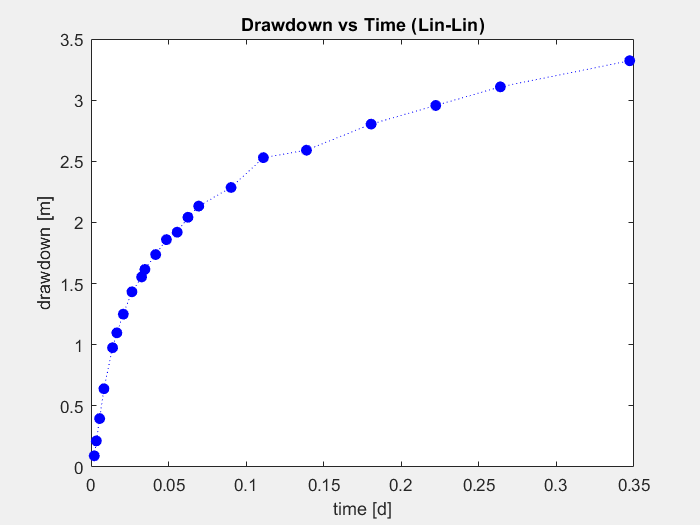

figure(1)
plot(t_exp,s_exp,':ob','MarkerFaceColor','b');
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Lin-Lin)');

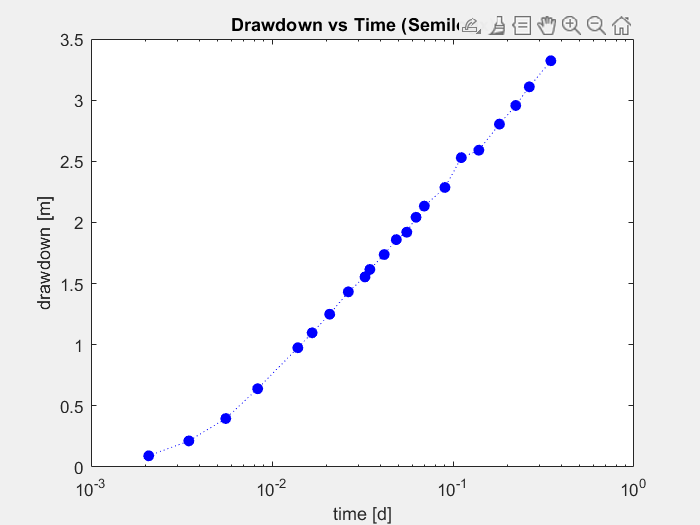

drawnow;

figure(2)
semilogx(t_exp,s_exp,':ob','MarkerFaceColor','b');
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Semilogx)');

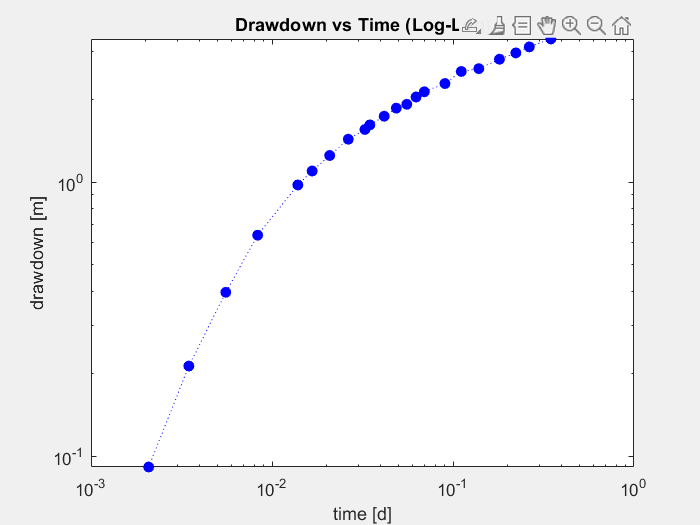

drawnow;
figure(3)
loglog(t_exp,s_exp,':ob','MarkerFaceColor','b');
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Log-Log)');

drawnow;

At a first glance it seems that our data are in great agreement with theorethical expectations from theTheis model but let's plot them together with the derivative and our theoretical reference.

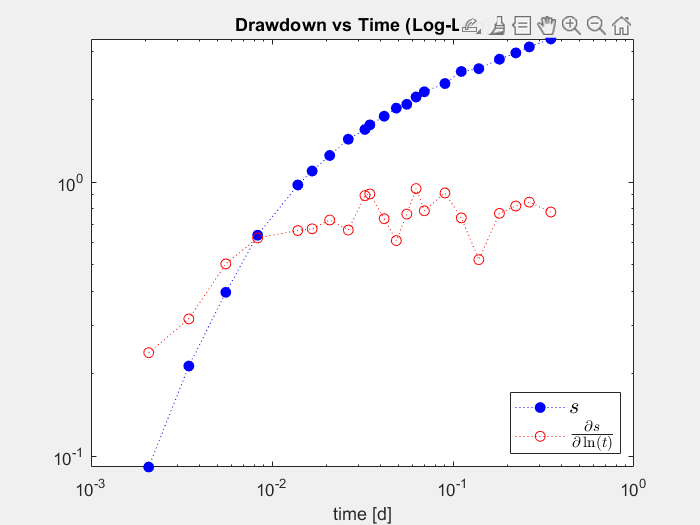

figure(4)
loglog(t_exp,s_exp,':ob','MarkerFaceColor','b');
hold on 
loglog(t_exp,num_der(t_exp,s_exp),':or')
xlabel('time [d]');
title('Drawdown vs Time (Log-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

drawnow;

Still very consistent with Theis solution, apart from some fluctuacions of the numerical derivative. Let's move onto fitting the Theis Solution. We use the Levenberg-Marquart algorithm as shown in the Automatic model fitting chapter of the book that was shared in the class materials website. We take advantage of the `theis_model.m` function. 

% Residuals function
residuals = @(p) abs(s_exp - theis_model(p, t_exp, Q_exp, r_exp));

% Initial parameters
params0 = [1000,1e-4]; % T [m^2/d], S [-]

%options for the algorithm using Levenberg-Marquardt algorithm
options = optimoptions('lsqnonlin', 'Algorithm', 'levenberg-marquardt', ...
    'Display', 'iter', 'TolFun', 1e-12, 'TolX', 1e-12);

% Optimization
best_params = lsqnonlin(residuals, params0, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3           62.859        3.03e+04         0.01
     1          17          60.7304        4.26e+04        1e+09    2.97656e-05
     2          20           55.549        9.87e+04        1e+08    4.11622e-05
     3          25          53.2578        1.44e+05        1e+10    9.65773e-06
     4          28          46.6555        4.52e+05        1e+09    1.37272e-05
     5          33          39.9342         1.6e+06        1e+11    4.25603e-06
     6          37          26.7083        4.57e+07        1e+12    1.45736e-06
     7          43          22.9268        6.71e+07        1e+15    4.00387e-08
     8          47          21.3078        9.18e+07        1e+16    6.41902e-09
     9          50          18.7162        1.76e+08        1e+15    8.31223e-09
    10          55          16.8422        1.63e+08  

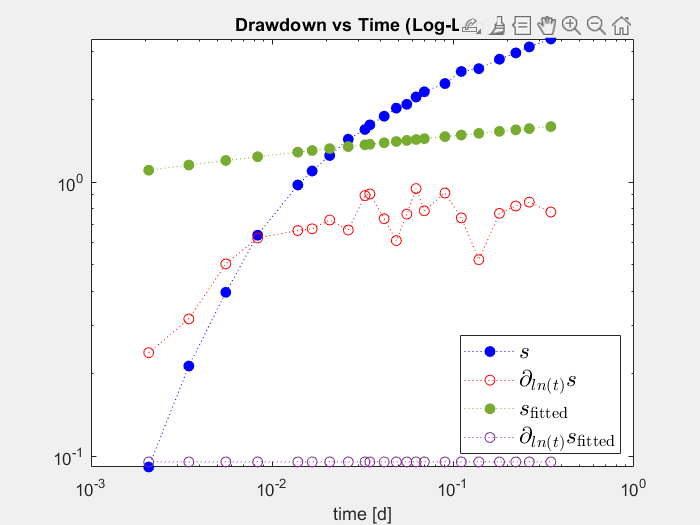

figure(5)
loglog(t_exp,s_exp,':ob','MarkerFaceColor','b');
hold on 
loglog(t_exp,num_der(t_exp,s_exp),':or')
xlabel('time [d]');
title('Drawdown vs Time (Log-Log)');
loglog(t_exp,theis_model(best_params,t_exp,Q_exp,r_exp),':o','Color',"#77AC30",'MarkerEdgeColor',"#77AC30",'MarkerFaceColor',"#77AC30");
loglog(t_exp,theis_der(best_params,t_exp,Q_exp,r_exp),':o','Color',"#7E2F8E");
legend({'$s$', '$\partial_{ln(t)}s$', '$s_{\mathrm{fitted}}$','$\partial_{ln(t)}s_{\mathrm{fitted}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

drawnow;

This result is pretty bad and is due to the fact that the algorithm is very sensitive to initial conditions. If we instead try to use the algotihm proposed in class, we obtain:

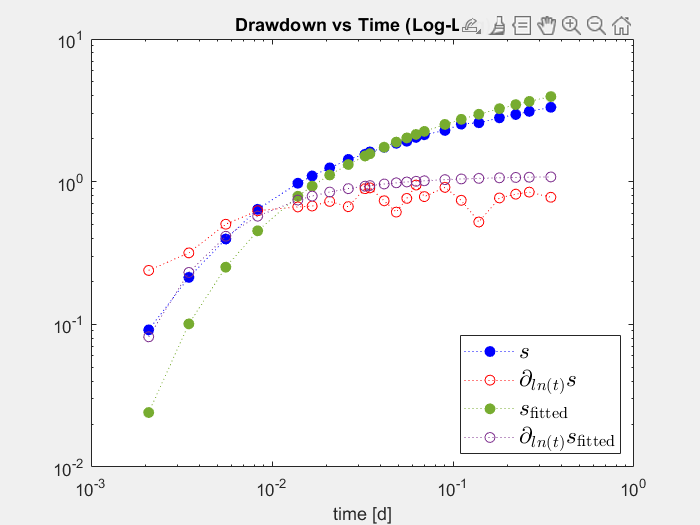

iter =5000;
NS_g = -1000;

for j = 1:1:iter

S = 1E-7 + (1E-3+1E-3)*rand;

T = randi([1,2000],1,1);

W = expint(r_exp^2.*S./(4.*T.*t_exp));

s_sim = Q_exp./4./pi()./T.*W;

NS_1 = s_sim-s_exp;

NS_2 = s_exp-mean(s_exp);

NS = 1 - sum(NS_1.^2)./sum(NS_2.^2);

if NS >= NS_g

s_final = s_sim;

Opt = [T,S];

NS_g = 1 - sum((s_final-s_exp).^2)./sum((s_exp-mean(s_exp)).^2);

end

end

figure(6)
loglog(t_exp,s_exp,':ob','MarkerFaceColor','b');
hold on 
loglog(t_exp,num_der(t_exp,s_exp),':or')
xlabel('time [d]');
title('Drawdown vs Time (Log-Log)');
loglog(t_exp,theis_model(Opt,t_exp,Q_exp,r_exp),':o','Color',"#77AC30",'MarkerEdgeColor',"#77AC30",'MarkerFaceColor',"#77AC30");
loglog(t_exp,theis_der(Opt,t_exp,Q_exp,r_exp),':o','Color',"#7E2F8E");
legend({'$s$', '$\partial_{ln(t)}s$', '$s_{\mathrm{fitted}}$','$\partial_{ln(t)}s_{\mathrm{fitted}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

drawnow;

This is better than before, but it depends on the random initialization of the parameters and on the number of iterations, if one runs the code again the output is probably going to change. A possible idea is to use the Optimum found with this method as a starting point for the Levenberg-Marquardt algorithm.

best_params_2 = lsqnonlin(residuals, Opt, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3          1.59511        9.18e+04         0.01
     1           6         0.904963        6.01e+03        0.001        3.60684
     2           9          0.23896        6.55e+03       0.0001        14.8657
     3          12        0.0265466        9.63e+03        1e-05        14.5394
     4          15        0.0169339             325        1e-06        2.97574
     5          18         0.016927            1.06        1e-07      0.0644112
     6          21         0.016927          0.0188        1e-08    0.000566689
     7          32                                                 7.85505e-11

Local minimum possible.
lsqnonlin stopped because the relative 

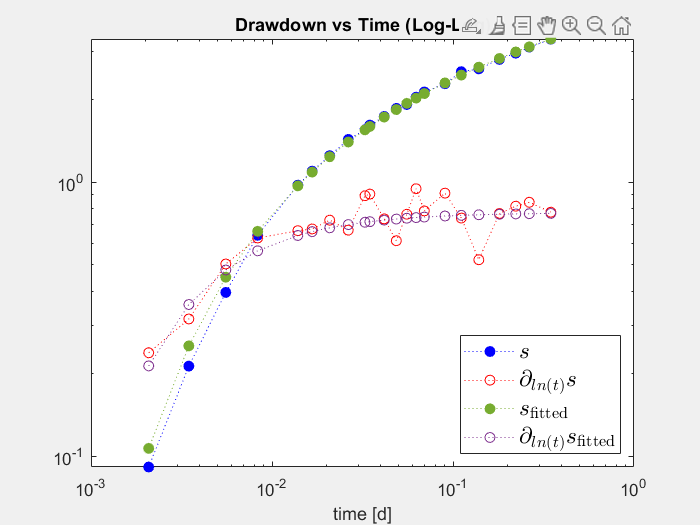

figure(7)
loglog(t_exp,s_exp,':ob','MarkerFaceColor','b');
hold on 
loglog(t_exp,num_der(t_exp,s_exp),':or')
xlabel('time [d]');
title('Drawdown vs Time (Log-Log)');
loglog(t_exp,theis_model(best_params_2,t_exp,Q_exp,r_exp),':o','Color',"#77AC30",'MarkerEdgeColor',"#77AC30",'MarkerFaceColor',"#77AC30");
loglog(t_exp,theis_der(best_params_2,t_exp,Q_exp,r_exp),':o','Color',"#7E2F8E");
legend({'$s$', '$\partial_{ln(t)}s$', '$s_{\mathrm{fitted}}$','$\partial_{ln(t)}s_{\mathrm{fitted}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

drawnow;

The thing is that now, even if the best parameters for the algorithm seen in class obscillate, they are in some sense near to the best values of the Levenberg-Marquardt algorithm. So even if the previous fit changes from one run to another, this one is stable around **T=123.0515, S=2.0949e-05. **Regarding the Cooper and Jacob approximation, we can use the Linear Least Square method presented in the paper, but we need to get rid of the early times. According to the semilogx plot at the beginning of the exercise and the fitted drawdown, I start from the 8th observation (previously started from 5th but the first three point show an u>0.1).

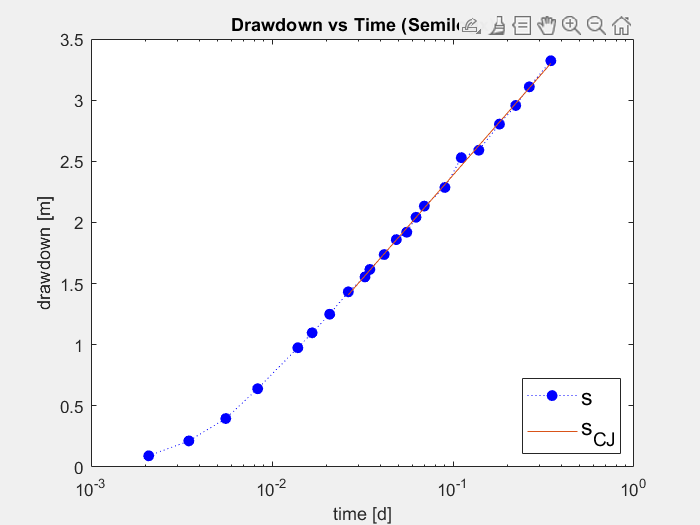

G = [log(t_exp(8:end)) ones(length(t_exp(8:end)),1)];
p = (G'*G)\(G'*s_exp(8:end));
figure(8)
semilogx(t_exp,s_exp,':ob','MarkerFaceColor','b');
hold on
semilogx(t_exp(8:end),G*p)
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Semilogx)');
legend('s','s_{CJ}', 'FontSize', 14,'Location','southeast');

drawnow;

We can see that the CJ approximation is valid in this context and nicely approximates the last part of the drawdown in the semilog plot. Now we need to calculate the values of T and S from CJ thanks to the paper formulas.

CJ_param = zeros(1,2);
CJ_param(1) = Q_exp/(4*pi*p(1));
CJ_param(2) = (2.25*CJ_param(1)*exp(-p(2)/p(1))/r_exp^2);
r_exp^2*CJ_param(2)./(4*CJ_param(1)*t_exp(8:end))<=0.1 %as suggested in the given book

ans = 15×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


diff1 = abs((best_params_2-CJ_param)./best_params_2)*100;

We obtain **T=129.9058, S=1.7988e-05. **Theis automatic fitting and CJ give similar but not identical results (T differs by ~5.5%, S by ~14%). This is expected: CJ uses only the late-time straight-line segment, while Theis considers the entire dataset. Small differences indicate a near-ideal confined aquifer; larger discrepancies would suggest well effects or boundaries. The derivative stabilizes quickly after early-time, and remains flat throughout the test (getting rid of the fluctuations). The fitted and observed curves match closely, with no late-time deviation. This indicates an ideal confined aquifer with clear radial flow and no boundary effects, probably  due to the fact that is a book example. Now we can pass to the dimensionsless analysis. Not having the well radius, I will use r_exp in the computations for the critical time and the values of S and T from the Theis Fitting.

t_c = r_exp^2*best_params_2(2)/best_params_2(1);
t_d = t_exp/t_c;
s_c = Q_exp/(2*pi*best_params_2(1));
s_d = s_exp/s_c;

Let's generate the three plots of dimensionsless drawdown vs time in linear-linear, semi-linear and log-log plots.

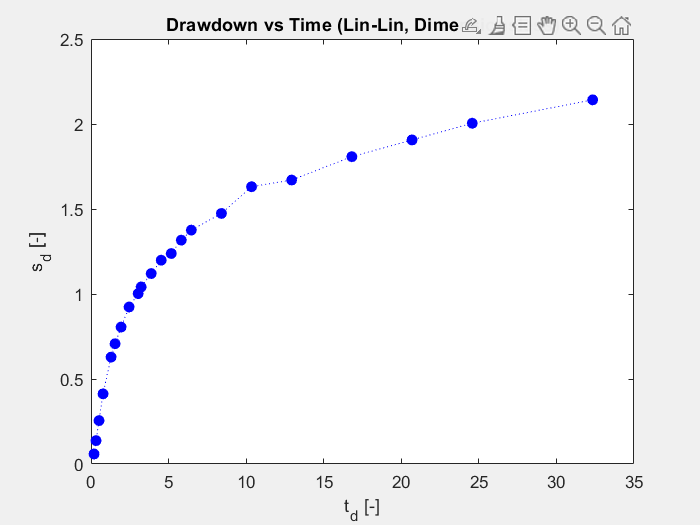

figure(9)
plot(t_d,s_d,':ob','MarkerFaceColor','b');
xlabel('t_d [-]');
ylabel('s_d [-]');
title('Drawdown vs Time (Lin-Lin, Dimensionsless)');

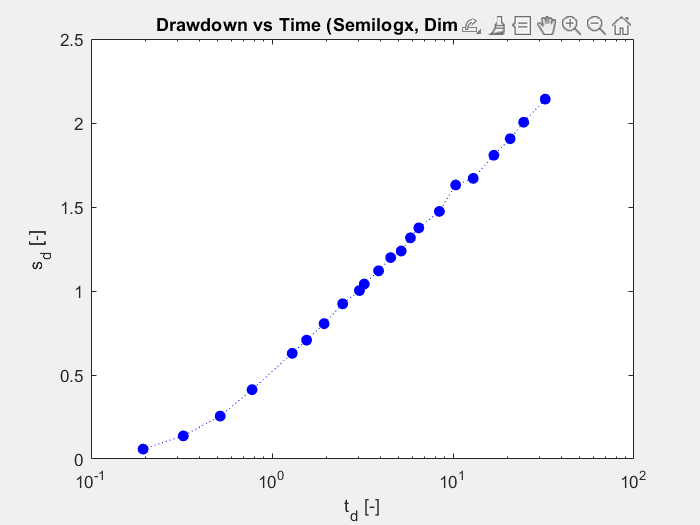

drawnow;

figure(10)
semilogx(t_d,s_d,':ob','MarkerFaceColor','b');
xlabel('t_d [-]');
ylabel('s_d [-]');
title('Drawdown vs Time (Semilogx, Dimensionsless)');

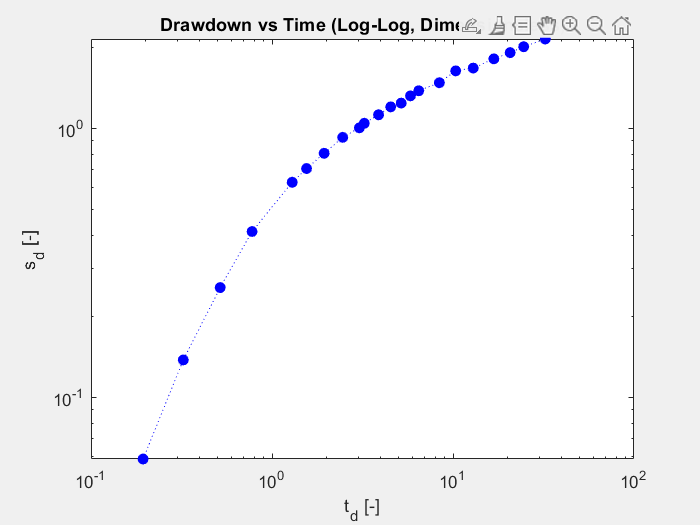

drawnow;

figure(11)
loglog(t_d,s_d,':ob','MarkerFaceColor','b');
xlabel('t_d [-]');
ylabel('s_d [-]');
title('Drawdown vs Time (Log-Log, Dimensionsless)');

drawnow;

Let's plot the derivative together with the drawdown

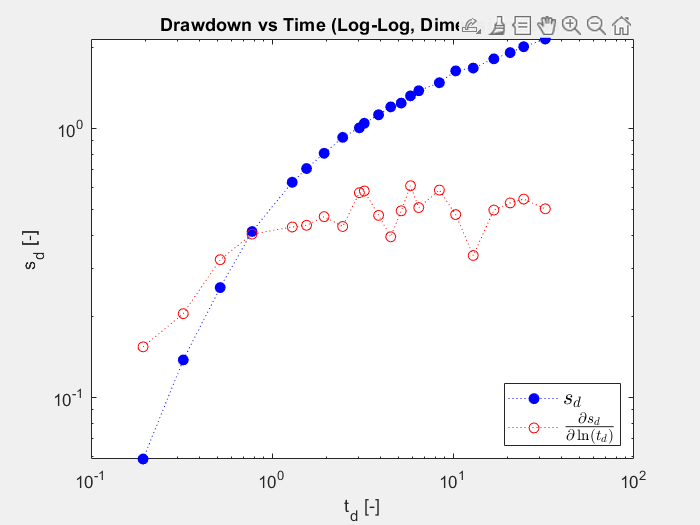

figure(12)
loglog(t_d,s_d,':ob','MarkerFaceColor','b');
hold on 
loglog(t_d,num_der(t_d,s_d),':or')
xlabel('t_d [-]');
ylabel('s_d [-]');
title('Drawdown vs Time (Log-Log, Dimensionsless)');
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

drawnow;

We now apply the Theis fitting procedure developed earlier, so first we obtain the starting point with the class algorithm adapting it to dimensionsless variables:


iter = 5000;
NS_g = -1000;

for j = 1:iter
    S = 1E-7 + (1E-3+1E-3)*rand;
    T = randi([1,2000],1,1);

    % Dimensionless variables
    t_d_exp = T .* t_exp ./ (r_exp^2 .* S);
    s_c = Q_exp / (2*pi*T);
    s_d_exp = s_exp / s_c;

    % Theis well function in dimensionless form
    u = 1 ./ (4 .* t_d_exp); %one because i use r instead of r_w so rd=1
    W = expint(u); % Well function
    s_d_sim = 1/2*W;   % Dimensionless drawdown

    % Nash–Sutcliffe efficiency
    NS_1 = s_d_sim - s_d_exp;
    NS_2 = s_d_exp - mean(s_d_exp);
    NS = 1 - sum(NS_1.^2) / sum(NS_2.^2);

    if NS >= NS_g
        s_final = s_d_sim;
        Opt_dimless = [T,S];
        NS_g = NS;
    end
end


% Residuals in dimensionless domain
residuals_dim = @(p) abs(s_exp.* (2*pi*p(1)./Q_exp) - theis_dimensionsless(p,t_exp,r_exp));
best_params_dim = lsqnonlin(residuals_dim, Opt_dimless, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3         0.399722        2.48e+04         0.01
     1           6         0.351597        1.03e+03        0.001        1.07578
     2           9         0.200031        1.05e+03       0.0001        8.10142
     3          12         0.023319        6.06e+03        1e-05        18.7774
     4          15       0.00773182             861        1e-06        5.62728
     5          18       0.00702441            49.6        1e-07        1.61366
     6          21        0.0070241          0.0413        1e-08      0.0155124
     7          24        0.0070241         0.00097        1e-09    7.98341e-05
     8          35                                                 4.41995e-11

Local minimum possible.
lsqnonlin stopped because 

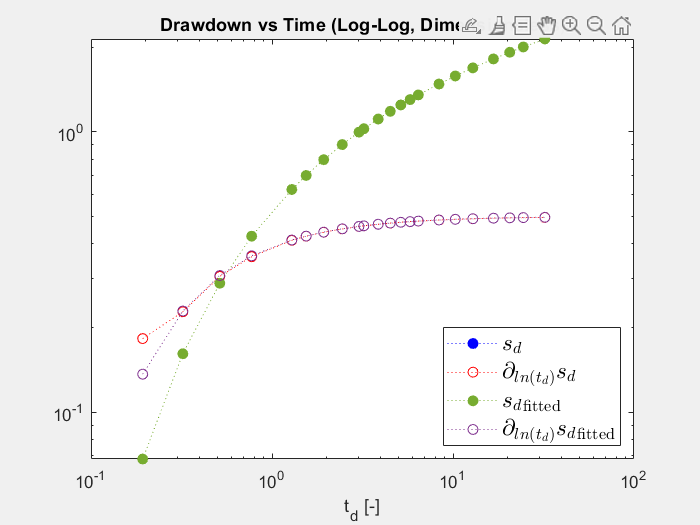

t_d = t_exp .* best_params_dim(1) ./ (r_exp^2 .* best_params_dim(2));
s_d = 1/2*expint(1./(4*t_d));

figure(13)
h1 = loglog(t_d, s_d,'LineStyle', ':', 'Marker', 'o','Color', 'b', 'MarkerFaceColor', 'b');
hold on
h2 = loglog(t_d, num_der(t_d,s_d),'LineStyle', ':', 'Marker', 'o','Color', 'r', 'MarkerEdgeColor', 'r');
h3 = loglog(t_d, theis_dimensionsless(best_params_dim,t_exp,r_exp),'LineStyle', ':', 'Marker', 'o','Color', "#77AC30", 'MarkerFaceColor', "#77AC30");
h4 = loglog(t_d, theis_der_dim(best_params_dim,t_exp,r_exp),'LineStyle', ':', 'Marker', 'o','Color', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E");
xlabel('t_d [-]');
title('Drawdown vs Time (Log-Log, Dimensionsless)');
legend([h1 h2 h3 h4],{'$s_d$', '$\partial_{ln(t_d)}s_d$', '${s_d}_{\mathrm{fitted}}$', '$\partial_{ln(t_d)}{s_d}_{\mathrm{fitted}}$'},'Interpreter', 'latex', 'FontSize', 14, 'Location', 'southeast');

drawnow;
diff2 = abs((best_params_2-best_params_dim)./best_params_2)*100;

The obtained S and T for the dimensionsless analysis are: **T=122.8199 **and** S=2.1017e-05. **Dimensionless fitting produced T and S values almost identical to those from the standard Theis fitting (<0.5% difference), confirming that normalization does not affect parameter estimation for an ideal case.

Theis fitting (dimensional and dimensionless) gives nearly identical results, confirming consistency. Cooper–Jacob estimates are close for T (~7% higher) and slightly lower for S (~16%), still near considering  its a late-time approximation. The derivative plot shows early stabilization without the 1:1 slope typical of wellbore storage and no late-time deviation, indicating an ideal confined aquifer with clear radial flow and no boundary effects, our plots for this exercise are very similar (taking into account the small fluctuations) to the confined ideal aquifer reference plots. 

## Exercise 2 - Test with two piezometers

We start by defining all the experimental data.

clearvars;
load('testP30.m');
load('testP90.m');
t_exp_30 = testP30(2:end,1); %d
t_exp_90 = testP90(2:end,1); %d
s_exp_30 = testP30(2:end,2); %m
s_exp_90 = testP90(2:end,2); %m
Q_exp = 788; %m^3/d
r_exp_30 = 30; %m
r_exp_90 = 90; %m

We now generate the three plots of drawdown vs time in linear-linear, semi-linear and log-log plots.

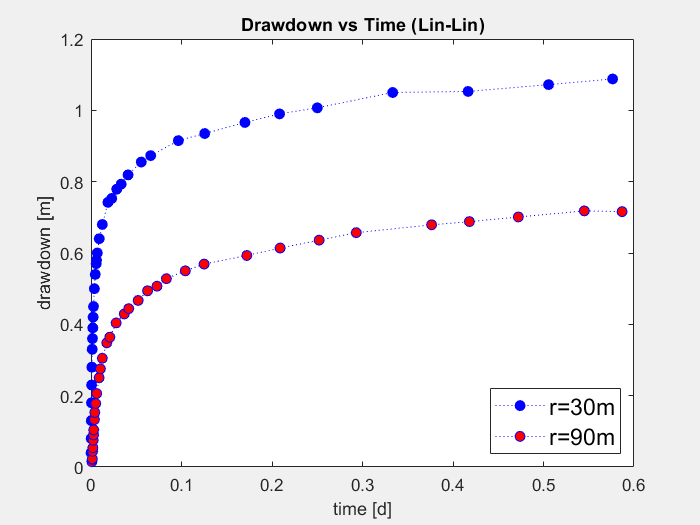

figure('Visible','on');
plot(t_exp_30,s_exp_30,':ob','MarkerFaceColor','b');
hold on
plot(t_exp_90,s_exp_90,':ob','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Lin-Lin)');
legend('r=30m','r=90m','FontSize', 14, 'Location', 'southeast');

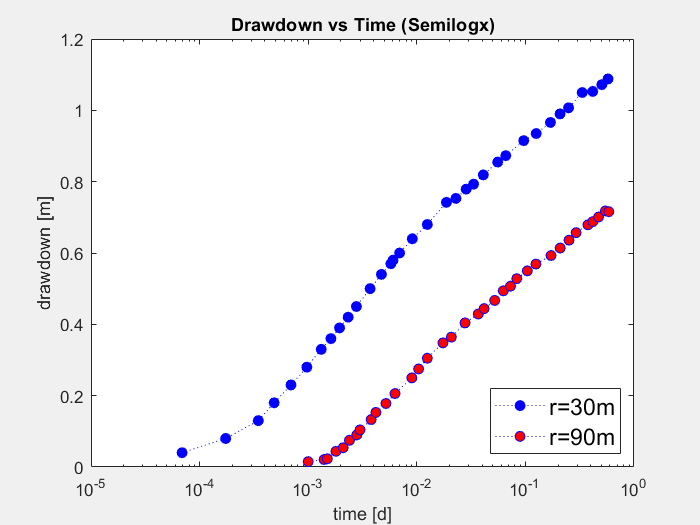

drawnow;

figure('Visible','on');
semilogx(t_exp_30,s_exp_30,':ob','MarkerFaceColor','b');
hold on
semilogx(t_exp_90,s_exp_90,':ob','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Semilogx)');
legend('r=30m','r=90m','FontSize', 14, 'Location', 'southeast');

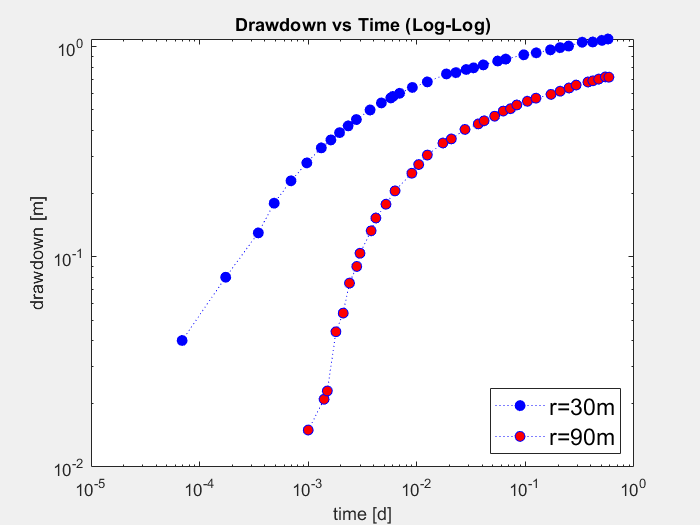

drawnow;

figure('Visible','on');
loglog(t_exp_30,s_exp_30,':ob','MarkerFaceColor','b');
hold on
loglog(t_exp_90,s_exp_90,':ob','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Log-Log)');
legend('r=30m','r=90m','FontSize', 14, 'Location', 'southeast');

drawnow;

This time, the plots doesn't seem exactly in agreement with the Theis solution for an ideal confined aquifer. We can notice kind of a 1:1 slope in the loglog plot for r=30, letting us think of a possible well-bore storage, r=90 is more in line with Theis solution at a first glance even if we can notice a strange curvature at the beginning of the log-log plot. We need to plot the derivative in log-log scale for a better analysis.

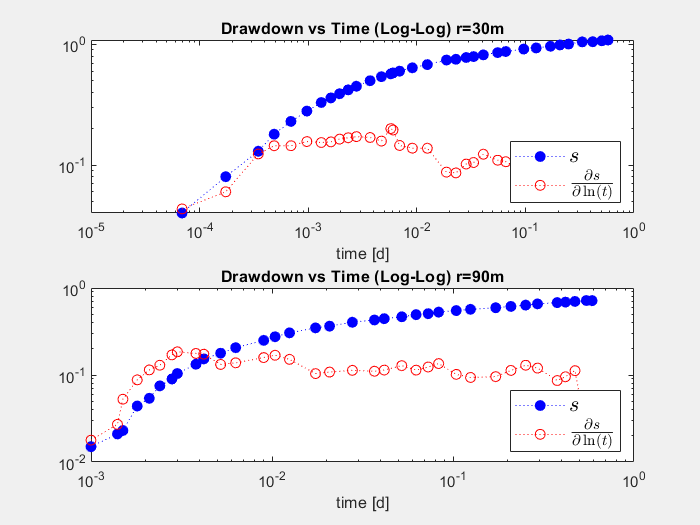

figure('Visible','on');
subplot(2,1,1)
loglog(t_exp_30,s_exp_30,':ob','MarkerFaceColor','b');
hold on 
loglog(t_exp_30,num_der(t_exp_30,s_exp_30),':or')
xlabel('time [d]');
title('Drawdown vs Time (Log-Log) r=30m');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');
subplot(2,1,2)
loglog(t_exp_90,s_exp_90,':ob','MarkerFaceColor','b');
hold on 
loglog(t_exp_90,num_der(t_exp_90,s_exp_90),':or')
xlabel('time [d]');
title('Drawdown vs Time (Log-Log) r=90m');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

drawnow;

The first plot for r=30 now seems very consistent with the diagnostic plots of a single well-test with well-bore storage and possible skin effects, the derivative is increasing adjacent to the drawdown and then decreasing and stabilizing to another value. Regarding the second plot, for r=90, coulde be considered more similar to the theorethical plots. However well bore-storage influences early times and we can see from the semilog plot that after some time $t \simeq 10^{-2} d$ the two drawdown curves start to run parallel, so this should be our data from the aquifer and before trying to fit Theis solution we must restrict our data, this is also supported by the derivative that stabilizes after that time (considering the effect of little fluctuations as in the previous exercise). 

t_exp_30_r = t_exp_30(t_exp_30 >= 1e-2);
t_exp_90_r = t_exp_90(t_exp_90 >= 1e-2);
s_exp_30_r = s_exp_30(t_exp_30 >= 1e-2);
s_exp_90_r = s_exp_90(t_exp_90 >= 1e-2);
% t_exp_30_r = t_exp_30_r(1:end-5);
% t_exp_90_r = t_exp_90_r(1:end-5);
% s_exp_30_r = s_exp_30_r(1:end-5);
% s_exp_90_r = s_exp_90_r(1:end-5);

iter =10000;
NS_g_1 = -1000;
NS_g_2 = -1000;

for j = 1:1:iter

S = 1E-7 + (1E-3+1E-3)*rand;

T = randi([1,2000],1,1);

W1 = expint(r_exp_30^2.*S./(4.*T.*t_exp_30_r));

W2 = expint(r_exp_90^2.*S./(4.*T.*t_exp_90_r));

s_sim_1 = Q_exp./4./pi()./T.*W1;
s_sim_2 = Q_exp./4./pi()./T.*W2;

NS_1_1 = s_sim_1-s_exp_30_r;
NS_1_2 = s_sim_2-s_exp_90_r;

NS_2_1 = s_exp_30_r-mean(s_exp_30_r);
NS_2_2 = s_exp_90_r-mean(s_exp_90_r);

NS_1 = 1 - sum(NS_1_1.^2)./sum(NS_2_1.^2);
NS_2 = 1 -  sum(NS_1_2.^2)./sum(NS_2_2.^2);

if NS_1 >= NS_g_1

Opt_1 = [T,S];

NS_g_1 = 1 - sum((s_sim_1-s_exp_30_r).^2)./sum((s_exp_30_r-mean(s_exp_30_r)).^2);

end

if NS_2 >= NS_g_2

Opt_2 = [T,S];

NS_g_2 = 1 - sum((s_sim_2-s_exp_90_r).^2)./sum((s_exp_90_r-mean(s_exp_90_r)).^2);

end

end

%Residuals function
residuals_30 = @(p) abs(s_exp_30_r - theis_model(p, t_exp_30_r, Q_exp, r_exp_30));
residuals_90 = @(p) abs(s_exp_90_r - theis_model(p, t_exp_90_r, Q_exp, r_exp_90));

%options for the algorithm using Levenberg-Marquardt algorithm
options = optimoptions('lsqnonlin', 'Algorithm', 'levenberg-marquardt', ...
    'Display', 'iter', 'TolFun', 1e-12, 'TolX', 1e-12);

% Optimization
best_params_30 = lsqnonlin(residuals_30, Opt_1, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3       0.00227787             770         0.01
     1           6      0.000712849            30.4        0.001    0.000163562
     2           9      0.000709933          0.0509       0.0001     0.00163362
     3          12       0.00070988        0.000338        1e-05      0.0162178
     4          15      0.000709406         0.00933        1e-06       0.151181
     5          18      0.000707316           0.433        1e-07       0.874922
     6          21      0.000706284            0.63        1e-08        1.05215
     7          24      0.000706268         0.00834        1e-09       0.139138
     8          27      0.000706268        5.28e-05        1e-10     0.00182188
     9          30      0.000706268         6.9e-08        1e-11    2.93952e-06



best_params_90 = lsqnonlin(residuals_90, Opt_2, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3       0.00170387            94.7         0.01
     1           6       0.00124816            2.27        0.001     0.00133883
     2           9       0.00124756        9.64e-05       0.0001      0.0134237
     3          12       0.00124401         0.00429        1e-05       0.132853
     4          15       0.00121347           0.163        1e-06        1.20385
     5          18       0.00110704            1.64        1e-07        5.90137
     6          21       0.00107499             1.2        1e-08        4.99571
     7          24       0.00107474          0.0071        1e-09       0.387075
     8          27       0.00107474        9.11e-06        1e-10     0.00105324
     9          37                                                 7.08681e-11



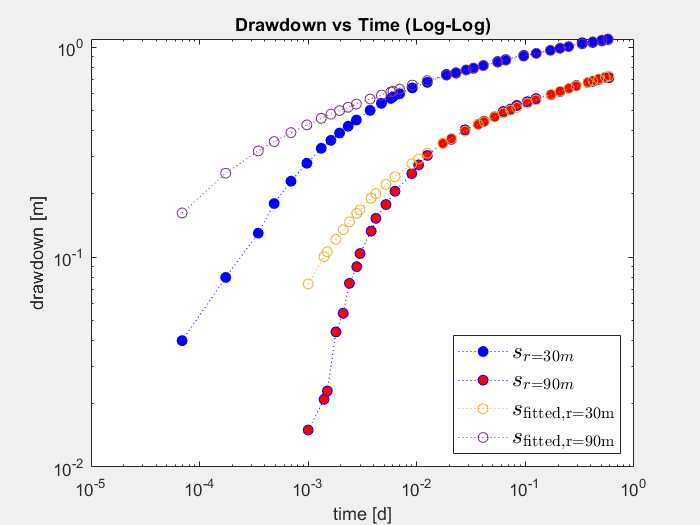

figure('Visible','on');
loglog(t_exp_30,s_exp_30,':ob','MarkerFaceColor','b');
hold on
loglog(t_exp_90,s_exp_90,':ob','MarkerFaceColor','r');
loglog(t_exp_90, theis_model(best_params_90,t_exp_90,Q_exp,r_exp_90),':o')
loglog(t_exp_30, theis_model(best_params_30,t_exp_30,Q_exp,r_exp_30),':o')
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Log-Log)');
legend('r=30m','r=90m','FontSize', 14, 'Location', 'southeast');
legend({'$s_{r=30m}$','$s_{r=90m}$', '$s_{\mathrm{fitted, r=30m}}$','$s_{\mathrm{fitted, r=90m}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

We obtain: $T_{30}\simeq 599 m^3/d, T_{90}\simeq 575 m^3/d, S_{30}\simeq 2.5\times 10^{-5}, S_{90}\simeq 1.2\times 10^{-4}. $ 

diff= abs((best_params_30-best_params_90)./best_params_90*100);

The T value is almost equal but the storativity varies significantly, it is better to refer to the subsequent dimensionless analysis. But before passing to the dimensionsless analysis we try to use Cooper and Jacob.

check=0;
t=1;
CJ_param_30 = zeros(1,2);
CJ_param_90 = zeros(1,2);

while check == 0
G_30 = [log(t_exp_30_r(t:end)) ones(length(t_exp_30_r(t:end)),1)];
p_30 = (G_30'*G_30)\(G_30'*s_exp_30_r(t:end));
CJ_param_30(1) = Q_exp/(4*pi*p_30(1));
CJ_param_30(2) = (2.25*CJ_param_30(1)*exp(-p_30(2)/p_30(1))/r_exp_30^2);
if all(r_exp_30^2*CJ_param_30(2)./(4*CJ_param_30(1)*t_exp_30_r(t:end))<=0.1)
   check=1
else t=t+1;
    
end
end

check = 1


check = 0;
t_30=t;
t=1;

while check == 0
G_90 = [log(t_exp_90_r(t:end)) ones(length(t_exp_90_r(t:end)),1)];
p_90 = (G_90'*G_90)\(G_90'*s_exp_90_r(t:end));
CJ_param_90(1) = Q_exp/(4*pi*p_90(1));
CJ_param_90(2) = (2.25*CJ_param_90(1)*exp(-p_90(2)/p_90(1))/r_exp_90^2);
if all(r_exp_90^2*CJ_param_90(2)./(4*CJ_param_90(1)*t_exp_90_r(t:end))<=0.1)
   check=1
else t=t+1;

end

end

check = 1

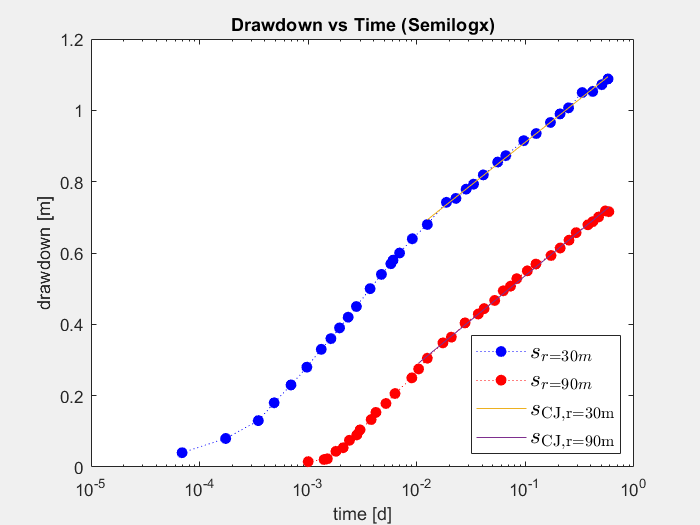

t_90=t;



figure('Visible','on');
semilogx(t_exp_30,s_exp_30,':ob','MarkerFaceColor','b');
hold on
semilogx(t_exp_90,s_exp_90,':or','MarkerFaceColor','r');
semilogx(t_exp_30_r(t_30:end),G_30*p_30)
semilogx(t_exp_90_r(t_90:end),G_90*p_90)
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Semilogx)');
legend({'$s_{r=30m}$','$s_{r=90m}$', '$s_{\mathrm{CJ, r=30m}}$','$s_{\mathrm{CJ, r=90m}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

diff_CJ_30=abs(CJ_param_30-best_params_30)./best_params_30*100;
diff_CJ_90=abs(CJ_param_90-best_params_90)./best_params_90*100;

We can see that where the CJ approximation is valid in our restricted data, the values of T and S are very similar to the Theis one. Now we can move to dimensionsless variables.

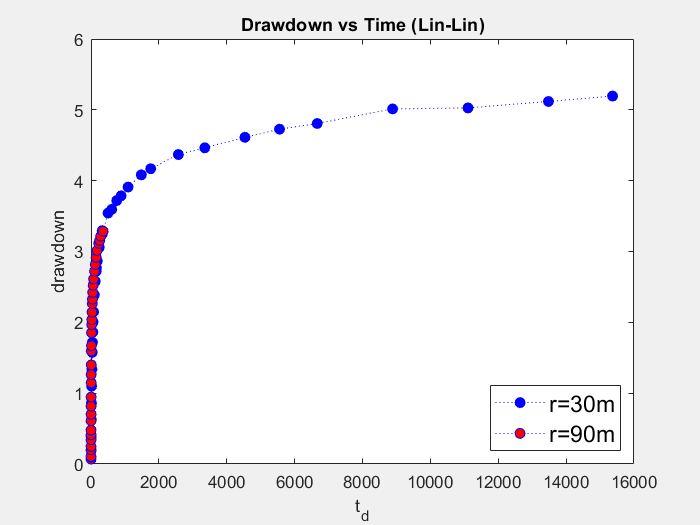

t_d_30=t_exp_30.*best_params_30(1)./(r_exp_30^2*best_params_30(2));
t_d_90=t_exp_90.*best_params_90(1)./(r_exp_90^2*best_params_90(2));
r_d_30=1;
r_d_90=1;
s_d_90=s_exp_90/(Q_exp/(2*pi*best_params_90(1)));
s_d_30=s_exp_30/(Q_exp/(2*pi*best_params_30(1)));

figure('Visible','on');
plot(t_d_30,s_d_30,':ob','MarkerFaceColor','b');
hold on
plot(t_d_90,s_d_90,':ob','MarkerFaceColor','r');
xlabel('t_d');
ylabel('drawdown');
title('Drawdown vs Time (Lin-Lin)');
legend('r=30m','r=90m','FontSize', 14, 'Location', 'southeast');

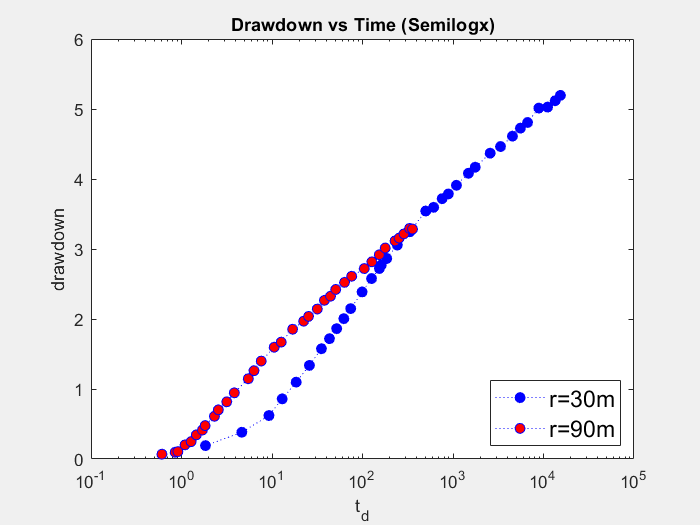

figure('Visible','on');
semilogx(t_d_30,s_d_30,':ob','MarkerFaceColor','b');
hold on
semilogx(t_d_90,s_d_90,':ob','MarkerFaceColor','r');
xlabel('t_d');
ylabel('drawdown');
title('Drawdown vs Time (Semilogx)');
legend('r=30m','r=90m','FontSize', 14, 'Location', 'southeast');

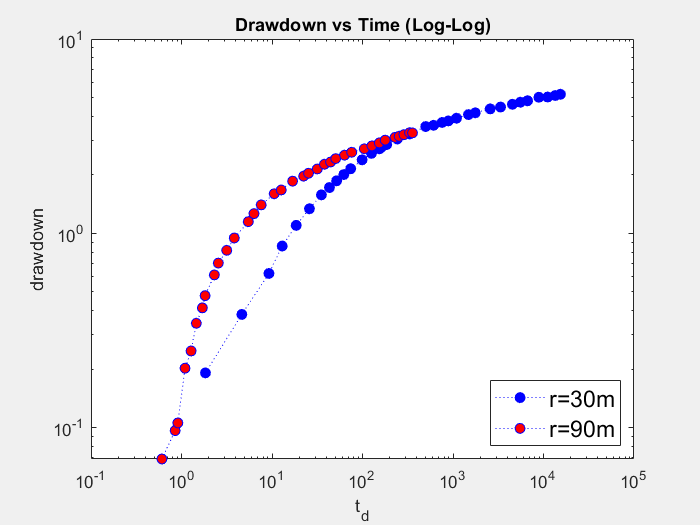

figure('Visible','on');
loglog(t_d_30,s_d_30,':ob','MarkerFaceColor','b');
hold on
loglog(t_d_90,s_d_90,':ob','MarkerFaceColor','r');
xlabel('t_d');
ylabel('drawdown');
title('Drawdown vs Time (Log-Log)');
legend('r=30m','r=90m','FontSize', 14, 'Location', 'southeast');

We also plot the derivative in log-log.

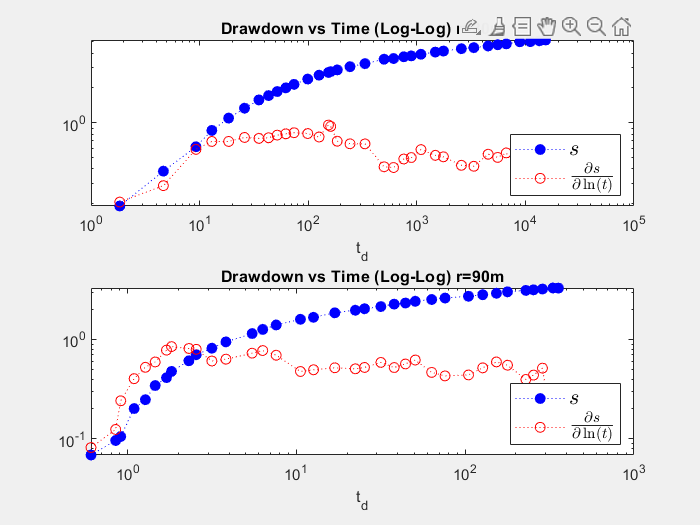

figure('Visible','on');
subplot(2,1,1)
loglog(t_d_30,s_d_30,':ob','MarkerFaceColor','b');
hold on 
loglog(t_d_30,num_der(t_d_30,s_d_30),':or')
xlabel('t_d');
title('Drawdown vs Time (Log-Log) r=30m');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');
subplot(2,1,2)
loglog(t_d_90,s_d_90,':ob','MarkerFaceColor','b');
hold on 
loglog(t_d_90,num_der(t_d_90,s_d_90),':or')
xlabel('t_d');
title('Drawdown vs Time (Log-Log) r=90m');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

From the plot it seems that the two datasets reach the same Theis solution, maybe some of the points of the r=30m data are deviating for well bore storage since it seems from the loglog plot thath we have something likea a 1:1 slope at the beginning and the derivative goes together with the s curve, before stabilizing. Let's try to fit a single theis and CJ solution that is much easier in dimensionsless form. Since the well bore storage effects early times and in space we can see it mostly near the well we create a new dataset trying to fit in a single Theis the late data.

t = [t_exp_30(19:end); t_exp_90(16:end)];
s = [s_exp_30(19:end); s_exp_90(16:end)];
r = [30*ones(length(t_d_30(19:end)),1);90*ones(length(t_d_90(16:end)),1)];

[t, idx] = sort(t);
s = s(idx);
r = r(idx);

iter = 10000;
NS_g = -1000;

for j = 1:iter
    S = 1E-7 + (1E-3+1E-3)*rand;
    T = randi([1,2000],1,1);

    % Dimensionless variables
    t_d_exp = T .* t ./ (r.^2 .* S);
    s_c = Q_exp / (2*pi*T);
    s_d_exp = s / s_c;

    % Theis well function in dimensionless form
    u = 1 ./ (4 .* t_d_exp); %one because i use r instead of r_w so rd=1
    W = expint(u); % Well function
    s_d_sim = 1/2*W;   % Dimensionless drawdown

    % Nash–Sutcliffe efficiency
    NS_1 = s_d_sim - s_d_exp;
    NS_2 = s_d_exp - mean(s_d_exp);
    NS = 1 - sum(NS_1.^2) / sum(NS_2.^2);

    if NS >= NS_g
        s_final = s_d_sim;
        Opt_dimless = [T,S];
        NS_g = NS;
    end
end


% Residuals in dimensionless domain
residuals_dim = @(p) abs(s.* (2*pi*p(1)./Q_exp) - theis_dimensionsless(p,t,r));
best_params_dim = lsqnonlin(residuals_dim, Opt_dimless, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3          1.29272             495         0.01
     1           6          1.28975            1.67        0.001       0.296737
     2           9          1.27445            12.9       0.0001        2.70003
     3          12          1.21961             268        1e-05        13.5868
     4          15          1.20023             235        1e-06        12.7377
     5          18          1.19953            8.32        1e-07         1.5418
     6          21          1.19953          0.0509        1e-08      0.0551148
     7          24          1.19953        0.000856        1e-09     0.00145089
     8          35                                                 2.85811e-10

Local minimum possible.
lsqnonlin stopped because 

t_d = t .* best_params_dim(1) ./ (r.^2 .* best_params_dim(2));

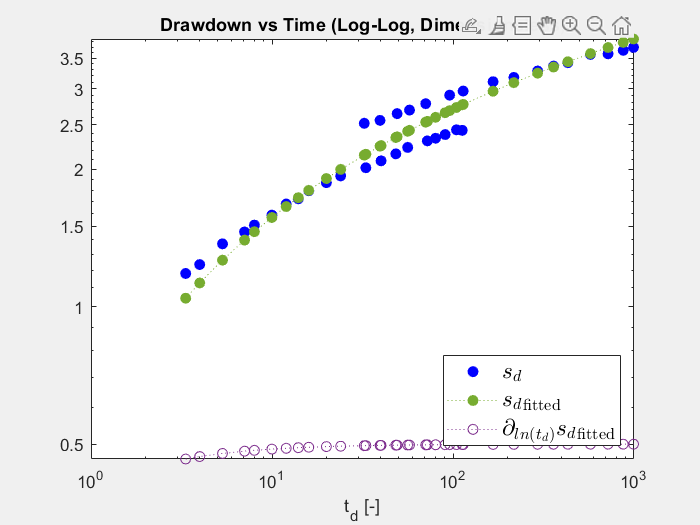

s_d = 1/2*expint(1./(4*t_d));


[t_d, idx] = sort(t_d);
s_d = s_d(idx);


figure('Visible','on');
h1 = loglog(t_d, s(idx)*(2*pi*best_params_dim(1))/Q_exp,'LineStyle', 'none', 'Marker', 'o','Color', 'b', 'MarkerFaceColor', 'b');
hold on
h3 = loglog(t_d, theis_dimensionsless(best_params_dim,t(idx),r(idx)),'LineStyle', ':', 'Marker', 'o','Color', "#77AC30", 'MarkerFaceColor', "#77AC30");
h4 = loglog(t_d, theis_der_dim(best_params_dim,t(idx),r(idx)),'LineStyle', ':', 'Marker', 'o','Color', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E");
xlabel('t_d [-]');
title('Drawdown vs Time (Log-Log, Dimensionsless)');
legend([h1 h3 h4],{'$s_d$', '${s_d}_{\mathrm{fitted}}$', '$\partial_{ln(t_d)}{s_d}_{\mathrm{fitted}}$'},'Interpreter', 'latex', 'FontSize', 14, 'Location', 'southeast');

The Transmissivity value decreases a lot but is probrably more realistic since we are better intrepolating the two curves together trying to take the most points of bot at late times. The last points of the data are a little bit under the Theis Curve, suggesting possible leakage. 

The analysis clearly shows that T remains relatively constant across both piezometers and methods, with values ranging between approximately 575 and 599 m²/d for the dimensional Theis and Cooper–Jacob approaches. This consistency strongly suggests that the aquifer is homogeneous and reaches the steady state. In contrast S exhibits significant variation. For the piezometer at 30 m, S is on the order of 10⁻⁵, while for the piezometer at 90 m it is roughly five times higher. These discrepancies are primarily due to early-time effects such as **well-bore storage** and possible skin effects, which distort the near-well data and make S less stable. The diagnostic plots confirm this interpretation: the log-log derivative for r = 30 m initially rises aligned with the drawdown and then stabilizes, whereas the curve for r = 90 m aligns more quickly with the theoretical Theis solution, indicating that the data from the more distant piezometer are less affected by local well conditions. When moving to the dimensionless analysis, which combines late-time data from both piezometers, the estimated transmissivity decreases to about 426 m²/d. This lower value is likely more realistic because it reflects the overall behavior rather than local disturbances. However, storativity in this case increases to approximately 2.74×10⁻⁴, suggesting that the model compensates for deviations between the two datasets. Furthermore, the last points of the dimensionless curve fall slightly below the Theis solution, hinting at possible leakage or the presence of boundaries that were not accounted for in the ideal confined aquifer assumption. In conclusion, T remains quite stable and confirms aquifer homogeneity, while S varies significantly, probably due to well-bore storage. The differences in the shape of the diagnostic curves reinforce this interpretation: the piezometer closer to the well (30 m) is strongly influenced by well-bore storage, whereas the one at 90 m provides data that better represent the aquifer’s true response. The dimensionless approach, although helpful in reducing discrepancies, also reveals that the system may not be perfectly ideal, with indications of leakage or boundary effects at late times.

## Exercise 3 - Pumping tests at UNAL

First, we are interested in addressing the pumping test, so we should select the correct data. For the pumping well i select Nivel agua from the Data sheet, from row 8977 where the pumping test begins to row 11917, corresponding to 49 hours after the beginning.

clearvars
filename_1 = 'UNAL/DatosPruebasBombeoPozo227IVD103.xlsx';
sheet_1 = 'Data';


startRow_1 = 8977-9;  %-9 beacuse matlab doesn't read the first 9 lines
endRow_1 = 11917-9;   

data_1 = readtable(filename_1, 'Sheet', sheet_1,  'VariableNamingRule', 'modify');

s_pw = data_1.NivelAgua(startRow_1:endRow_1);
s_static_pw = s_pw(1);
s_pw = s_pw - s_static_pw; % m
t_pw = data_1.TiempoPrueba48H(startRow_1:endRow_1); % min
t_pw = t_pw / (24*60); %d

For the observation well, we do the same thing with the Profundidad nivel piezometrico transductor coregido.

filename_2 ='UNAL/PruebaBombeoObservacion.xlsx';
sheet_2 = 'Depurado';

startRow_2 = 2973;
endRow_2 = 3561;

data_2 = readtable(filename_2, 'Sheet', sheet_2,  'VariableNamingRule', 'modify');


s_ow = data_2.ProfundidadNivelPiezometricoTransductorCorregido(startRow_2:endRow_2);
s_static_ow = s_ow(1);
s_ow = s_ow - s_static_ow; % m
t_ow = data_2.TiempoPrueba48H(startRow_2:endRow_2); % min
t_ow = t_ow / (24*60); %d

No we can proceed with the usal dimensional plots:

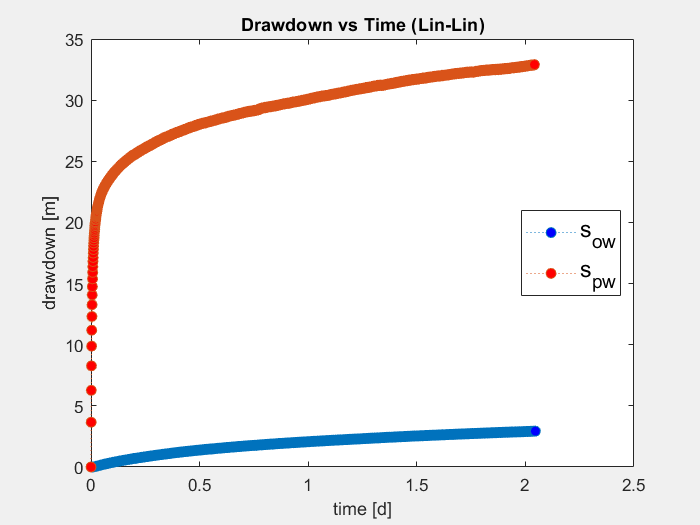

figure('Visible','on');
plot(t_ow,s_ow,':o','MarkerFaceColor','b');
hold on
plot(t_pw,s_pw,':o','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Lin-Lin)');
legend('s_{ow}','s_{pw}','FontSize', 14, 'Location', 'east');

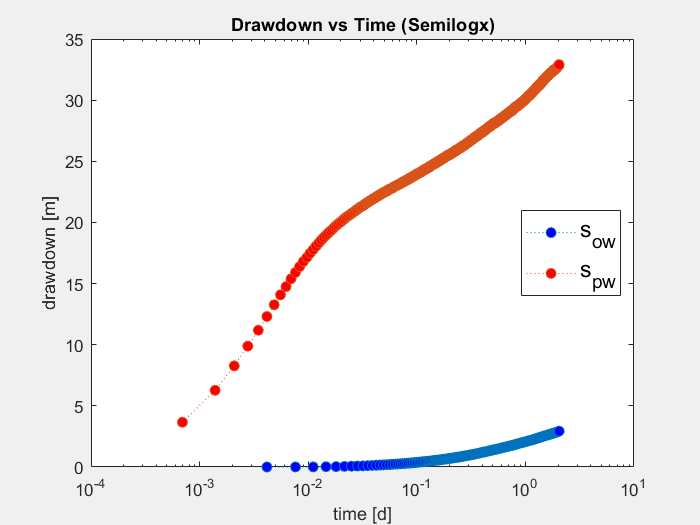

drawnow;

figure('Visible','on');
semilogx(t_ow,s_ow,':o','MarkerFaceColor','b');
hold on
semilogx(t_pw,s_pw,':o','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Semilogx)');
legend('s_{ow}','s_{pw}','FontSize', 14, 'Location', 'east');

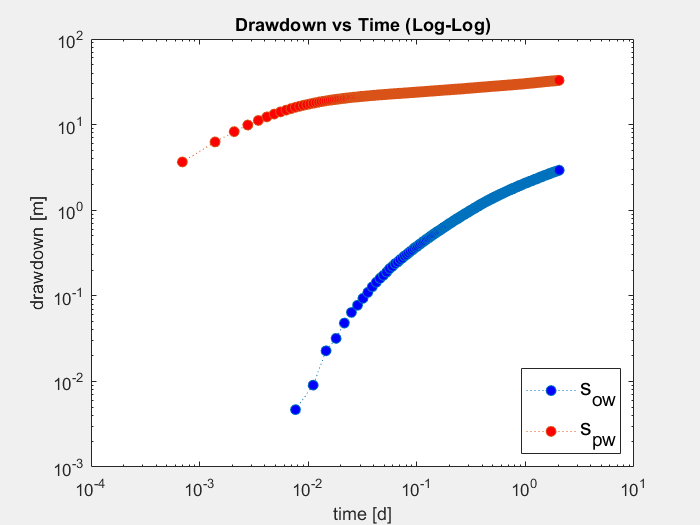

drawnow;

figure('Visible','on');
loglog(t_ow,s_ow,':o','MarkerFaceColor','b');
hold on
loglog(t_pw,s_pw,':o','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Log-Log)');
legend('s_{ow}','s_{pw}','FontSize', 14, 'Location', 'southeast');

drawnow;

The observation well is more similar to theorethical solution but in the pumping well obviously we have more complex curve so we should use the diagnostic plots.

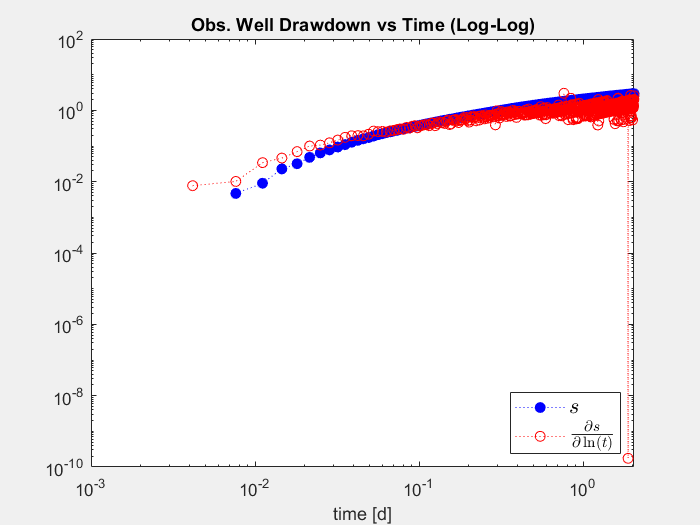

figure('Visible','on');
loglog(t_ow,s_ow,':ob','MarkerFaceColor','b');
hold on 
loglog(t_ow,num_der(t_ow,s_ow),':or')
xlabel('time [d]');
title('Obs. Well Drawdown vs Time (Log-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

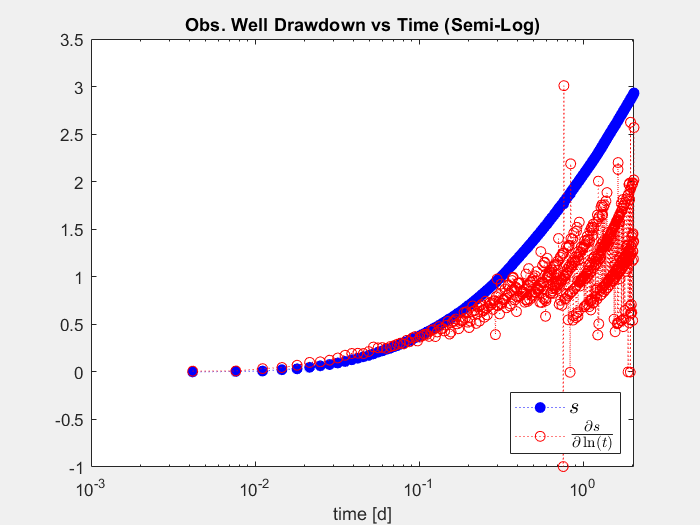


figure('Visible','on');
semilogx(t_ow,s_ow,':ob','MarkerFaceColor','b');
hold on 
semilogx(t_ow,num_der(t_ow,s_ow),':or')
xlabel('time [d]');
title('Obs. Well Drawdown vs Time (Semi-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

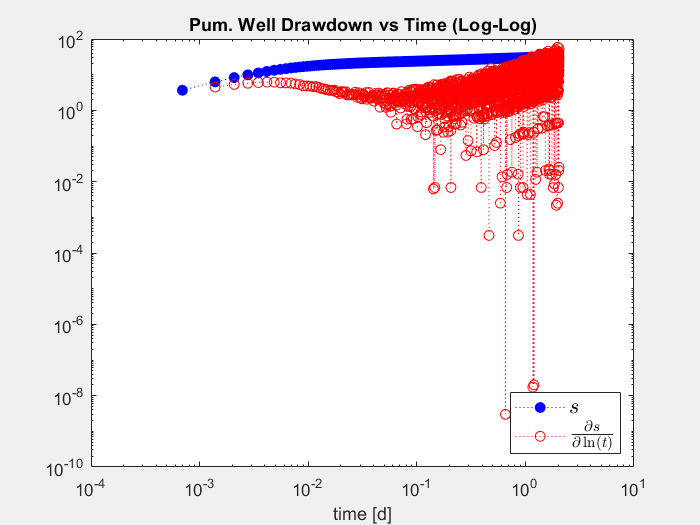

figure('Visible','on');
loglog(t_pw,s_pw,':ob','MarkerFaceColor','b');
hold on 
loglog(t_pw,num_der(t_pw,s_pw),':or')
xlabel('time [d]');
title('Pum. Well Drawdown vs Time (Log-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

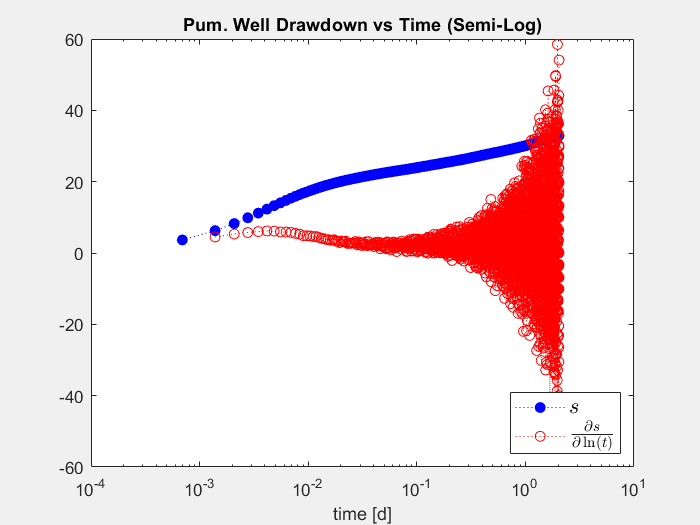

figure('Visible','on');
semilogx(t_pw,s_pw,':ob','MarkerFaceColor','b');
hold on 
semilogx(t_pw,num_der(t_pw,s_pw),':or')
xlabel('time [d]');
title('Pum. Well Drawdown vs Time (Semi-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

The Puming well plot shows drawdown increasing during pumping, with early data affected by wellbore storage and late data becoming noisy, likely due to boundaries or measurement issues. The middle portion appears more stable and closer to a straight line on the semilog scale. The observation well response appears broadly consistent with a standard Theis behavior, although the system does not seem fully stabilized, likely due to limited pumping duration. The curve shows residual curvature and minor oscillations, suggesting that including the final data points could improve interpretation. Regardin the Pumping well, features resembling unconfined conditions or double-porosity effects cannot be ruled out, but further testing and longer pumping would be needed to confirm. Maybe the dimensionsless analysis can be mor helpful but let's try at first to fit CJ.

check=0;
t=1;
CJ_param_ow = zeros(1,2);
CJ_param_pw = zeros(1,2);
Q = 2.2; % L/s
Q = Q *  60 * 60 * 24 / 1000; %m^3/d
r_ow = 9.4; %m
r_pw = 3; %''
r_pw = r_pw/39.37; %m 

while check == 0
G_ow = [log(t_ow(t:end)) ones(length(t_ow(t:end)),1)];
p_ow = (G_ow'*G_ow)\(G_ow'*s_ow(t:end));
CJ_param_ow(1) = Q/(4*pi*p_ow(1));
CJ_param_ow(2) = (2.25*CJ_param_ow(1)*exp(-p_ow(2)/p_ow(1))/r_ow^2);
if all(r_ow^2*CJ_param_ow(2)./(4*CJ_param_ow(1)*t_ow(t:end))<=0.1)
   check=1;
else t=t+1;
    
end
end
t_ow_start=t;

check=0;
t=1;

while check == 0
G_pw = [log(t_pw(t:end)) ones(length(t_pw(t:end)),1)];
p_pw = (G_pw'*G_pw)\(G_pw'*s_pw(t:end));
CJ_param_pw(1) = Q/(4*pi*p_pw(1));
CJ_param_pw(2) = (2.25*CJ_param_pw(1)*exp(-p_pw(2)/p_pw(1))/r_pw^2);
if all(r_pw^2*CJ_param_pw(2)./(4*CJ_param_pw(1)*t_pw(t:end))<=0.1)
   check=1;
else t=t+1;
    
end
end

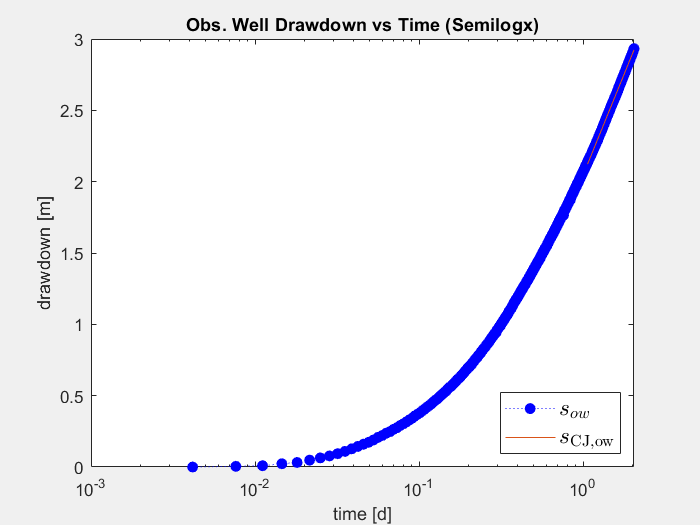


t_pw_start=t;
figure('Visible','on');
semilogx(t_ow,s_ow,':ob','MarkerFaceColor','b');
hold on
semilogx(t_ow(t_ow_start:end),G_ow*p_ow)
xlabel('time [d]');
ylabel('drawdown [m]');
title('Obs. Well Drawdown vs Time (Semilogx)');
legend({'$s_{ow}$','$s_{\mathrm{CJ, ow}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

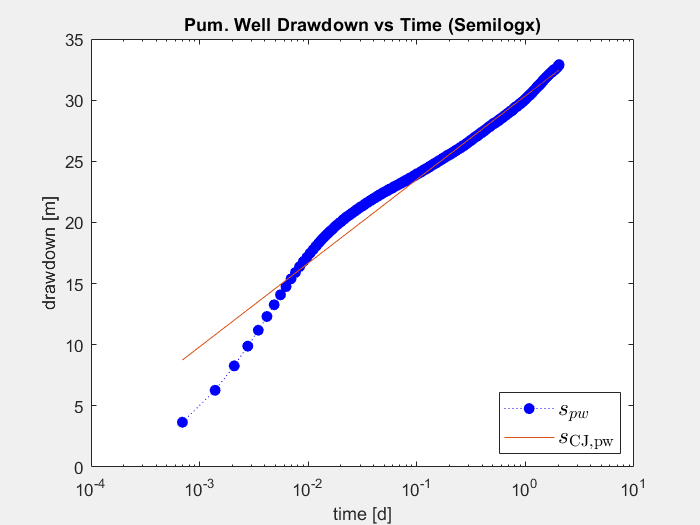

figure('Visible','on');
semilogx(t_pw,s_pw,':ob','MarkerFaceColor','b');
hold on
semilogx(t_pw(t_pw_start:end),G_pw*p_pw)
xlabel('time [d]');
ylabel('drawdown [m]');
title('Pum. Well Drawdown vs Time (Semilogx)');
legend({'$s_{pw}$','$s_{\mathrm{CJ, pw}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

We obtaint $T=12.3167 m^3/d, S=0.0594[-]$ for the observation well, while in principle we cannot use it for the pumping well since the radius is 0 or even if we use the well radius this lead to small values of u, overcoming the check but not for the correct reason. Indeed we obtain lower transmissivity ($T= 5.0932
m^3/d$) and higher storativity ($S = 0.0721[-]$) compared to the observation well. This difference is expected because pumping well data are affected by well losses and early-time storage effects, which increase drawdown and make T appear smaller while inflating S.  Let's use the automatic fitting.

t_ow_r = t_ow(t_ow >= 10^-0.8); %we begin from where the derivative is more stable in log-log plot
s_ow_r = s_ow(t_ow >= 10^-0.8);

t_pw_r = t_pw(t_pw >= 10^-1.5); 
s_pw_r = s_pw(t_pw >= 10^-1.5);

iter =10000;
NS_g = -1000;


for j = 1:1:iter

S = 1E-7 + (1E-3+1E-3)*rand;

T = randi([1,2000],1,1);

W = expint(r_ow^2.*S./(4.*T.*t_ow_r));

s_sim = Q./4./pi()./T.*W;

NS_1 = s_sim-s_ow_r;

NS_2 = s_ow_r-mean(s_ow_r);


NS = 1 - sum(NS_1.^2)./sum(NS_2.^2);

if NS >= NS_g

Opt_ow = [T,S];

NS_g = 1 - sum((s_sim-s_ow_r).^2)./sum((s_ow_r-mean(s_ow_r)).^2);

end

end

iter =10000;
NS_g = -1000;


for j = 1:1:iter

S = 1E-7 + (1E-3+1E-3)*rand;

T = randi([1,2000],1,1);

W = expint(r_pw^2.*S./(4.*T.*t_pw_r));

s_sim = Q./4./pi()./T.*W;

NS_1 = s_sim-s_pw_r;

NS_2 = s_pw_r-mean(s_pw_r);


NS = 1 - sum(NS_1.^2)./sum(NS_2.^2);

if NS >= NS_g

Opt_pw = [T,S];

NS_g = 1 - sum((s_sim-s_pw_r).^2)./sum((s_pw_r-mean(s_pw_r)).^2);

end

end

%Residuals function
residuals_ow = @(p) abs(s_ow_r - theis_model(p, t_ow_r, Q, r_ow));
residuals_pw = @(p) abs(s_pw_r - theis_model(p, t_pw_r, Q, r_pw));

%options for the algorithm using Levenberg-Marquardt algorithm
options = optimoptions('lsqnonlin', 'Algorithm', 'levenberg-marquardt', ...
    'Display', 'iter', 'TolFun', 1e-12, 'TolX', 1e-12);

% Optimization
best_params_ow = lsqnonlin(residuals_ow, Opt_ow, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3          100.315        3.78e+03         0.01
     1           7          89.5267        8.22e+03          0.1        9.32121
     2          11          73.9163        1.41e+03            1        1.37051
     3          14          68.9321             288          0.1         1.4182
     4          17            60.06        4.83e+03         0.01        11.3209
     5          21          40.8053        3.48e+03          0.1        8.10854
     6          24          1.76114             464         0.01        1.34418
     7          27         0.446708            17.9        0.001       0.372062
     8          30         0.444305          0.0877       0.0001       0.023054
     9          33         0.444304         0.00133        1e-05    0.000823581
    10          36         0.444304        3.14e-05  

best_params_pw = lsqnonlin(residuals_pw, Opt_pw, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3          4153.88        7.08e+06         0.01
     1          11          2321.55        1.57e+06         1000       0.478878
     2          15          2128.66        2.19e+05        10000      0.0529844
     3          18          2068.38        6.59e+04         1000      0.0529187
     4          22          2011.57        4.92e+04        10000      0.0528344
     5          25          1955.09        4.42e+04         1000      0.0527303
     6          29          1898.88        4.04e+04        10000      0.0526056
     7          32          1842.96         3.7e+04         1000      0.0524592
     8          36          1787.39        3.39e+04        10000      0.0522903
     9          39          1732.21         3.1e+04         1000      0.0520978
    10          43          1677.48        2.84e+04  

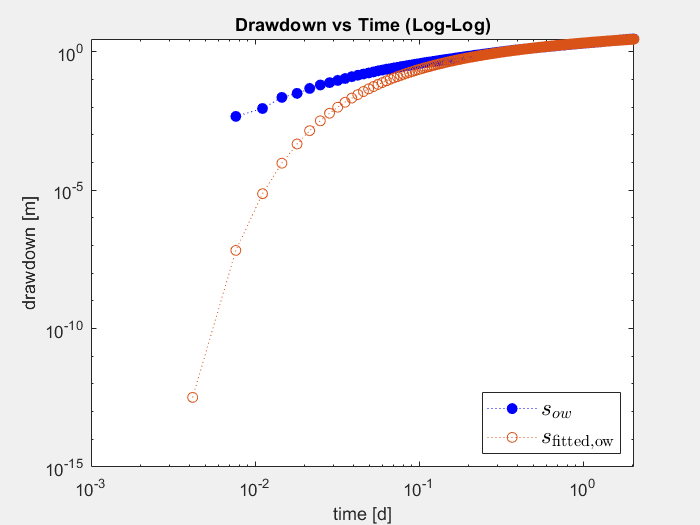


figure('Visible','on');
loglog(t_ow,s_ow,':ob','MarkerFaceColor','b');
hold on
loglog(t_ow, theis_model(best_params_ow,t_ow,Q,r_ow),':o')
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Log-Log)');
legend({'$s_{ow}$', '$s_{\mathrm{fitted, ow}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

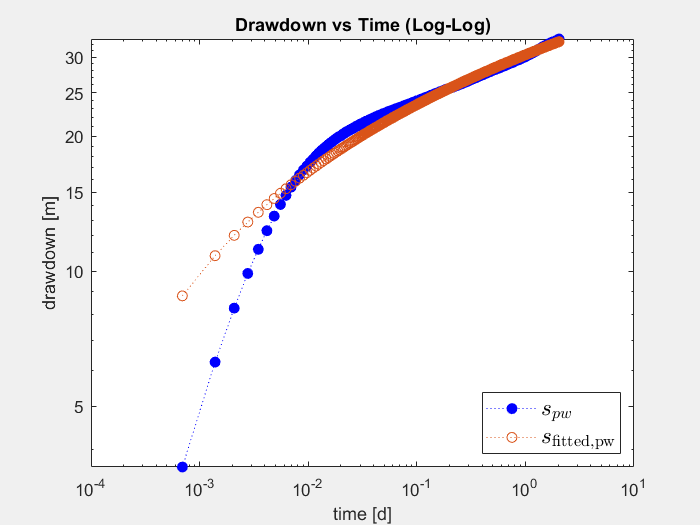

figure('Visible','on');
loglog(t_pw,s_pw,':ob','MarkerFaceColor','b');
hold on
loglog(t_pw, theis_model(best_params_pw,t_pw,Q,r_pw),':o')
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Log-Log)');
legend({'$s_{pw}$', '$s_{\mathrm{fitted, pw}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

diff_ow=abs(CJ_param_ow-best_params_ow)./best_params_ow*100;
diff_pw=abs(CJ_param_pw-best_params_pw)./best_params_pw*100;

We obtaint $T=12.7206 m^3/d, S=0.0615[-]$ for the observation well and $T=5.0880m^3/d, S=0.0727[-]$  for the pumping well, that is consistent with the CJ values. Now we move to dimensionsless analysis.

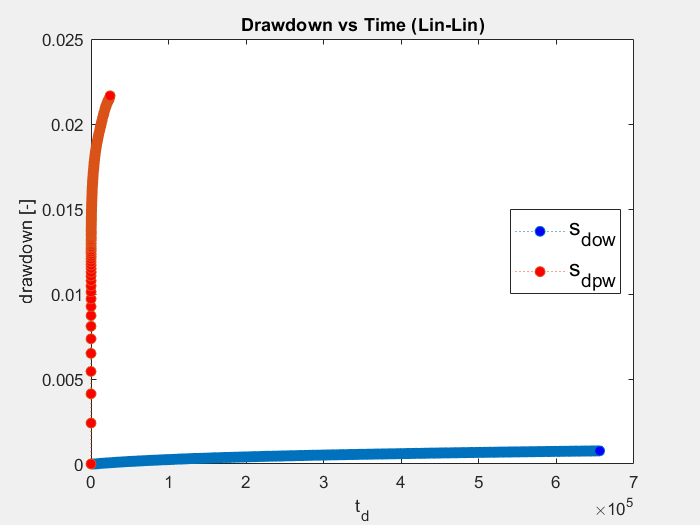

s_c_ow=Q/2*pi*best_params_ow(1);
r_c_ow=1/39.37;
t_c_ow=r_c_ow^2*best_params_ow(2)/best_params_ow(1);
s_c_pw=Q/2*pi*best_params_pw(1);
r_c_pw=3/39.37;
t_c_pw=r_c_pw^2*best_params_pw(2)/best_params_pw(1);
s_d_ow=s_ow/s_c_ow;
r_d_ow=r_ow/r_c_ow;
t_d_ow=t_ow/t_c_ow;
s_d_pw=s_pw/s_c_pw;
r_d_pw=r_pw/r_c_pw;
t_d_pw=t_pw/t_c_pw;

figure('Visible','on');
plot(t_d_ow,s_d_ow,':o','MarkerFaceColor','b');
hold on
plot(t_d_pw,s_d_pw,':o','MarkerFaceColor','r');
xlabel('t_d');
ylabel('drawdown [-]');
title('Drawdown vs Time (Lin-Lin)');
legend('s_d_{ow}','s_d_{pw}','FontSize', 14, 'Location', 'east');

drawnow;

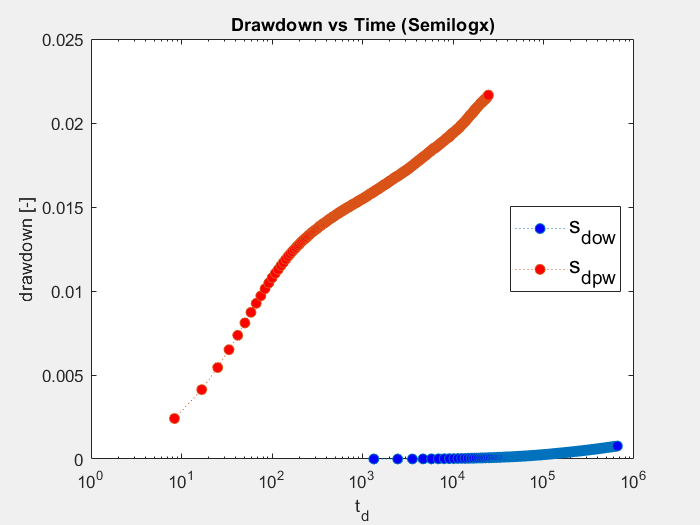


figure('Visible','on');
semilogx(t_d_ow,s_d_ow,':o','MarkerFaceColor','b');
hold on
semilogx(t_d_pw,s_d_pw,':o','MarkerFaceColor','r');
xlabel('t_d');
ylabel('drawdown [-]');
title('Drawdown vs Time (Semilogx)');
legend('s_d_{ow}','s_d_{pw}','FontSize', 14, 'Location', 'east');

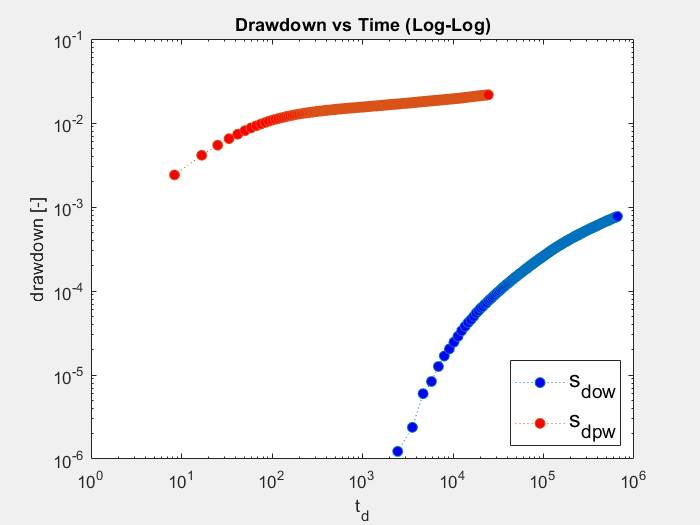

drawnow;

figure('Visible','on');
loglog(t_d_ow,s_d_ow,':o','MarkerFaceColor','b');
hold on
loglog(t_d_pw,s_d_pw,':o','MarkerFaceColor','r');
xlabel('t_d');
ylabel('drawdown [-]');
title('Drawdown vs Time (Log-Log)');
legend('s_d_{ow}','s_d_{pw}','FontSize', 14, 'Location', 'southeast');

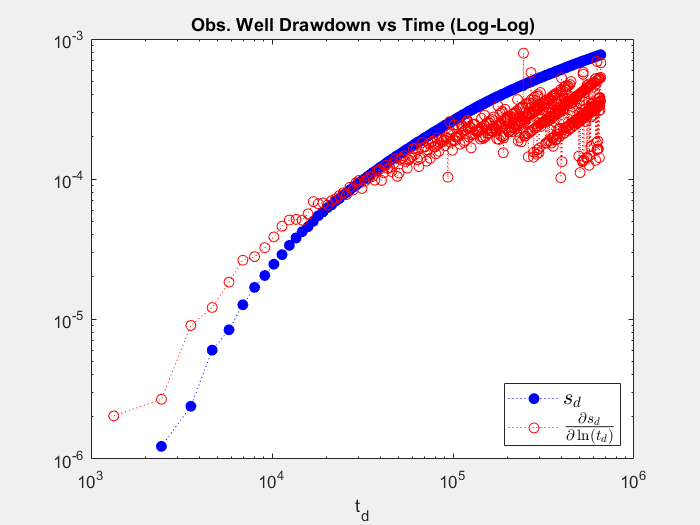

drawnow;
figure('Visible','on');
loglog(t_d_ow,s_d_ow,':ob','MarkerFaceColor','b');
hold on 
loglog(t_d_ow,num_der(t_d_ow,s_d_ow),':or')
xlabel('t_d');
title('Obs. Well Drawdown vs Time (Log-Log)');
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

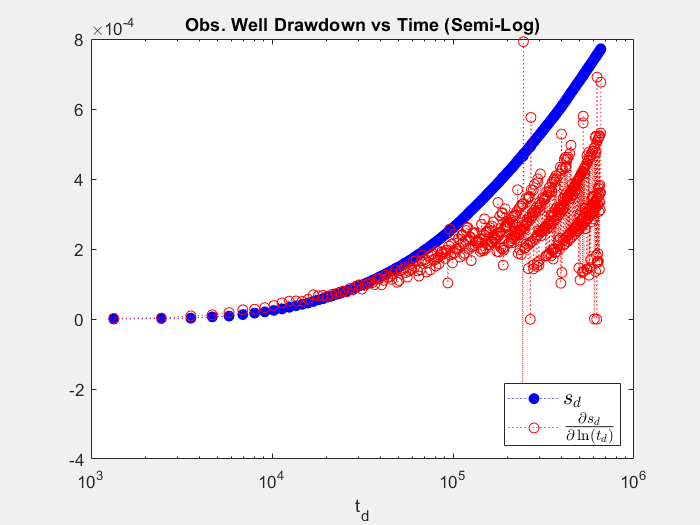


figure('Visible','on');
semilogx(t_d_ow,s_d_ow,':ob','MarkerFaceColor','b');
hold on 
semilogx(t_d_ow,num_der(t_d_ow,s_d_ow),':or')
xlabel('t_d');
title('Obs. Well Drawdown vs Time (Semi-Log)');
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

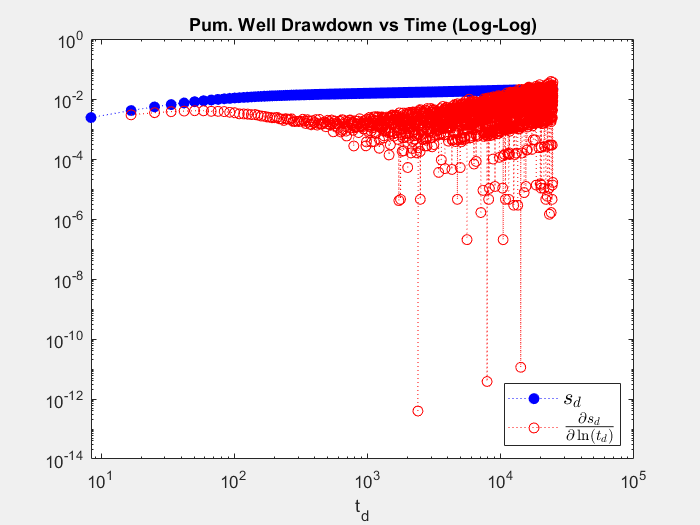

figure('Visible','on');
loglog(t_d_pw,s_d_pw,':ob','MarkerFaceColor','b');
hold on 
loglog(t_d_pw,num_der(t_d_pw,s_d_pw),':or')
xlabel('t_d');
title('Pum. Well Drawdown vs Time (Log-Log)');
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

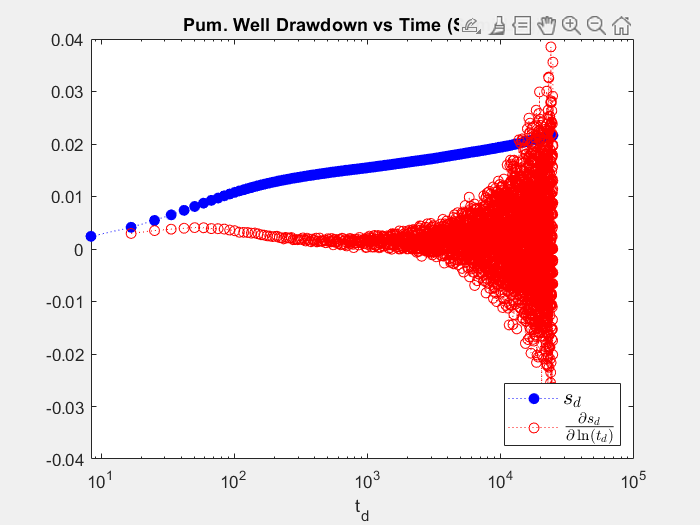

figure('Visible','on');
semilogx(t_d_pw,s_d_pw,':ob','MarkerFaceColor','b');
hold on 
semilogx(t_d_pw,num_der(t_d_pw,s_d_pw),':or')
xlabel('t_d');
title('Pum. Well Drawdown vs Time (Semi-Log)');
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

There is no convergence toward a unique classic Theis solution. The pumping and observation well curves remain far apart, and neither exhibits the expected late-time asymptotic trend. This suggests that the test did not reach full radial flow stabilization, likely due to limited pumping duration. Additional factors such as partial penetration, leakage, or double-porosity effects may also contribute. Longer pumping and diagnostic modeling would be needed to confirm aquifer behavior. However in the following we will se if we get more informations with the recovery or step drowdown test, for now we continue with our Theis fitting with dimensionsless variables.

iter = 10000;
NS_g = -1000;

for j = 1:iter
    S = 1E-7 + (1E-3+1E-3)*rand;
    T = randi([1,2000],1,1);

    % Dimensionless variables
    t_d_exp = T .* t_ow_r ./ (r_c_ow^2 .* S);
    s_c = Q / (2*pi*T);
    s_d_exp = s_ow_r / s_c;

    % Theis well function in dimensionless form
    u = 1 ./ (4 .* t_d_exp); %one because i use r instead of r_w so rd=1
    W = expint(u); % Well function
    s_d_sim = 1/2*W;   % Dimensionless drawdown

    % Nash–Sutcliffe efficiency
    NS_1 = s_d_sim - s_d_exp;
    NS_2 = s_d_exp - mean(s_d_exp);
    NS = 1 - sum(NS_1.^2) / sum(NS_2.^2);

    if NS >= NS_g
        s_final = s_d_sim;
        Opt_dimless_ow = [T,S];
        NS_g = NS;
    end
end

iter = 10000;
NS_g = -1000;

for j = 1:iter
    S = 1E-7 + (1E-3+1E-3)*rand;
    T = randi([1,2000],1,1);

    % Dimensionless variables
    t_d_exp = T .* t_pw_r./ (r_c_pw^2 .* S);
    s_c = Q / (2*pi*T);
    s_d_exp = s_pw_r / s_c;

    % Theis well function in dimensionless form
    u = 1 ./ (4 .* t_d_exp); %one because i use r instead of r_w so rd=1
    W = expint(u); % Well function
    s_d_sim = 1/2*W;   % Dimensionless drawdown

    % Nash–Sutcliffe efficiency
    NS_1 = s_d_sim - s_d_exp;
    NS_2 = s_d_exp - mean(s_d_exp);
    NS = 1 - sum(NS_1.^2) / sum(NS_2.^2);

    if NS >= NS_g
        s_final = s_d_sim;
        Opt_dimless_pw = [T,S];
        NS_g = NS;
    end
end


% Residuals in dimensionless domain
residuals_dim_ow = @(p) abs(s_ow_r.* (2*pi*p(1)./Q) - theis_dimensionsless(p,t_ow_r,r_ow,r_c_ow));
residuals_dim_pw = @(p) abs(s_pw_r.* (2*pi*p(1)./Q) - theis_dimensionsless(p,t_pw_r,r_pw));
best_params_dim_ow = lsqnonlin(residuals_dim_ow, Opt_dimless_ow, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3          21408.5        8.25e+05         0.01
     1           6          215.175         1.8e+04        0.001        118.994
     2           9          66.8803        3.57e+03       0.0001        5.65336
     3          12          6.48469             582        1e-05       0.980639
     4          15         0.231931              68        1e-06       0.546059
     5          18        0.0784427            2.38        1e-07       0.146907
     6          21        0.0782127          0.0127        1e-08      0.0141411
     7          24        0.0782126        0.000207        1e-09    0.000624883
     8          27        0.0782126        5.68e-06        1e-10    1.78731e-05
     9          30        0.0782126        1.63e-07        1e-11    4.96003e-07



best_params_dim_pw = lsqnonlin(residuals_dim_pw, Opt_dimless_pw, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3          405.095        3.97e+05         0.01
     1          10          209.783        1.19e+05          100       0.336211
     2          13          103.734        3.83e+04           10       0.279089
     3          17          54.0797        1.34e+04          100       0.231673
     4          20          32.1645        5.17e+03           10       0.192311
     5          24          21.9229        2.22e+03          100       0.159635
     6          27          16.4845        1.06e+03           10       0.132513
     7          31          13.2478             548          100       0.110004
     8          34          11.1856             303           10      0.0913276
     9          38          9.82488             175          100      0.0758327
    10          41           8.9105             105  

The dimensionless analysis confirms that transmissivity and storativity values are consistent with those obtained from the dimensional interpretation. We obtain$T=12.6648 m^3/d, S=0.0618[-]$ for the observation well and $T=5.0205m^3/d, S=0.0819[-]$, yet the curves do not converge toward a single Theis solution. This indicates that the system likely did not reach full stabilization during the test, and additional factors such as heterogeneity, partial penetration, or complex aquifer structure may be influencing the response. Let's see what we can obtain from the recovery test. The pumping finishes after 49h then we know that the recovery test begins and ends ond December 6th but we have data until December 18th. I decide to take data from the end of puping to the 18th of December bacause trying withdata until the 9th the drawdown is not stabilized yet.

startRow_3=endRow_1;

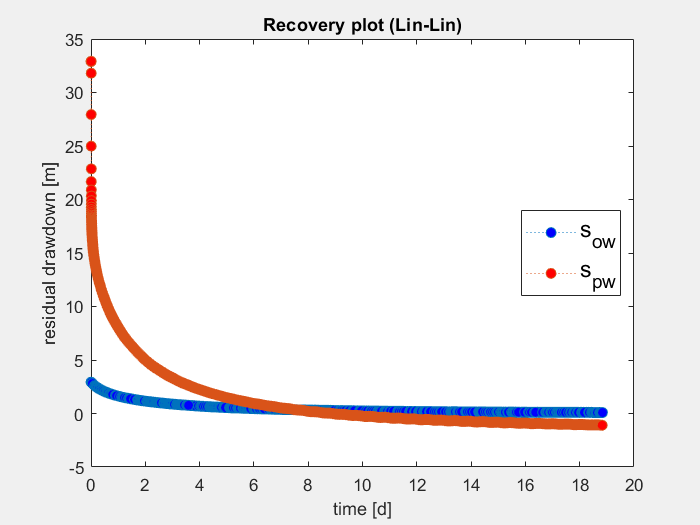

s_pw_rec = data_1.NivelAgua(startRow_3:end);
s_pw_rec = s_pw_rec - s_static_pw; % m
t_pw_rec = - t_pw(end)*24*60 + data_1.TiempoPrueba48H(startRow_3:end) ; % min
t_pw_rec((13134-endRow_1+1))= t_pw_rec((13134-endRow_1+1)) + 6 + 57/60;
t_pw_rec((13135-endRow_1+1):end)= t_pw_rec((13134-endRow_1+1)) + 10 * (1:1:length(t_pw_rec((13135-endRow_1+1):end)))';
t_pw_rec = t_pw_rec / (24*60); %d

startRow_4=endRow_2;
s_ow_rec = data_2.ProfundidadNivelPiezometricoTransductorCorregido(startRow_4:end);
s_ow_rec = s_ow_rec - s_static_ow; % m
t_ow_rec =  - t_ow(end)*24*60 + data_2.TiempoPrueba48H(startRow_4:end); % min
t_ow_rec = t_ow_rec / (24*60); %d
% t_ow_rec = t_ow_rec(s_ow_rec>=0);
% s_ow_rec = s_ow_rec(s_ow_rec>=0);
% t_pw_rec = t_pw_rec(s_pw_rec>=0);
% s_pw_rec = s_pw_rec(s_pw_rec>=0);

figure('Visible','on');
plot(t_ow_rec,s_ow_rec,':o','MarkerFaceColor','b');
hold on
plot(t_pw_rec,s_pw_rec,':o','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('residual drawdown [m]');
title('Recovery plot (Lin-Lin)');
legend('s_{ow}','s_{pw}','FontSize', 14, 'Location', 'east');

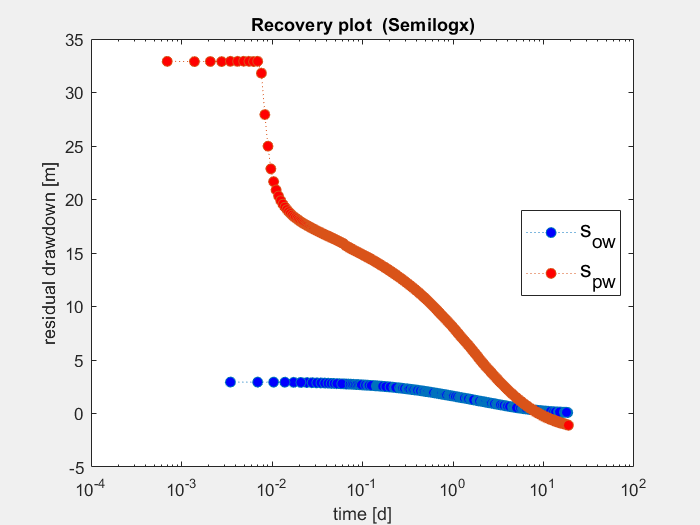

drawnow;

figure('Visible','on');
semilogx(t_ow_rec,s_ow_rec,':o','MarkerFaceColor','b');
hold on
semilogx(t_pw_rec,s_pw_rec,':o','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('residual drawdown [m]');
title('Recovery plot  (Semilogx)');
legend('s_{ow}','s_{pw}','FontSize', 14, 'Location', 'east');

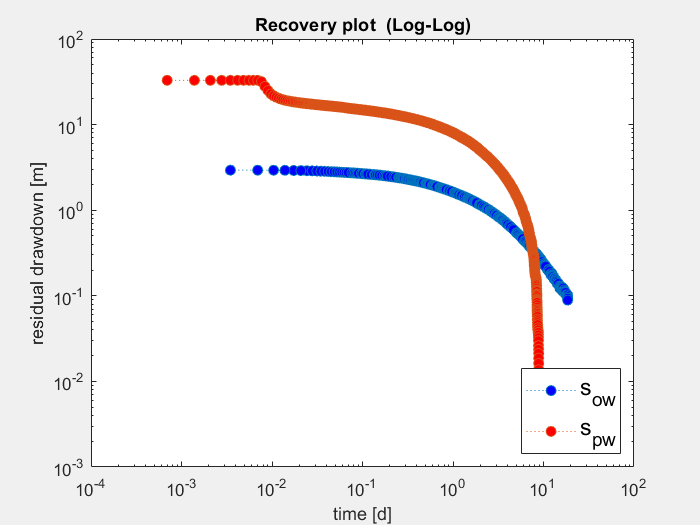

drawnow;

figure('Visible','on');
loglog(t_ow_rec,s_ow_rec,':o','MarkerFaceColor','b');
hold on
loglog(t_pw_rec,s_pw_rec,':o','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('residual drawdown [m]');
title('Recovery plot  (Log-Log)');
legend('s_{ow}','s_{pw}','FontSize', 14, 'Location', 'southeast');

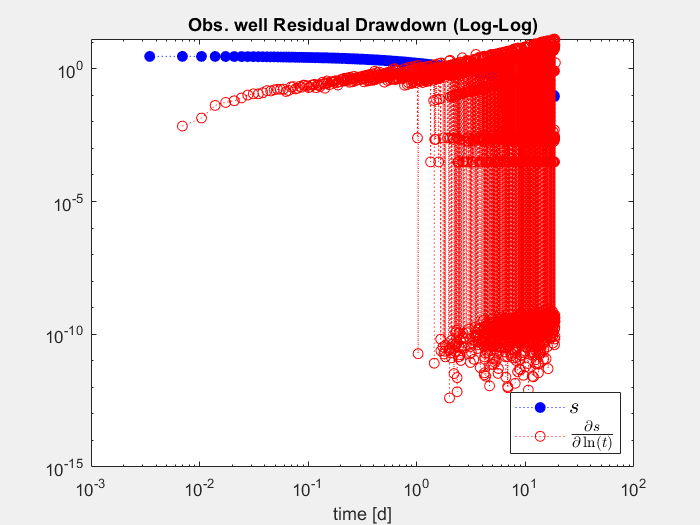

figure('Visible','on');
loglog(t_ow_rec,s_ow_rec,':ob','MarkerFaceColor','b');
hold on 
loglog(t_ow_rec,abs(num_der(t_ow_rec,s_ow_rec)),':or'); %abs because is decreasing and we are in loglog scale
xlabel('time [d]');
title('Obs. well Residual Drawdown (Log-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

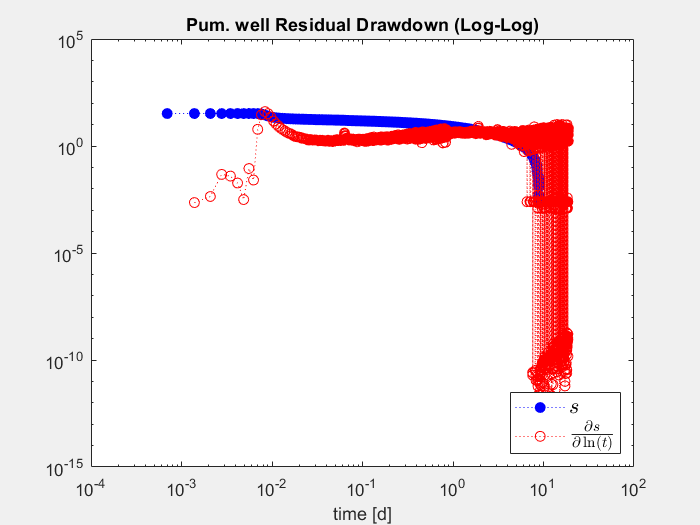

figure('Visible','on');
loglog(t_pw_rec,s_pw_rec,':ob','MarkerFaceColor','b');
hold on 
loglog(t_pw_rec,abs(num_der(t_pw_rec,s_pw_rec)),':or'); %abs because is decreasing and we are in loglog scale
xlabel('time [d]');
title('Pum. well Residual Drawdown (Log-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

The residual drawdown curves (blue) in both pumping and observation wells show the expected decreasing trend over time on a log-log scale. The diagnostic derivative (red) was plotted using its absolute value to avoid issues with negative signs in logarithmic representation. However, the derivative appears noisy at late times, likely due to very small residual drawdown values approaching zero, which amplifies numerical instability.Intermediate times tend toward radial flow, although the observation well curve remains flatter due to distance from the pumping well. Let's try to fit with the proposed solution in the slides.

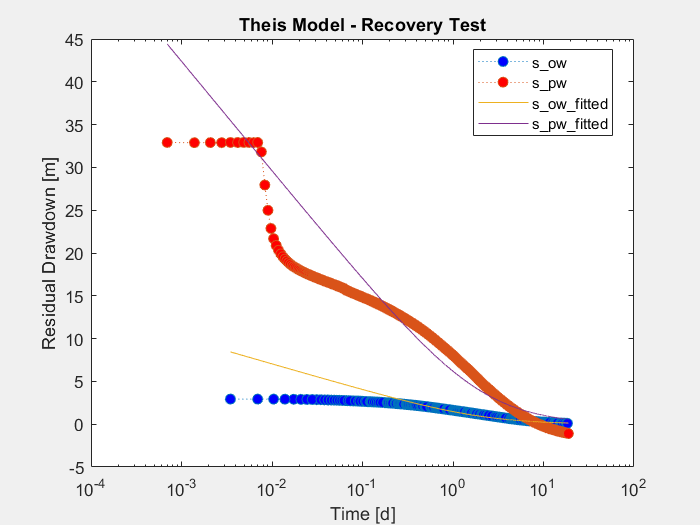

t=30;
t_end=length(t_ow_rec);

G_ow_rec = [log10((49/24+t_ow_rec(t:t_end))./t_ow_rec(t:t_end))];
p_ow_rec = (G_ow_rec'*G_ow_rec)\(G_ow_rec'*s_ow_rec(t:t_end));
CJ_param_ow_rec = 2.3 * Q/(4*pi*p_ow_rec);

t=37;
t_end=577;
t_end=length(t_pw_rec);


G_pw_rec = [log10((49/24+t_pw_rec(t:t_end))./t_pw_rec(t:t_end))];
p_pw_rec = (G_pw_rec'*G_pw_rec)\(G_pw_rec'*s_pw_rec(t:t_end));
CJ_param_pw_rec = 2.3 * Q/(4*pi*p_pw_rec);

figure('Visible','on');
semilogx(t_ow_rec,s_ow_rec,':o','MarkerFaceColor','b');
hold on
semilogx(t_pw_rec,s_pw_rec,':o','MarkerFaceColor','r');


semilogx(t_ow_rec,(2.3*Q)./(4*pi*CJ_param_ow_rec).*log10((49/24+t_ow_rec)./t_ow_rec))
semilogx(t_pw_rec,(2.3*Q)./(4*pi*CJ_param_pw_rec).*log10((49/24+t_pw_rec)./t_pw_rec))

title('Theis Model - Recovery Test');
xlabel('Time [d]');
ylabel('Residual Drawdown [m]');
legend({'s\_ow', 's\_pw', 's\_ow\_fitted', 's\_pw\_fitted'}, ...
       'Location', 'best');

The fit for the observation well works and provide a transmissivity value consistent with previous pumping analysis. In contrast, the pumping well fit is unreliable: early-time data are dominated by wellbore storage and skin effects, and there is an offset likely caused by natural trends (regional gradient or recharge) that are not accounted for in the recovery model. These factors violate the assumptions of the straight-line method, making the pumping well fit less accurate.

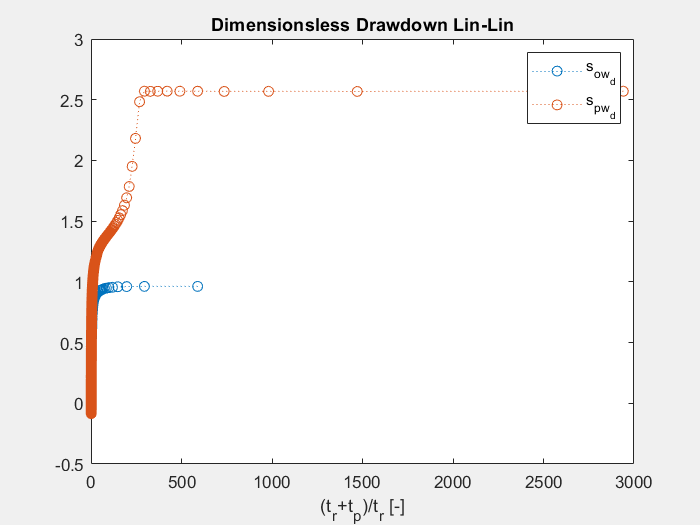

s_ow_rec_dless=s_ow_rec./(2.3*Q/(4*pi*CJ_param_ow_rec));
s_pw_rec_dless=s_pw_rec./(2.3*Q/(4*pi*CJ_param_pw_rec));
figure('Visible','on');
plot((t_ow_rec(2:end)+49/24)./t_ow_rec(2:end),s_ow_rec_dless(2:end),':o')
hold on
plot((t_pw_rec(2:end)+49/24)./t_pw_rec(2:end),s_pw_rec_dless(2:end),':o')
xlabel("(t_r+t_p)/t_r [-]")
legend('s_{ow_d}','s_{pw_d}')
title("Dimensionsless Drawdown Lin-Lin")

figure('Visible','on');
plot((t_ow_rec(2:end)+49/24)./t_ow_rec(2:end),s_ow_rec_dless(2:end),':o')
hold on
plot((t_pw_rec(2:end)+49/24)./t_pw_rec(2:end),s_pw_rec_dless(2:end),':o')
xlabel("(t_r+t_p)/t_r [-]")
legend('s_{ow_d}','s_{pw_d}')
title("Dimensionsless Drawdown Lin-Lin")

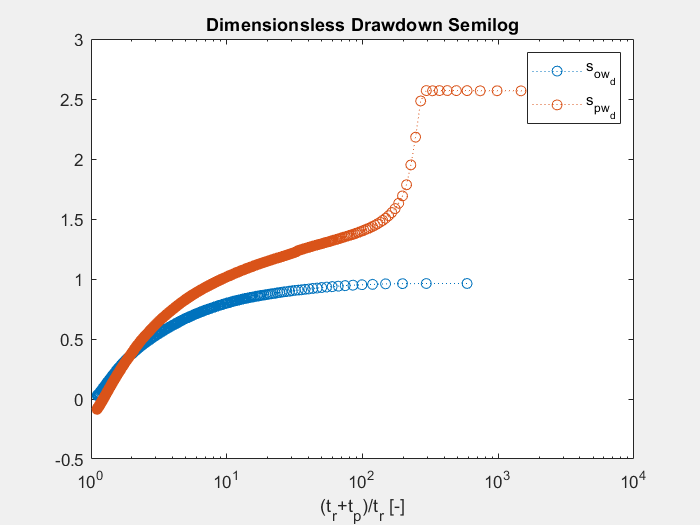


figure('Visible','on');
semilogx((t_ow_rec(2:end)+49/24)./t_ow_rec(2:end),s_ow_rec_dless(2:end),':o')
hold on
semilogx((t_pw_rec(2:end)+49/24)./t_pw_rec(2:end),s_pw_rec_dless(2:end),':o')
xlabel("(t_r+t_p)/t_r [-]")
legend('s_{ow_d}','s_{pw_d}')
title("Dimensionsless Drawdown Semilog")


figure('Visible','on');
loglog((t_ow_rec+49/24)./t_ow_rec,s_ow_rec_dless,':o')
hold on
%loglog((t_ow_rec+49/24)./t_ow_rec,abs(num_der((t_ow_rec+49/24)./t_ow_rec,s_ow_rec_dless)),':o')
loglog((t_pw_rec+49/24)./t_pw_rec,s_pw_rec_dless,':o')
%loglog((t_pw_rec+49/24)./t_pw_rec,abs(num_der((t_pw_rec+49/24)./t_pw_rec,s_pw_rec_dless)),':o')
xlabel("(t_r+t_p)/t_r [-]")
legend('s_{ow_d}','ds_ow_{dln_{t_d}}','s_{pw_d}','ds_pw_{dln_{t_d}}')

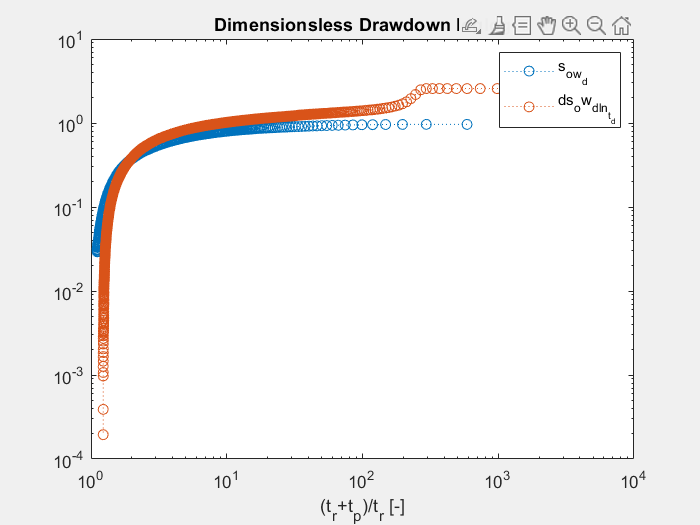

title("Dimensionsless Drawdown loglog")

Dimensionless analysis shows that pumping and observation wells behave similarly, confirming consistent aquifer response. However, pumping well data are strongly affected by wellbore storage and natural trends, making reliable fitting (at least with standard theis or CJ) impractical. Therefore, transmissivity estimates should rely on observation well data before validating with the step-drawdown test, which is used to assess well performance and identify head losses (linear and non-linear) for efficiency evaluation.

s_escalonada_pw = data_1.NivelAgua(1446:8932);

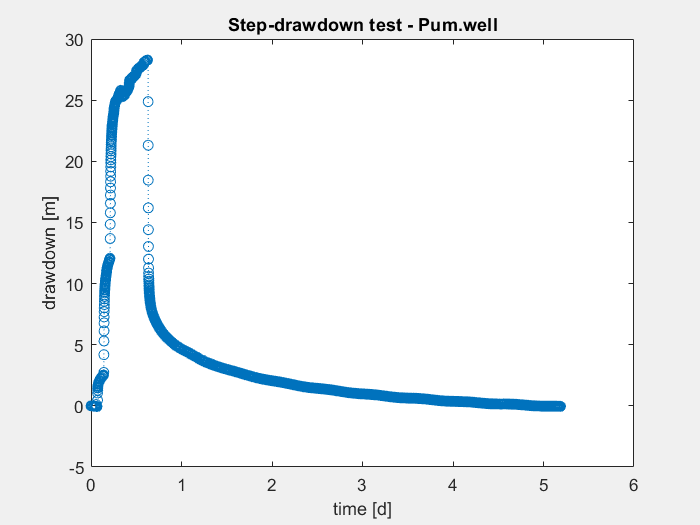

s_escalonada_pw = s_escalonada_pw-s_escalonada_pw(1);
s_escalonada_pw = s_escalonada_pw(2:end); %m
t_escalonada_pw = 1:length(s_escalonada_pw); %min
t_escalonada_pw = t_escalonada_pw/(60*24);


figure('Visible','on');
plot(t_escalonada_pw,s_escalonada_pw,':o')
xlabel('time [d]')
ylabel('drawdown [m]')
title('Step-drawdown test - Pum.well')

We can clearly see the three different drawdown steps, let's see what happens in the observation well. 

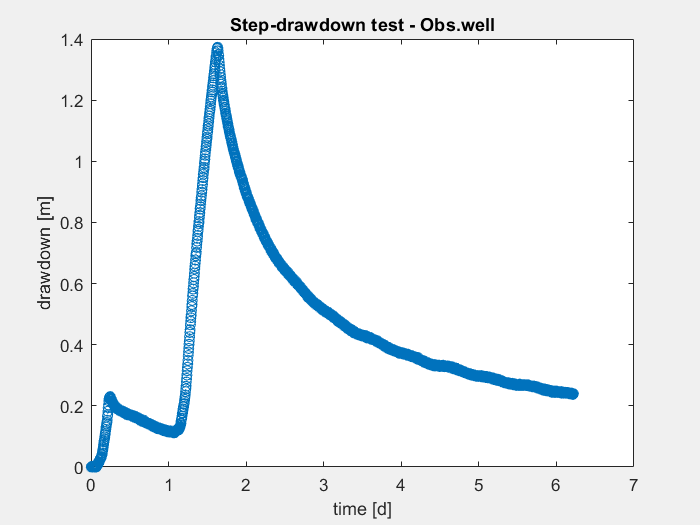

s_escalonada_ow=data_2.ProfundidadNivelPiezometricoTransductorCorregido(1180:2971);
s_escalonada_ow = s_escalonada_ow-s_escalonada_ow(1);
s_escalonada_ow = s_escalonada_ow(2:end); %m
t_escalonada_ow = 1:length(s_escalonada_ow); %min
t_escalonada_ow = 5*t_escalonada_ow/(60*24); %5 is the delta time in that case

figure('Visible','on');
plot(t_escalonada_ow,s_escalonada_ow,':o')
xlabel('time [d]')
ylabel('drawdown [m]')
title('Step-drawdown test - Obs.well')

Here we just see a single increase in drawdown relative to the step-drawdown test, the first increase is due to the first failed step-drawdown attempt. This behavior may be due either to the short duration of the first steps or to a low aquifer transmissivity, which caused the observation well to show a continuous decline instead of distinct drawdowns. To analyze the step-drawdown test we use the Eden-Hazel's method, the first step is to compute the following values:


$$H_n=\sum_{i=1}^n\Delta Q_i \log(t-t_i)$$


where: $t $ is the time since the step-drawdown test started, $t_i$ is the time at wich the $i_{th}$ step begins, $\Delta Q_i$ is the discharge increment begenning at time $t_i$. The first thing that we need to do is to identify the $t_i$. 

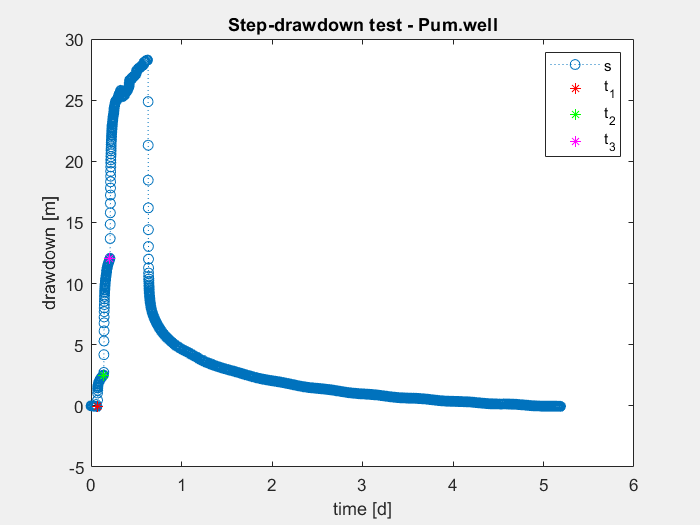

t_1 = t_escalonada_pw(102);
t_2 = t_escalonada_pw(202);
t_3 = t_escalonada_pw(302);
t_end = t_escalonada_pw(908);

figure('Visible','on');
plot(t_escalonada_pw,s_escalonada_pw,':o')
hold on
plot(t_1,s_escalonada_pw(102),'r*')
plot(t_2,s_escalonada_pw(202),'g*')
plot(t_3,s_escalonada_pw(302),'m*')
xlabel('time [d]')
ylabel('drawdown [m]')
title('Step-drawdown test - Pum.well')
legend('s','t_1','t_2','t_3')

Now that we have identified the $t_i$, we can proceed by definining the $\Delta Q_i$.

DQ_1 = 0.5 *  60 * 60 * 24 / 1000; %m^3/d
DQ_2 = (1.4 - 0.5) *  60 * 60 * 24 / 1000; %m^3/d
DQ_3 = (2.2 - 1.4) *  60 * 60 * 24 / 1000; %m^3/d

Actually we restrict the vectors to the three drawdown steps.

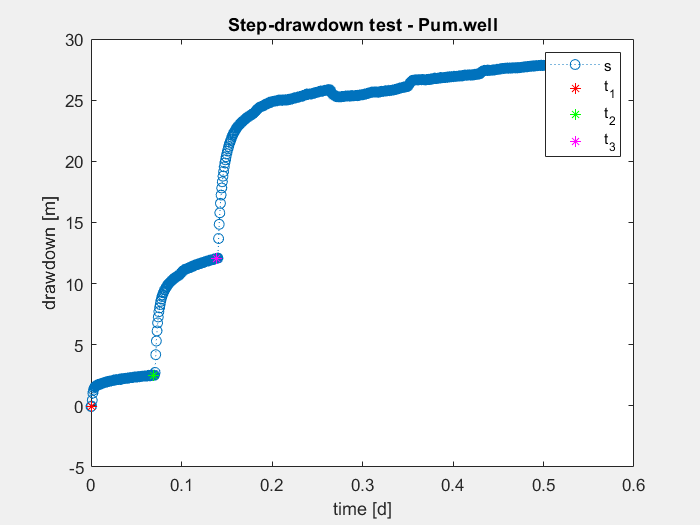

t_1_idx = 1;
t_2_idx = 101;
t_3_idx = 201;
t_escalonada_pw = (0:(length(t_escalonada_pw(102:908))-1))/(24*60);
s_escalonada_pw = s_escalonada_pw(102:908);
t_1 = t_escalonada_pw(t_1_idx);   
t_2 = t_escalonada_pw(t_2_idx);  
t_3 = t_escalonada_pw(t_3_idx);  

figure('Visible','on');
plot(t_escalonada_pw,s_escalonada_pw,':o')
hold on
plot(t_1,s_escalonada_pw(t_1_idx),'r*')
plot(t_2,s_escalonada_pw(t_2_idx),'g*')
plot(t_3,s_escalonada_pw(t_3_idx),'m*')
xlabel('time [d]')
ylabel('drawdown [m]')
title('Step-drawdown test - Pum.well')
legend('s','t_1','t_2','t_3')

Now we can compute $H_n$:

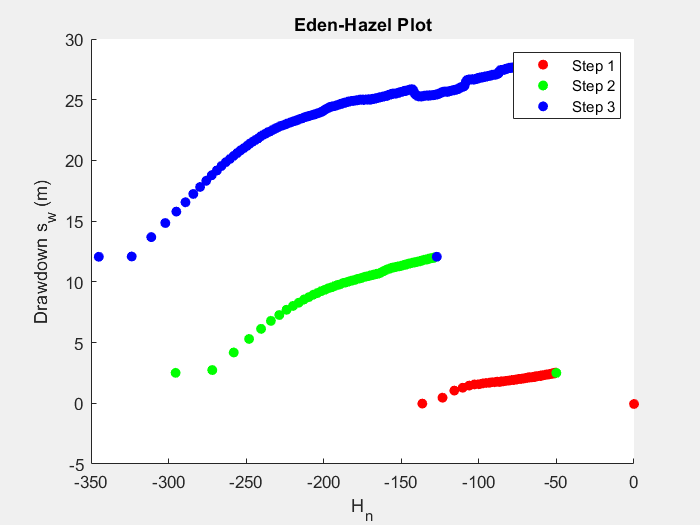

H = zeros(size(t_escalonada_pw));
for k = 1:length(t_escalonada_pw)
    t = t_escalonada_pw(k);
    % Compute terms just if t>t_i
    term1 = 0; term2 = 0; term3 = 0;
    if t > t_1
        term1 = DQ_1 * log10(t - t_1);
    end
    if t > t_2
        term2 = DQ_2 * log10(t - t_2);
    end
    if t > t_3
        term3 = DQ_3 * log10(t - t_3);
    end
    H(k) = term1 + term2 + term3;
end
idx1 = t_escalonada_pw >= t_1 & t_escalonada_pw < t_2;
idx2 = t_escalonada_pw >= t_2 & t_escalonada_pw < t_3;
idx3 = t_escalonada_pw >= t_3;
figure('Visible','on');
hold on
scatter(H(idx1), s_escalonada_pw(idx1), 'r', 'filled'); % Step 1
scatter(H(idx2), s_escalonada_pw(idx2), 'g', 'filled'); % Step 2
scatter(H(idx3), s_escalonada_pw(idx3), 'b', 'filled'); % Step 3
xlabel('H_n'); ylabel('Drawdown s_w (m)');
title('Eden-Hazel Plot');
legend('Step 1','Step 2','Step 3');

Th e problem is that time in days is too little and the logarithm is negative so we should go back to min.

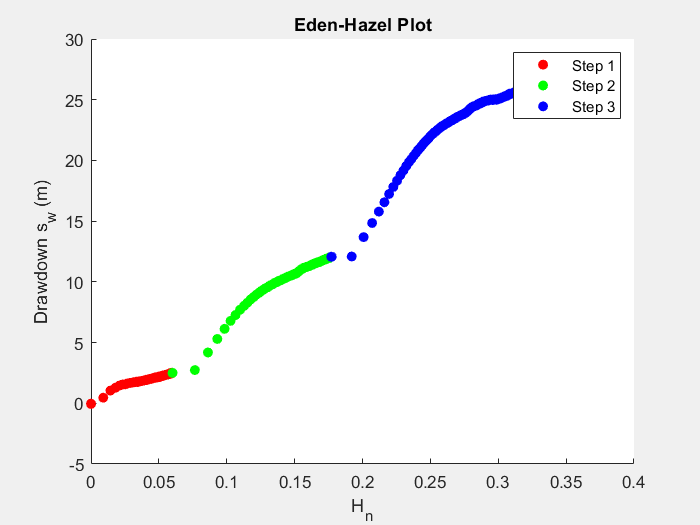

Q_1= 0.5*60 / 1000; %m^3/min
Q_2= 1.4*60 / 1000; %m^3/min
Q_3= 2.2*60 / 1000; %m^3/min
DQ_1 = Q_1;
DQ_2 = Q_2-Q_1;
DQ_3 = Q_3-Q_2;
t_escalonada_pw = t_escalonada_pw*24*60;
t_1 = t_escalonada_pw(t_1_idx);   
t_2 = t_escalonada_pw(t_2_idx);  
t_3 = t_escalonada_pw(t_3_idx);
H = zeros(size(t_escalonada_pw));
for k = 1:length(t_escalonada_pw)
    t = t_escalonada_pw(k);
    % Compute terms just if t>t_i
    term1 = 0; term2 = 0; term3 = 0;
    if t > t_1
        term1 = DQ_1 * log10(t - t_1);
    end
    if t > t_2
        term2 = DQ_2 * log10(t - t_2);
    end
    if t > t_3
        term3 = DQ_3 * log10(t - t_3);
    end
    H(k) = term1 + term2 + term3;
end
idx1 = t_escalonada_pw >= t_1 & t_escalonada_pw < t_2;
idx2 = t_escalonada_pw >= t_2 & t_escalonada_pw < t_3;
idx3 = t_escalonada_pw >= t_3;
figure('Visible','on');
hold on
scatter(H(idx1), s_escalonada_pw(idx1), 'r', 'filled'); % Step 1
scatter(H(idx2), s_escalonada_pw(idx2), 'g', 'filled'); % Step 2
scatter(H(idx3), s_escalonada_pw(idx3), 'b', 'filled'); % Step 3
xlabel('H_n'); ylabel('Drawdown s_w (m)');
title('Eden-Hazel Plot');
legend('Step 1','Step 2','Step 3');

 Now we have to draw parallel straight lines of best fit.

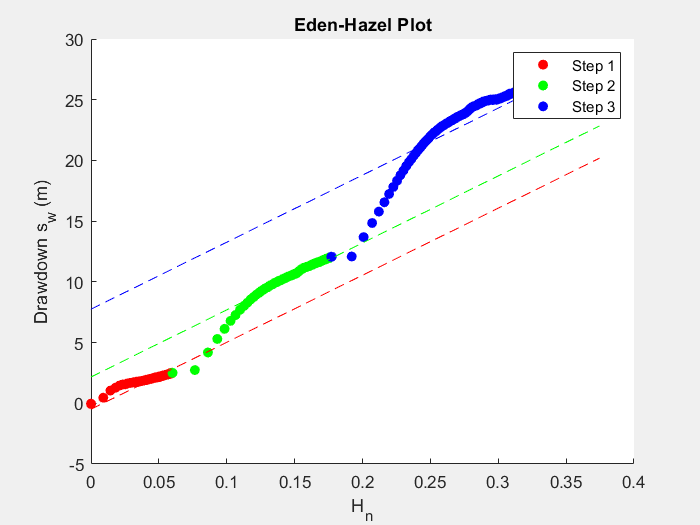

    p1 = polyfit(H(idx1), s_escalonada_pw(idx1), 1); 
    p2 = polyfit(H(idx2), s_escalonada_pw(idx2), 1);
    p3 = polyfit(H(idx3), s_escalonada_pw(idx3), 1);
    
    b_mean = mean([p1(1), p2(1), p3(1)]);
    
    A1 = mean(s_escalonada_pw(idx1)) - b_mean * mean(H(idx1));
    A2 = mean(s_escalonada_pw(idx2)) - b_mean * mean(H(idx2));
    A3 = mean(s_escalonada_pw(idx3)) - b_mean * mean(H(idx3));
    
    x_fit = linspace(min([H(idx1)';H(idx2)';H(idx3)']), max([H(idx1)';H(idx2)';H(idx3)']), 100);
    figure('Visible','on');
    hold on
    scatter(H(idx1), s_escalonada_pw(idx1), 'r', 'filled'); % Step 1
    scatter(H(idx2), s_escalonada_pw(idx2), 'g', 'filled'); % Step 2
    scatter(H(idx3), s_escalonada_pw(idx3), 'b', 'filled'); % Step 3
    xlabel('H_n'); ylabel('Drawdown s_w (m)');
    title('Eden-Hazel Plot');
    plot(x_fit, b_mean*x_fit + A1, 'r--');
    plot(x_fit, b_mean*x_fit + A2, 'g--');
    plot(x_fit, b_mean*x_fit + A3, 'b--');
    legend('Step 1','Step 2','Step 3');

disp('b:'); disp(b_mean);

b:
   55.2001



disp('Intercepts A1, A2, A3:'); disp([A1, A2, A3]);

Intercepts A1, A2, A3:
   -0.4936    2.1684    7.7491



This is not good, we have to ger rid of the stabilization part, before fitting.

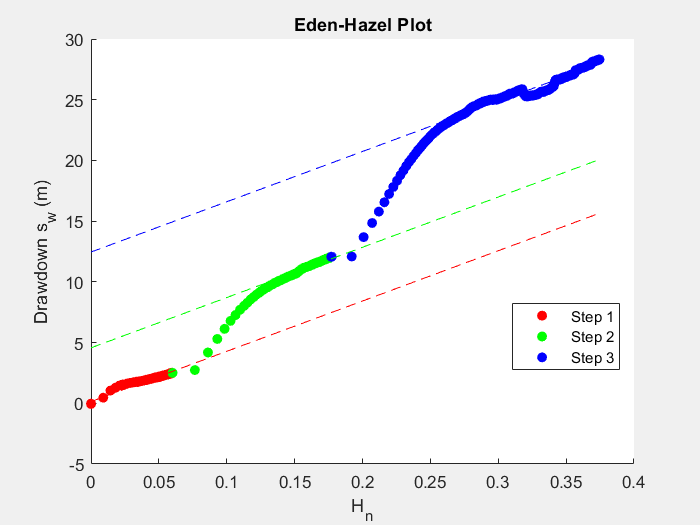

H1=H(idx1);
s1 = s_escalonada_pw(idx1);
H1=H1(8:end);
s1 = s1(8:end);

H2=H(idx2);
s2 = s_escalonada_pw(idx2);
H2=H2(16:end);
s2=s2(16:end);

H3=H(idx3);
s3 =s_escalonada_pw(idx3);
s3 = s3(30:end);
H3=H3(30:end);

    p1 = polyfit(H1, s1, 1);
    p2 = polyfit(H2,s2, 1);
    p3 = polyfit(H3,s3, 1);
    
    b_mean = mean([p1(1),p2(1),p3(1)]);
    
   
    A1 = mean(s1) - b_mean * mean(H1);
    A2 = mean(s2) - b_mean * mean(H2);
    A3 = mean(s3) - b_mean * mean(H3);
    
    
    x_fit = linspace(min([H(idx1)';H(idx2)';H(idx3)']), max([H(idx1)';H(idx2)';H(idx3)']), 100);
    figure('Visible','on');
    hold on
    scatter(H(idx1), s_escalonada_pw(idx1), 'r', 'filled'); % Step 1
    scatter(H(idx2), s_escalonada_pw(idx2), 'g', 'filled'); % Step 2
    scatter(H(idx3), s_escalonada_pw(idx3), 'b', 'filled'); % Step 3
    xlabel('H_n'); ylabel('Drawdown s_w (m)');
    title('Eden-Hazel Plot');
    plot(x_fit, b_mean*x_fit + A1, 'r--');
    plot(x_fit, b_mean*x_fit + A2, 'g--');
    plot(x_fit, b_mean*x_fit + A3, 'b--');
    legend('Step 1','Step 2','Step 3','Location','best');

b=b_mean/1440;
fprintf('b: %g m^2/d\n', b);

b: 0.0287573 m^2/d


disp('Intercepts A1, A2, A3 [m] :'); disp([A1, A2, A3]);

Intercepts A1, A2, A3 [m] :
    0.1397    4.5663   12.4544



Now that we have the $A_i$ values we need to compute the ratio $\frac{A_i}{Q_i }$ and plot this values versus the $Q_i$ ones and lastly fit a straight line trough these points.

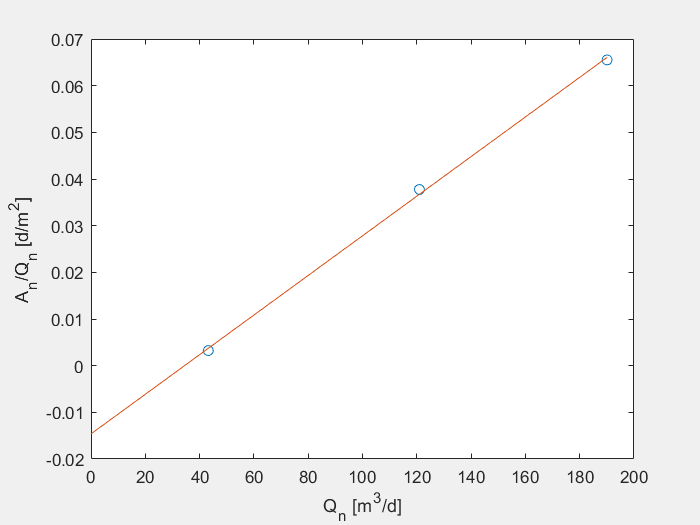

A=[A1,A2,A3];
Q=[Q_1,Q_2,Q_3]*60*24; %m^3/d
p4 = polyfit(Q,A./Q,1);
x=linspace(0,Q(end),10);
figure('Visible','on');
plot(Q,A./Q,'o')
hold on
plot(x,p4(1)*x+p4(2))
T=2.3/(4*pi*b); %m^3/d
C=p4(1);
xlabel('Q_n [m^3/d]'); ylabel('A_n/Q_n [d/m^2]');

The problem is that the value of a is negative (also if slightly, but this causes the efficiency to be greater than 100). So let's see what happens using the Hantush-Bierschenk's method.First we plot the observed drawdown in the well versus the time in semilog scale and fit the curves.

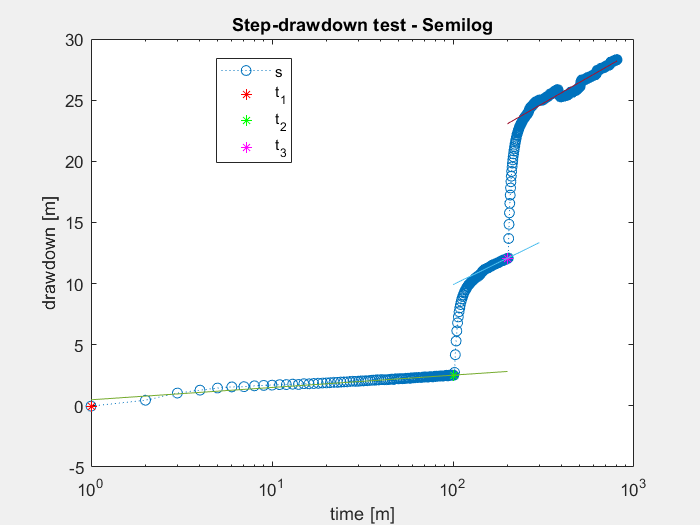

figure('Visible','on');
semilogx(t_escalonada_pw,s_escalonada_pw,':o')
hold on
semilogx(1  ,s_escalonada_pw(t_1_idx),'r*')
semilogx(t_2,s_escalonada_pw(t_2_idx),'g*')
semilogx(t_3,s_escalonada_pw(t_3_idx),'m*')
xlabel('time [m]')
ylabel('drawdown [m]')
title('Step-drawdown test - Semilog')
legend('s','t_1','t_2','t_3','Location','best')
step1 = polyfit(log10(t_escalonada_pw(50:(t_2_idx-1))), s_escalonada_pw(50:(t_2_idx-1)), 1);
step2 = polyfit(log10(t_escalonada_pw((t_2_idx+50):(t_3_idx-1))), s_escalonada_pw((t_2_idx+50):(t_3_idx-1)), 1);
step3 = polyfit(log10(t_escalonada_pw((t_3_idx+100):end)), s_escalonada_pw((t_3_idx+100):end), 1);
hold on
semilogx(t_escalonada_pw(1:(t_2_idx+100)),step1(1)*log10(t_escalonada_pw(1:(t_2_idx+100)))+step1(2),'HandleVisibility', 'off')
semilogx(t_escalonada_pw(t_2_idx:(t_3_idx+100)),step2(1)*log10(t_escalonada_pw(t_2_idx:(t_3_idx+100)))+step2(2),'HandleVisibility', 'off')
semilogx(t_escalonada_pw(t_3_idx:end),step3(1)*log10(t_escalonada_pw(t_3_idx:end))+step3(2),'HandleVisibility', 'off')

Now we compute the Δsw(i) for each step by taking the difference between the observed drawdown at a fixed time interval Δt, taken from the beginning of each step, and the corresponding drawdown on the extrapolated curve of the preceding step.

t=95; %min
ds1=step1(1)*log10(t_escalonada_pw(t+t_1_idx))+step1(2);
ds2=step2(1)*log10(t_escalonada_pw(t+t_2_idx))+step2(2) - step1(1)*log10(t_escalonada_pw(t+t_2_idx)) - step1(2);
ds3=step3(1)*log10(t_escalonada_pw(t+t_3_idx))+step3(2) - step2(1)*log10(t_escalonada_pw(t+t_3_idx)) - step2(2);

s_w_1 = ds1;
s_w_2 = ds1 + ds2;
s_w_3 = ds1 + ds2 + ds3;

y = [s_w_1 s_w_2 s_w_3];

fit = polyfit(Q,y./Q,1);

figure('Visible','on');
plot(Q,y./Q,'o')
hold on

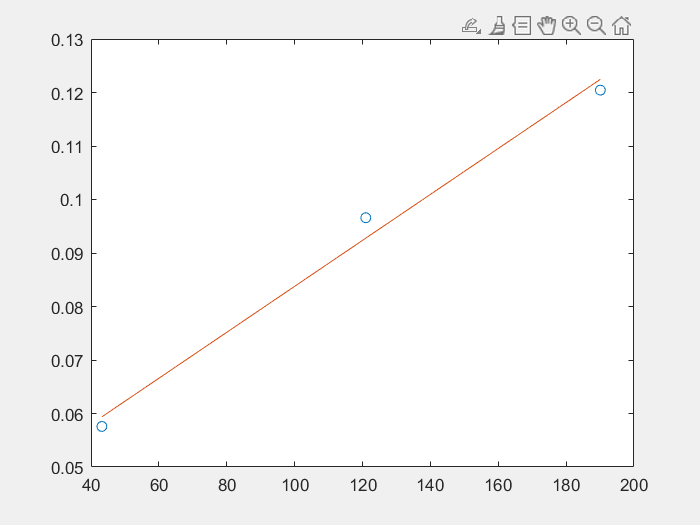

plot(Q,fit(1)*Q+fit(2))

C_new=fit(1);
B_new=fit(2);
eff = B_new./(B_new+C_new*Q)*100;

The step-drawdown test analysis using the Hantush-Bierschenk method provided the coefficients **B = 0.0408** and **C = 4.30 × 10⁻⁴**. Parameter **B** represents aquifer losses, while **C** accounts for well losses due to turbulence. The calculated well efficiency decreases with increasing discharge: approximately **69% at 0.5 L/s**, **44% at 1.4 L/s**, and **33% at 2.2 L/s**. This trend indicates that the aquifer has good transmissivity, but the well experiences significant additional losses at higher pumping rates, suggesting that well design or development could be optimized to reduce turbulence effects. Let's focus on the single steps with the various plots including the diagnostic ones.

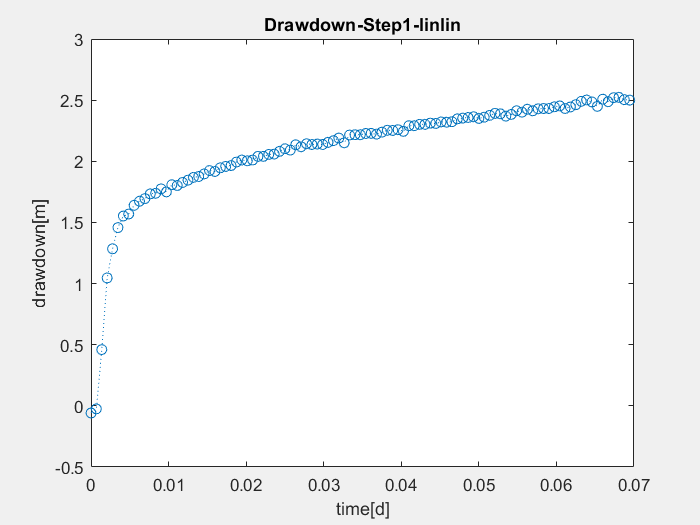

t_escalonada_pw=t_escalonada_pw/(60*24);
figure('Visible','on');
plot(t_escalonada_pw(1:t_2_idx),s_escalonada_pw(1:t_2_idx),':o')
hold on
title('Drawdown-Step1-linlin')
xlabel('time[d]')
ylabel('drawdown[m]')

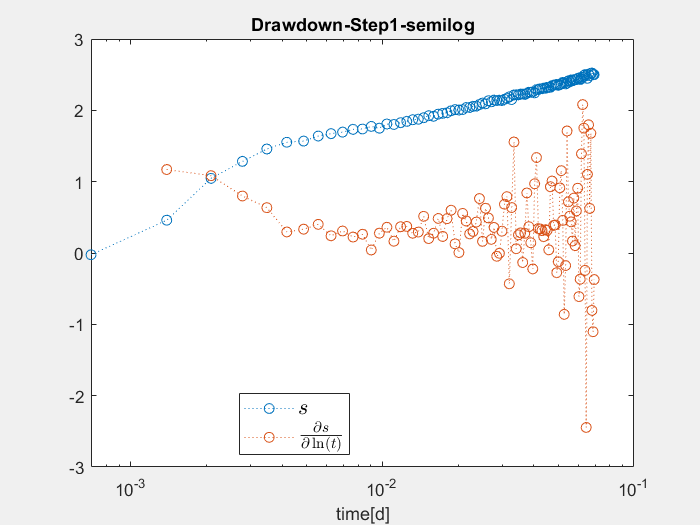


figure('Visible','on');
semilogx(t_escalonada_pw(1:t_2_idx),s_escalonada_pw(1:t_2_idx),':o')
hold on
semilogx(t_escalonada_pw(1:t_2_idx),num_der(t_escalonada_pw(1:t_2_idx),s_escalonada_pw(1:t_2_idx)),':o')
title('Drawdown-Step1-semilog')
xlabel('time[d]')
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

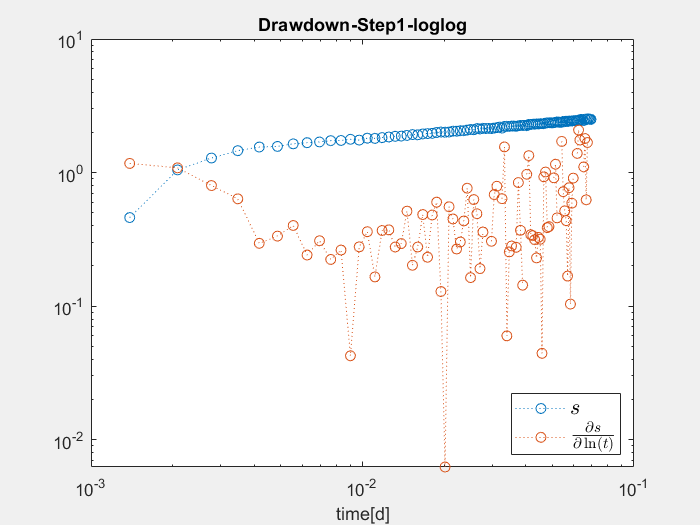


figure('Visible','on');
loglog(t_escalonada_pw(1:t_2_idx),s_escalonada_pw(1:t_2_idx),':o')
hold on
loglog(t_escalonada_pw(1:t_2_idx),num_der(t_escalonada_pw(1:t_2_idx),s_escalonada_pw(1:t_2_idx)),':o')
title('Drawdown-Step1-loglog')
xlabel('time[d]')
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

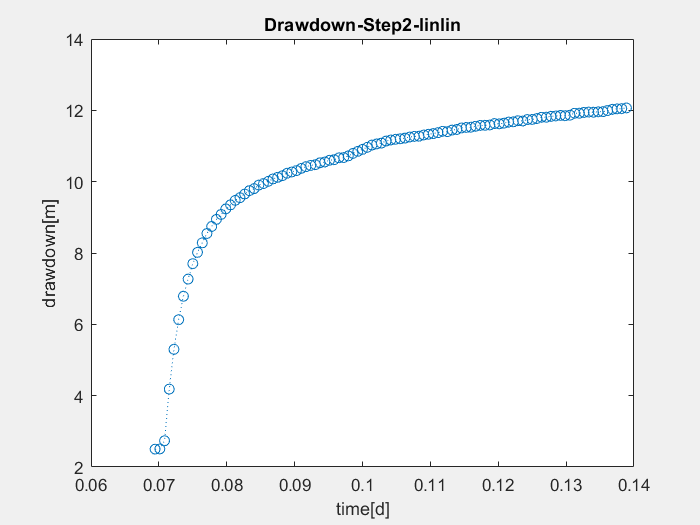


figure('Visible','on');
plot(t_escalonada_pw(t_2_idx:t_3_idx),s_escalonada_pw(t_2_idx:t_3_idx),':o')
title('Drawdown-Step2-linlin')
xlabel('time[d]')
ylabel('drawdown[m]')

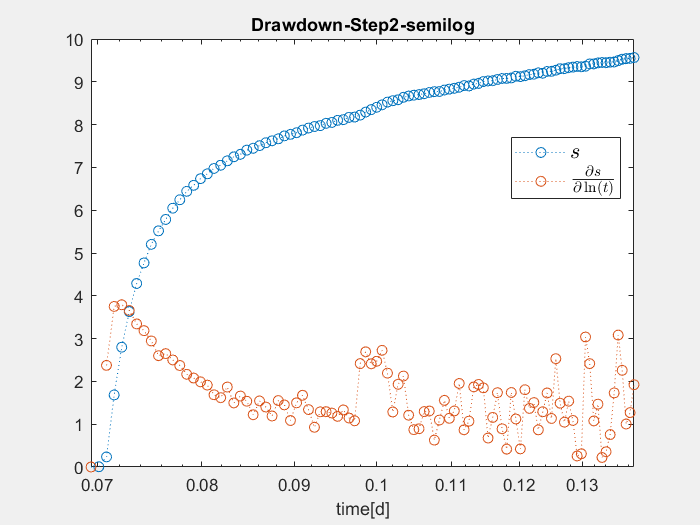


figure('Visible','on');
semilogx(t_escalonada_pw(t_2_idx:t_3_idx),s_escalonada_pw(t_2_idx:t_3_idx)-s_escalonada_pw(t_2_idx),':o')
hold on
semilogx(t_escalonada_pw(t_2_idx:t_3_idx),num_der(t_escalonada_pw(t_1_idx:t_2_idx),s_escalonada_pw(t_2_idx:t_3_idx)),':o')
title('Drawdown-Step2-semilog')
xlabel('time[d]')
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

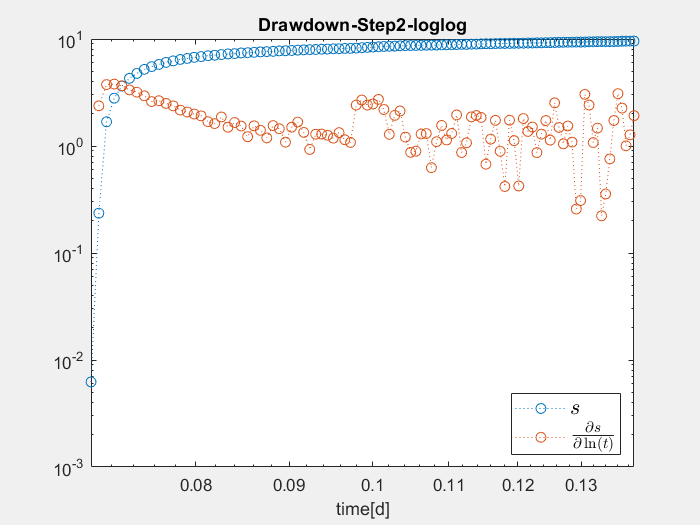


figure('Visible','on');
loglog(t_escalonada_pw(t_2_idx:t_3_idx),s_escalonada_pw(t_2_idx:t_3_idx)-s_escalonada_pw(t_2_idx),':o')
hold on
loglog(t_escalonada_pw(t_2_idx:t_3_idx),num_der(t_escalonada_pw(t_1_idx:t_2_idx),s_escalonada_pw(t_2_idx:t_3_idx)),':o')
title('Drawdown-Step2-loglog')
xlabel('time[d]')
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

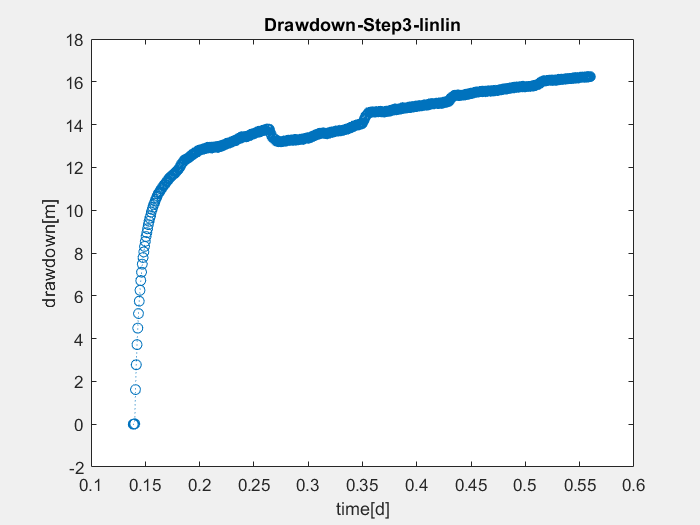



figure('Visible','on');
plot(t_escalonada_pw(t_3_idx:end),s_escalonada_pw(t_3_idx:end)-s_escalonada_pw(t_3_idx),':o')
title('Drawdown-Step3-linlin')
xlabel('time[d]')
ylabel('drawdown[m]')

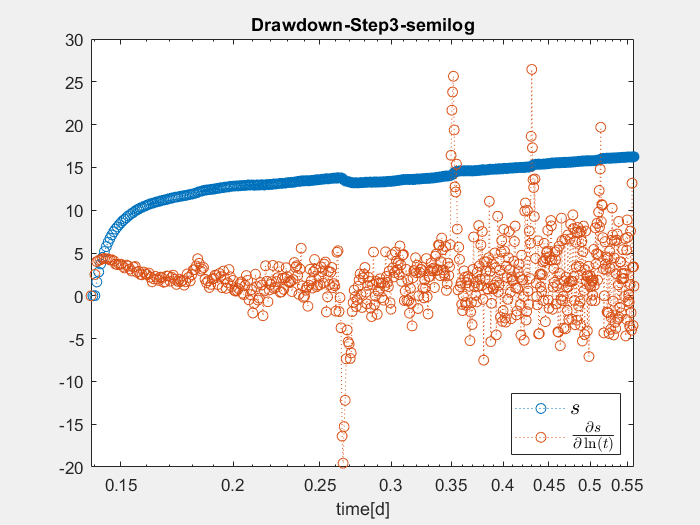


figure('Visible','on');
semilogx(t_escalonada_pw(t_3_idx:end),s_escalonada_pw(t_3_idx:end)-s_escalonada_pw(t_3_idx),':o')
hold on
semilogx(t_escalonada_pw(t_3_idx:end),num_der(t_escalonada_pw(t_1_idx:(t_1_idx+606)),s_escalonada_pw(t_3_idx:end)),':o')
title('Drawdown-Step3-semilog')
xlabel('time[d]')
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

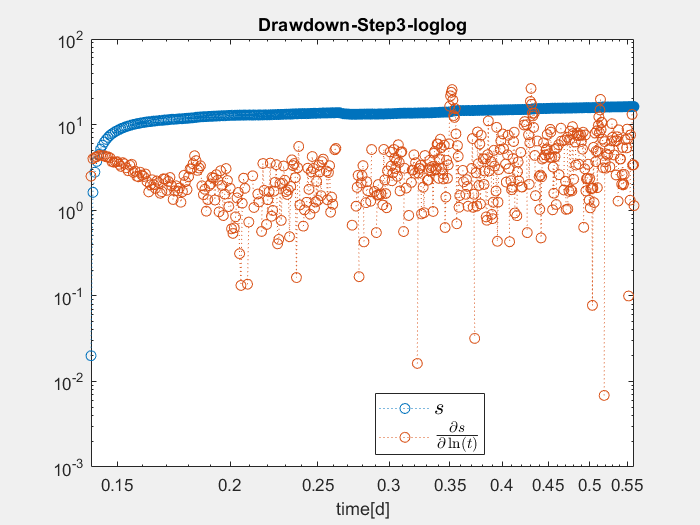


figure('Visible','on');
loglog(t_escalonada_pw(t_3_idx:end),s_escalonada_pw(t_3_idx:end)-s_escalonada_pw(t_3_idx),':o')
hold on
loglog(t_escalonada_pw(t_3_idx:end),num_der(t_escalonada_pw(t_1_idx:(t_1_idx+606)),s_escalonada_pw(t_3_idx:end)),':o')
title('Drawdown-Step3-loglog')
xlabel('time[d]')
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

The dimensional diagnostic plots show that the time between steps is very short, which limits stabilization. Moreover, the aquifer response appears slow: steady-state conditions are not reached quickly. The derivative plot confirms this behavior, with an initial increase, followed by oscillations and then a second rise, suggesting a complex flow regime. This pattern supports the previous hypothesis of an unconfined aquifer, that consistent with the high storativity value. Lastly we code the dimensionsless diagnostic plots.

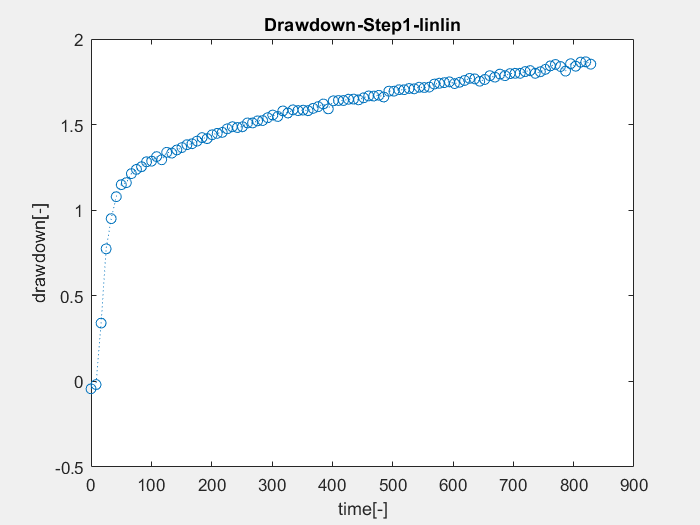

s_d=s_escalonada_pw;
s_d(t_1_idx:(t_2_idx-1))=s_d(t_1_idx:(t_2_idx-1))./(Q(1)./(2*pi*best_params_pw(1)));
s_d(t_2_idx:(t_3_idx-1))=s_d(t_2_idx:(t_3_idx-1))./(Q(2)./(2*pi*best_params_pw(1)));
s_d(t_3_idx:end)=s_d(t_3_idx:end)./(Q(3)./(2*pi*best_params_pw(1)));

t_d=t_escalonada_pw;
t_d(t_1_idx:(t_2_idx-1))=t_d(t_1_idx:(t_2_idx-1))./(r_pw^2.*best_params_pw(2)./best_params_pw(1));
t_d(t_2_idx:(t_3_idx-1))=t_d(t_2_idx:(t_3_idx-1))./(r_pw^2.*best_params_pw(2)./best_params_pw(1));
t_d(t_3_idx:end)=t_d(t_3_idx:end)./(r_pw^2.*best_params_pw(2)./best_params_pw(1));


figure('Visible','on');
plot(t_d(1:(t_2_idx-1)),s_d(1:(t_2_idx-1)),':o')
hold on
title('Drawdown-Step1-linlin')
xlabel('time[-]')
ylabel('drawdown[-]')

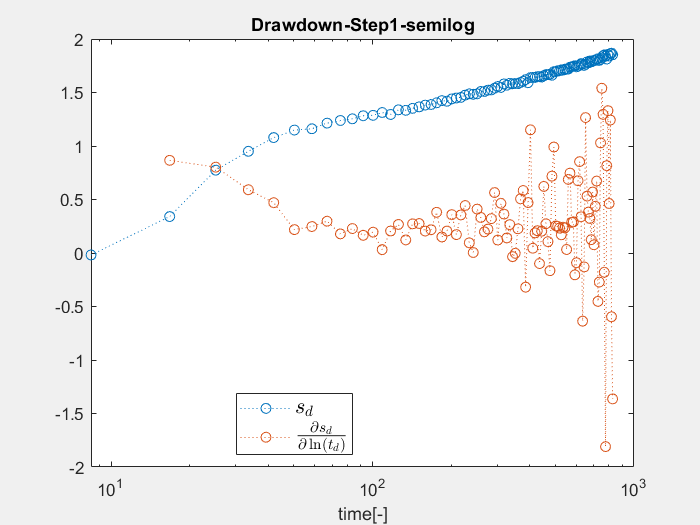


figure('Visible','on');
semilogx(t_d(1:(t_2_idx-1)),s_d(1:(t_2_idx-1)),':o')
hold on
semilogx(t_d(1:(t_2_idx-1)),num_der(t_d(1:(t_2_idx-1)),s_d(1:(t_2_idx-1))),':o')
title('Drawdown-Step1-semilog')
xlabel('time[-]')
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

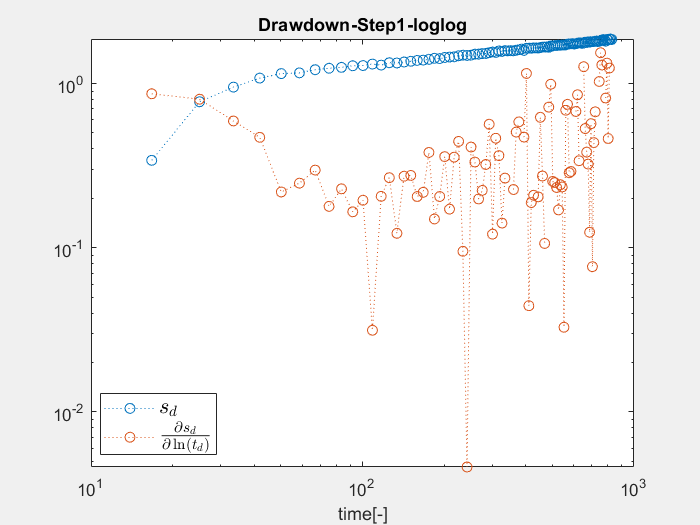


figure('Visible','on');
loglog(t_d(1:(t_2_idx-1)),s_d(1:(t_2_idx-1)),':o')
hold on
loglog(t_d(1:(t_2_idx-1)),num_der(t_d(1:(t_2_idx-1)),s_d(1:(t_2_idx-1))),':o')
title('Drawdown-Step1-loglog')
xlabel('time[-]')
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

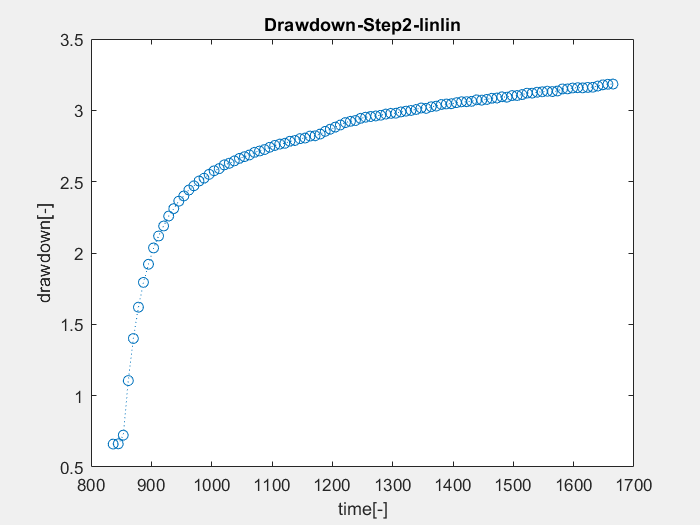


figure('Visible','on');
plot(t_d(t_2_idx:(t_3_idx-1)),s_d(t_2_idx:(t_3_idx-1)),':o')
title('Drawdown-Step2-linlin')
xlabel('time[-]')
ylabel('drawdown[-]')

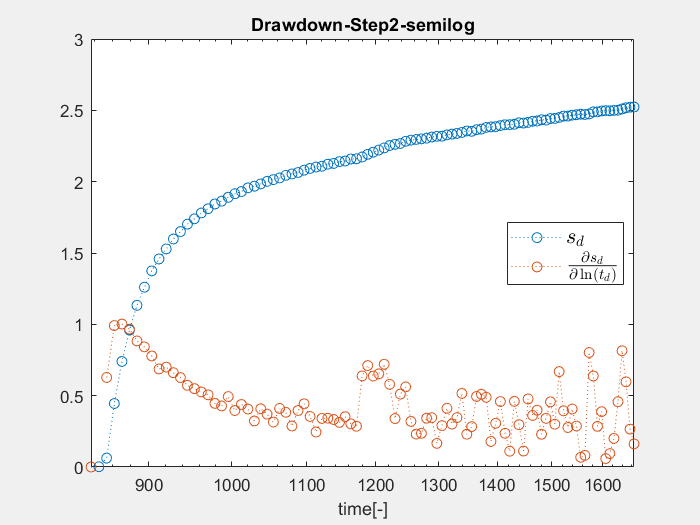


figure('Visible','on');
semilogx(t_d(t_2_idx:(t_3_idx-1)),s_d(t_2_idx:(t_3_idx-1))-s_d(t_2_idx),':o')
hold on
semilogx(t_d(t_2_idx:(t_3_idx-1)),num_der(t_d(t_1_idx:(t_2_idx-1)),s_d(t_2_idx:(t_3_idx-1))),':o')
title('Drawdown-Step2-semilog')
xlabel('time[-]')
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

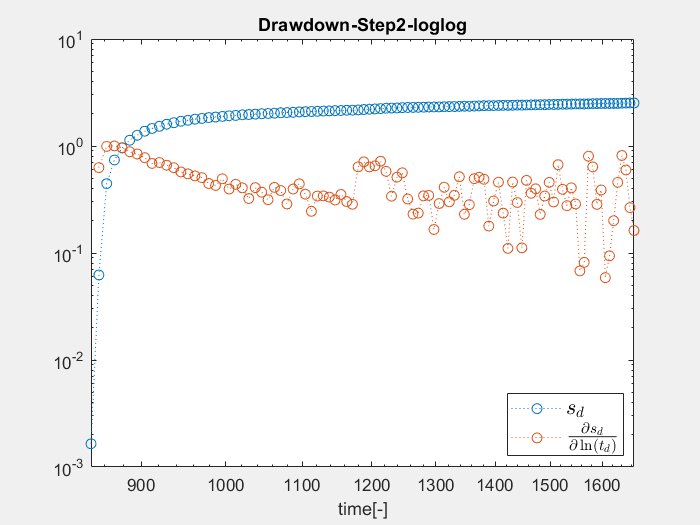


figure('Visible','on');
loglog(t_d(t_2_idx:(t_3_idx-1)),s_d(t_2_idx:(t_3_idx-1))-s_d(t_2_idx),':o')
hold on
loglog(t_d(t_2_idx:(t_3_idx-1)),num_der(t_d(t_1_idx:(t_2_idx-1)),s_d(t_2_idx:(t_3_idx-1))),':o')
title('Drawdown-Step2-loglog')
xlabel('time[-]')
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

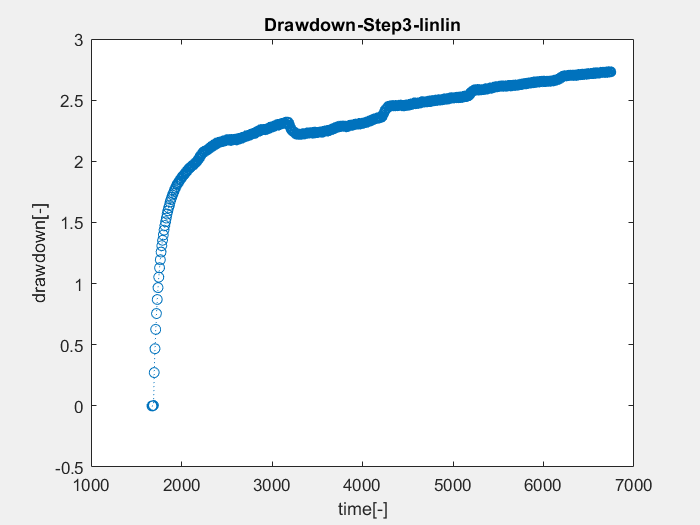



figure('Visible','on');
plot(t_d(t_3_idx:end),s_d(t_3_idx:end)-s_d(t_3_idx),':o')
title('Drawdown-Step3-linlin')
xlabel('time[-]')
ylabel('drawdown[-]')

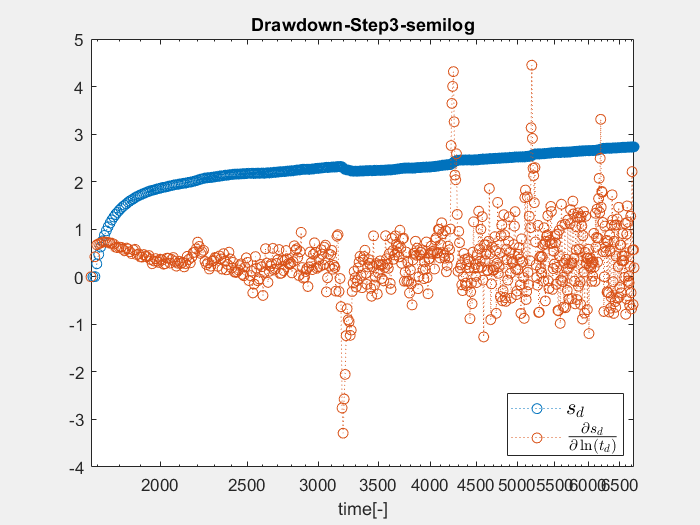


figure('Visible','on');
semilogx(t_d(t_3_idx:end),s_d(t_3_idx:end)-s_d(t_3_idx),':o')
hold on
semilogx(t_d(t_3_idx:end),num_der(t_d(t_1_idx:(t_1_idx+606)),s_d(t_3_idx:end)),':o')
title('Drawdown-Step3-semilog')
xlabel('time[-]')
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

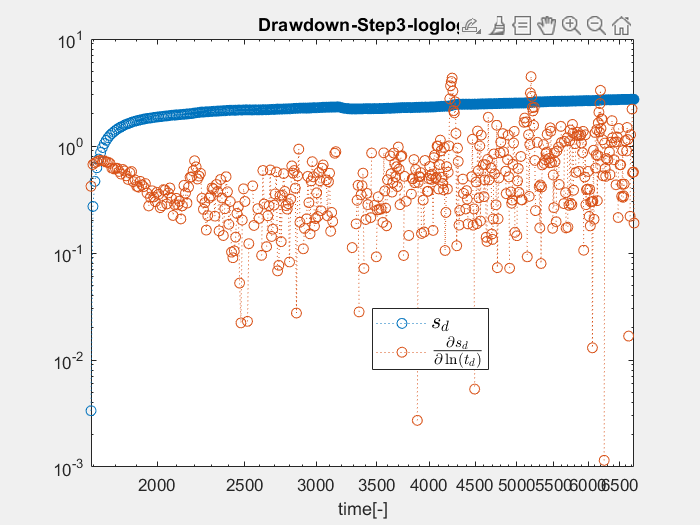


figure('Visible','on');
loglog(t_d(t_3_idx:end),s_d(t_3_idx:end)-s_d(t_3_idx),':o')
hold on
loglog(t_d(t_3_idx:end),num_der(t_d(t_1_idx:(t_1_idx+606)),s_d(t_3_idx:end)),':o')
title('Drawdown-Step3-loglog')
xlabel('time[-]')
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','best');

The dimensionsless diagnostic plots are in line with what was observed before. Comparing the three steps: Step 1 shows a slow drawdown response and a derivative that rises, oscillates, and rises again, indicating strong transient effects and incomplete stabilization. Step 2 is more regular but still far from steady-state, with derivative values remaining high. Step 3 approaches stabilization, yet oscillations persist, confirming that the aquifer responds slowly. These patterns, combined with the short time between steps and the high storage coefficient, support the interpretation of an unconfined aquifer. 

### `CONCLUSIONS for Exercise 3`

The analysis of the UNAL pumping test indicates that the aquifer transmissivity is best constrained by the observation well, yielding values of approximately $T = 12.3\text{–}12.7 \,\mathrm{m^2/d}$ from the pumping phase and $$T=11.4 \mathrm{m^2/d}$$ from the recovery phase, while the pumping-well estimates ($T \approx 5.0 \,\mathrm{m^2/d}$ in pumping and $T \approx 2.7 \,\mathrm{m^2/d}$ in recovery) are unreliable due to strong wellbore-storage and skin effects. The storativity consistently converges to $S \approx 0.06$, a value typical of an unconfined or weakly semiconfined aquifer, which also explains the slow stabilization observed in the diagnostic curves. No evidence of hydrologic boundaries emerged during the test duration, as neither well reached a clear late-time radial flow regime. The step-drawdown interpretation using the Hantush–Bierschenk method provides coefficients $B=0.0408$ and $C = 4.30 \times 10^{-4}$, indicating moderate aquifer losses and significant **nonlinear** well losses; consequently, the well efficiency decreases from roughly $69\%$ at $Q = 0.5\,\mathrm{L/s}$ to $44\%$ at $1.4\,\mathrm{L/s}$ and $33\%$ at $2.2\,\mathrm{L/s}$. Overall, the aquifer exhibits moderate transmissivity and high storativity consistent with unconfined behavior, whereas the pumping well is affected by substantial turbulence-related head losses, explaining the discrepancy between wells and the limited convergence of the dimensionless responses.

## Exercise 4 - Pumping tests at Puerto Wilches

Since the datasets for this exercise are really complex i plot all the data from the files to understand the different type of tests.

clearvars;


filename_1 = 'Wilches\POZO  2_WILCHES_2025-04-29_07_11_40.xlsx';
sheet_1 = 'Data';  

data_1 = readtable(filename_1, 'Sheet', sheet_1,  'VariableNamingRule', 'modify');

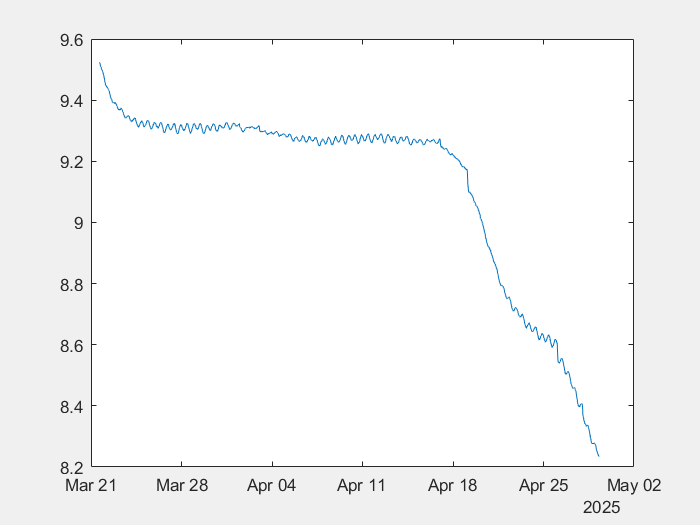

figure('Visible','on')
plot(data_1.Datetime_localTime_America_Bogota,data_1.mH20_F__m_);

filename_2='Wilches\Pozo 1 Wilches MEGIA_2025-03-07_12_03_50_Bombeo 7 Horas.xlsx';
data_2 = readtable(filename_2, 'Sheet', sheet_1,  'VariableNamingRule', 'modify');

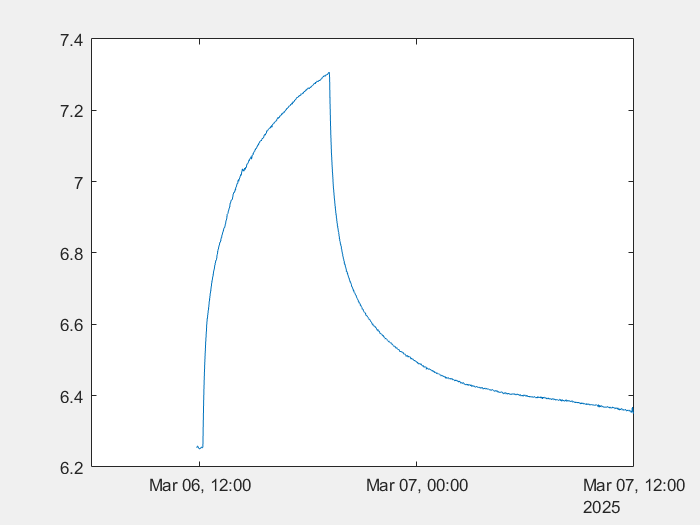

figure('Visible','on')
plot(data_2.Datetime_localTime_America_Bogota,data_2.mH20_F__m_);

filename_3='Wilches\Pozo 1 Wilches MEGIA_2025-04-29_07_43_11.xlsx';
data_3 = readtable(filename_3, 'Sheet', sheet_1,  'VariableNamingRule', 'modify');

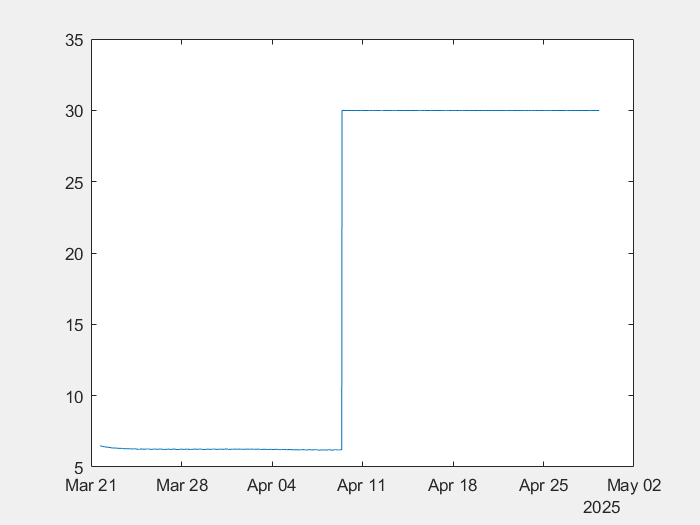

figure('Visible','on')
plot(data_3.Datetime_localTime_America_Bogota,data_3.mH20_F__m_);

filename_4='Wilches\Pozo Wilches MEGIA_2025-03-04_05_15_10.xlsx';
data_4 = readtable(filename_4, 'Sheet', sheet_1,  'VariableNamingRule', 'modify');

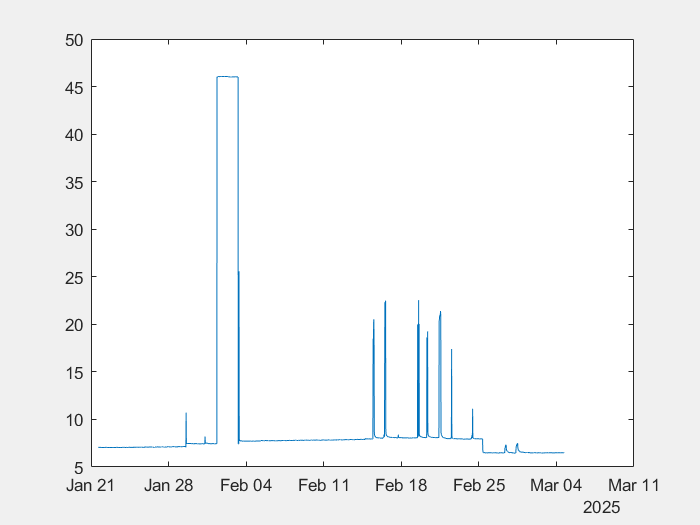

figure('Visible','on')
plot(data_4.Datetime_localTime_America_Bogota,data_4.mH20_F__m_);

filename_5='Wilches\Pozo_Pruebas.xlsx';
sheet='Hoja1';
data_5 = readtable(filename_5, 'Sheet', sheet,  'VariableNamingRule', 'modify');

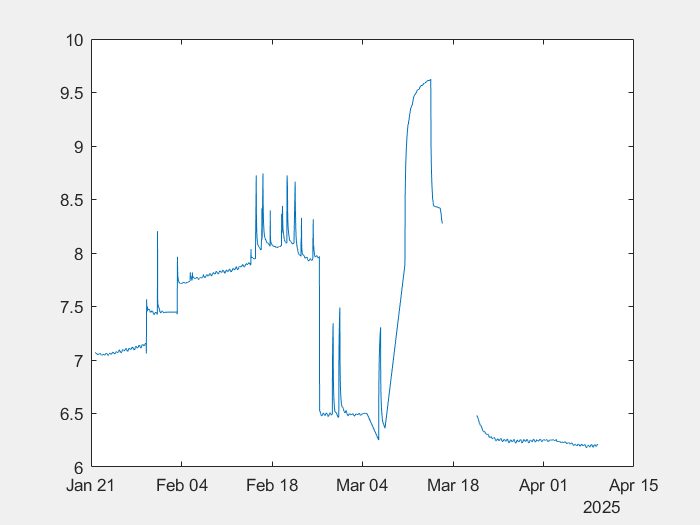

figure('Visible','on')
plot(data_5.localTime+data_5.hora,data_5.Nivel);

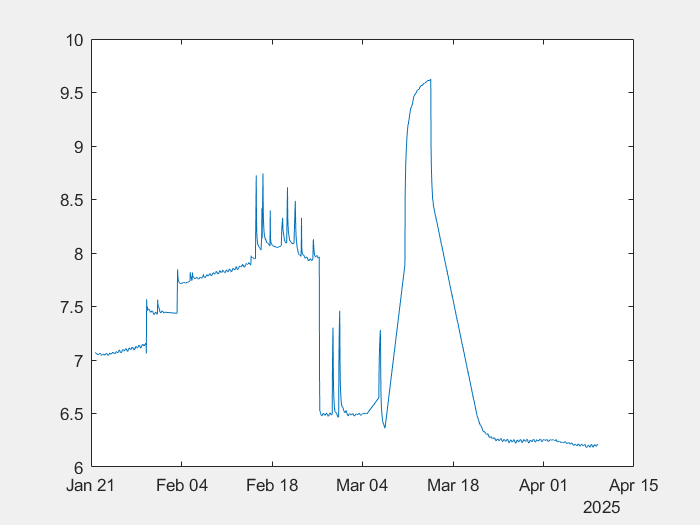

filename_6='Wilches\Pozo_Pruebas_filtrado.xlsx';
data_6 = readtable(filename_6, 'Sheet', sheet,  'VariableNamingRule', 'modify');
figure('Visible','on')
plot(data_6.Fecha+data_6.Hora,data_6.Nivel);

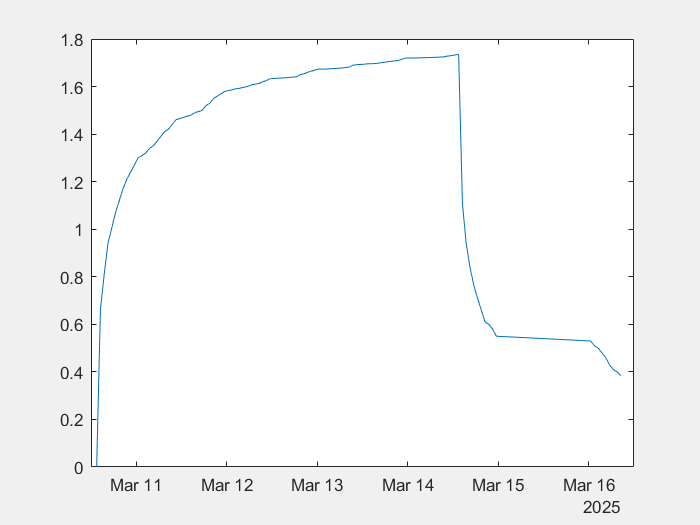

filename_7='Wilches\Prueba de bombeo.xlsx';
sheet_3 = 'OW Pozo Investigación Manual';
data_7 = readtable(filename_7, 'Sheet', sheet_3,  'VariableNamingRule', 'modify');
figure('Visible','on')
plot(data_7.Var1(7:end)+data_7.Var2(7:end),data_7.Var6(7:end));

It looks like the second and the seventh files are for the pumping test with recovery. The second is for the pumping well, while the seventh is for the observation well. We start by selecting the datas for the pumping and recovery.

s_p_pw_r = data_2.mH20_F__m_(442:end) - data_2.mH20_F__m_(21); %recovery data
s_p_pw = data_2.mH20_F__m_(21:441) - data_2.mH20_F__m_(21); %pumping data
t_p_pw = (data_2.No(21:441) - 20)./(24*60);%d
t_p_pw_r = (data_2.No(442:end) - 20)./(24*60) ;%d

s_p_ow = data_7.Var6(7:103); 
s_p_ow_r = data_7.Var6(104:end);
t_p_ow = (data_7.Var3(7:end)+1)./(24*60); %d
t_p_ow_r = t_p_ow(98:end);
t_p_ow = t_p_ow(1:97);

Q = data_7.Var6(2)/1000*24*60*60; %m^3/d

We start with the dimensional analysis for the pumping well.

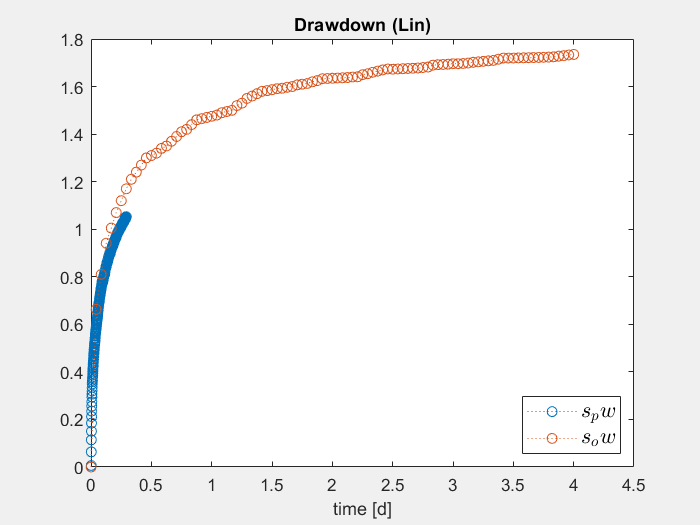

figure('Visible','on')
plot(t_p_pw,s_p_pw,':o')
hold on
plot(t_p_ow,s_p_ow,':o')
xlabel('time [d]');
title('Drawdown (Lin)');
legend({'$s_pw$', '$s_ow$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

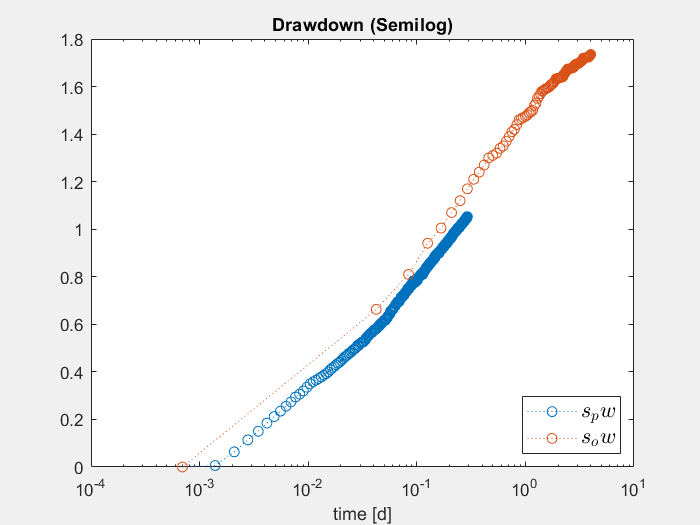

figure('Visible','on')
semilogx(t_p_pw,s_p_pw,':o')
hold on
semilogx(t_p_ow,s_p_ow,':o')
xlabel('time [d]');
title('Drawdown (Semilog)');
legend({'$s_pw$', '$s_ow$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

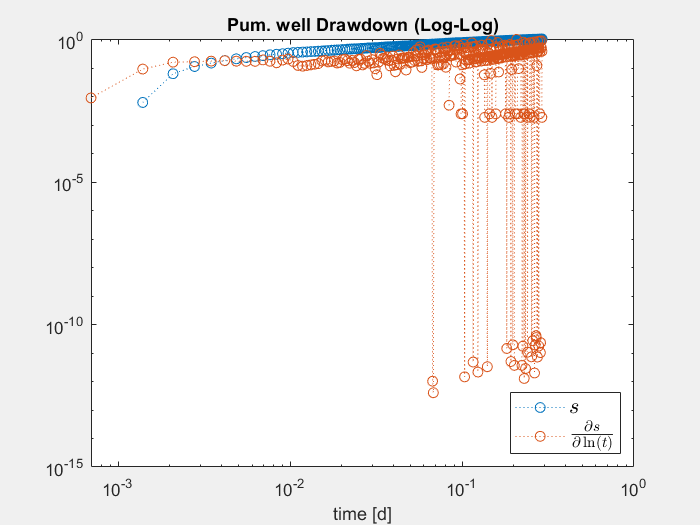

figure('Visible','on')
loglog(t_p_pw,s_p_pw,':o')
hold on
loglog(t_p_pw,num_der(t_p_pw,s_p_pw),':o')
xlabel('time [d]');
title('Pum. well Drawdown (Log-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

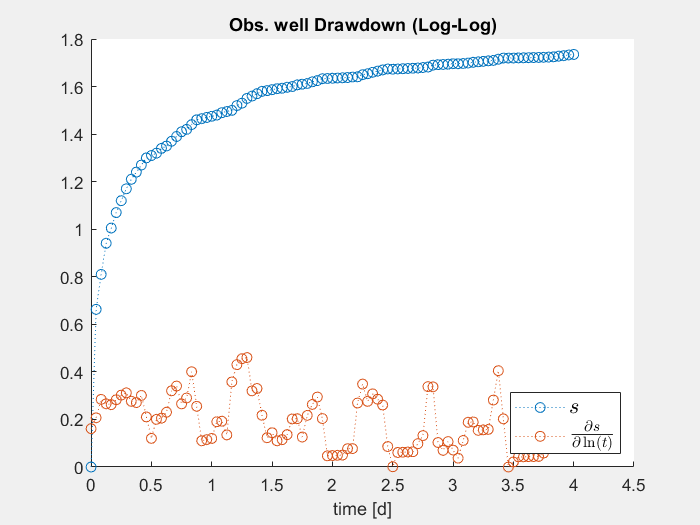


figure('Visible','on')
hold on
loglog(t_p_ow,s_p_ow,':o')
loglog(t_p_ow,num_der(t_p_ow,s_p_ow),':o')

xlabel('time [d]');
title('Obs. well Drawdown (Log-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

Pumping well is noisy as in the previous exercise, but this time the observation well, seems to show a solution that is not too far from Theis, with the derivative stabilizing to a constant value ( considering the obscillations). Let's try to fit  Cooper Jacob.

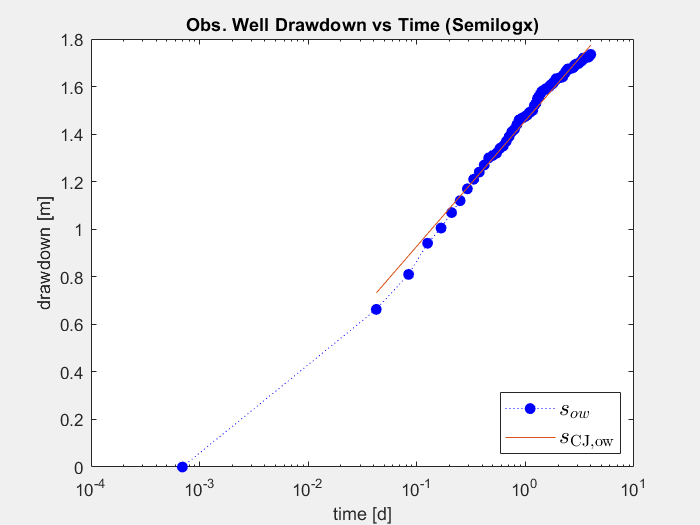

check=0;
t=1;
CJ_param_ow = zeros(1,2);
CJ_param_pw = zeros(1,2);
r_ow = data_7.Var8(1); %m
r_pw = 4; %''
r_pw = r_pw/39.37; %m 

while check == 0
G_ow = [log(t_p_ow(t:end)) ones(length(t_p_ow(t:end)),1)];
p_ow = (G_ow'*G_ow)\(G_ow'*s_p_ow(t:end));
CJ_param_ow(1) = Q/(4*pi*p_ow(1));
CJ_param_ow(2) = (2.25*CJ_param_ow(1)*exp(-p_ow(2)/p_ow(1))/r_ow^2);
if all(r_ow^2*CJ_param_ow(2)./(4*CJ_param_ow(1)*t_p_ow(t:end))<=0.1)
   check=1;
else t=t+1;
    
end
end
t_ow_start=t;

check=0;
t=1;

while check == 0
G_pw = [log(t_p_pw(t:end)) ones(length(t_p_pw(t:end)),1)];
p_pw = (G_pw'*G_pw)\(G_pw'*s_p_pw(t:end));
CJ_param_pw(1) = Q/(4*pi*p_pw(1));
CJ_param_pw(2) = (2.25*CJ_param_pw(1)*exp(-p_pw(2)/p_pw(1))/r_pw^2);
if all(r_pw^2*CJ_param_pw(2)./(4*CJ_param_pw(1)*t_p_pw(t:end))<=0.1)
   check=1;
else t=t+1;
    
end
end

t_pw_start=t;
figure('Visible','on');
semilogx(t_p_ow,s_p_ow,':ob','MarkerFaceColor','b');
hold on
semilogx(t_p_ow(t_ow_start:end),G_ow*p_ow) 
xlabel('time [d]');
ylabel('drawdown [m]');
title('Obs. Well Drawdown vs Time (Semilogx)');
legend({'$s_{ow}$','$s_{\mathrm{CJ, ow}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

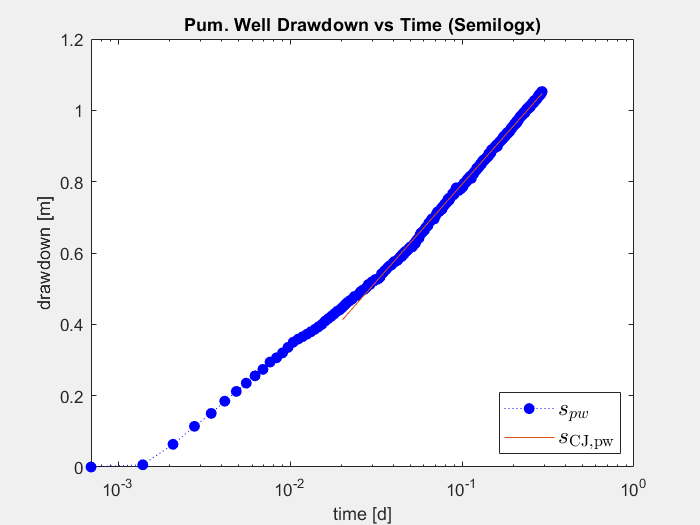

figure('Visible','on');
semilogx(t_p_pw,s_p_pw,':ob','MarkerFaceColor','b');
hold on
semilogx(t_p_pw(t_pw_start:end),G_pw*p_pw)
xlabel('time [d]');
ylabel('drawdown [m]');
title('Pum. Well Drawdown vs Time (Semilogx)');
legend({'$s_{pw}$','$s_{\mathrm{CJ, pw}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

The check for the suitability of CJ is overcomed by both datasets, the values of the Transmissivity are in accordance, we get: $T=666.7914 m^2/d$ for the observation well and $T=644.0888 m^2/d$ fort the pumping well, while for the storativity we obtain $S=5.7987 \times 10^{-4}$  for the observation well and a value that makes no sense for the pumping one, since the radius is near zero and the storativity explodes. Let's use the automatic fitting.

t_ow_r = t_p_ow(t_p_ow >= 10^-2); %we begin from where the derivative is more stable in log-log plot
s_ow_r = s_p_ow(t_p_ow >= 10^-2);

t_pw_r = t_p_pw(t_p_pw >= 10^-1.8); 
s_pw_r = s_p_pw(t_p_pw >= 10^-1.8);

iter =10000;
NS_g = -1000;


for j = 1:1:iter

S = 1E-7 + (1E-3+1E-3)*rand;

T = randi([1,2000],1,1);

W = expint(r_ow^2.*S./(4.*T.*t_ow_r));

s_sim = Q./4./pi()./T.*W;

NS_1 = s_sim-s_ow_r;

NS_2 = s_ow_r-mean(s_ow_r);


NS = 1 - sum(NS_1.^2)./sum(NS_2.^2);

if NS >= NS_g

Opt_ow = [T,S];

NS_g = 1 - sum((s_sim-s_ow_r).^2)./sum((s_ow_r-mean(s_ow_r)).^2);

end

end

iter =10000;
NS_g = -1000;


for j = 1:1:iter

S = 1E-7 + (1E-3+1E-3)*rand;

T = randi([1,2000],1,1);

W = expint(r_pw^2.*S./(4.*T.*t_pw_r));

s_sim = Q./4./pi()./T.*W;

NS_1 = s_sim-s_pw_r;

NS_2 = s_pw_r-mean(s_pw_r);


NS = 1 - sum(NS_1.^2)./sum(NS_2.^2);

if NS >= NS_g

Opt_pw = [T,S];

NS_g = 1 - sum((s_sim-s_pw_r).^2)./sum((s_pw_r-mean(s_pw_r)).^2);

end

end

%Residuals function
residuals_ow = @(p) abs(s_ow_r - theis_model(p, t_ow_r, Q, r_ow));
residuals_pw = @(p) abs(s_pw_r - theis_model(p, t_pw_r, Q, r_pw));

%options for the algorithm using Levenberg-Marquardt algorithm
options = optimoptions('lsqnonlin', 'Algorithm', 'levenberg-marquardt', ...
    'Display', 'iter', 'TolFun', 1e-12, 'TolX', 1e-12);

% Optimization
best_params_ow = lsqnonlin(residuals_ow, Opt_ow, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3        0.0652712             181         0.01
     1           6        0.0631517            1.96        0.001     0.00545651
     2           9        0.0631455        0.000939       0.0001      0.0542236
     3          12        0.0630938          0.0742        1e-05       0.497535
     4          15        0.0628951            2.14        1e-06        2.61821
     5          18        0.0628216            2.08        1e-07        2.57375
     6          21        0.0628207          0.0203        1e-08       0.249432
     7          24        0.0628207        1.08e-05        1e-09    0.000696563
     8          31        0.0628207        3.85e-08        1e-05    3.63403e-06

Local minimum possible.

lsqnonlin stopped becaus

best_params_pw = lsqnonlin(residuals_pw, Opt_pw, [], [], options);


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           3          89.4929        7.03e+03         0.01
     1           6          43.5991             677        0.001       0.118587
     2           9          18.9496            80.4       0.0001        1.18092
     3          12          8.57186            11.8        1e-05        11.7768
     4          15          6.14905             2.8        1e-06        115.755
     5          19          5.00223           0.855        1e-05        125.603
     6          22          4.34507           0.346        1e-06        137.176
     7          26           3.8422           0.179        1e-05        150.558
     8          29          3.39366           0.107        1e-06         165.09
     9          33          2.98537          0.0672        1e-05         177.67
    10          36            2.462          0.0398  

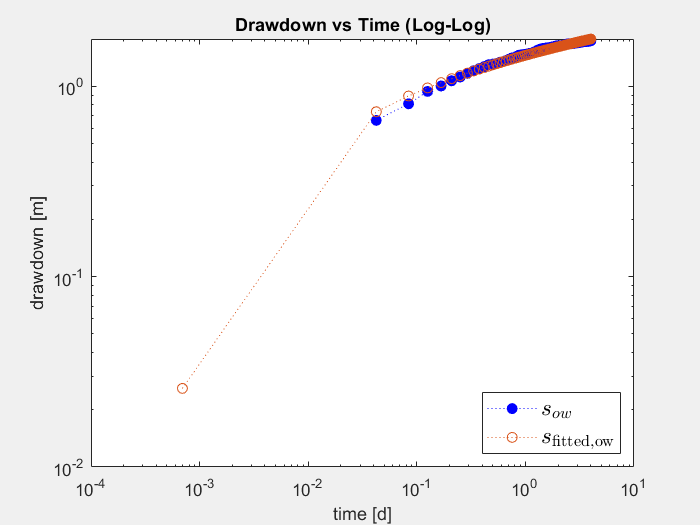


figure('Visible','on');
loglog(t_p_ow,s_p_ow,':ob','MarkerFaceColor','b');
hold on
loglog(t_p_ow, theis_model(best_params_ow,t_p_ow,Q,r_ow),':o')
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Log-Log)');
legend({'$s_{ow}$', '$s_{\mathrm{fitted, ow}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

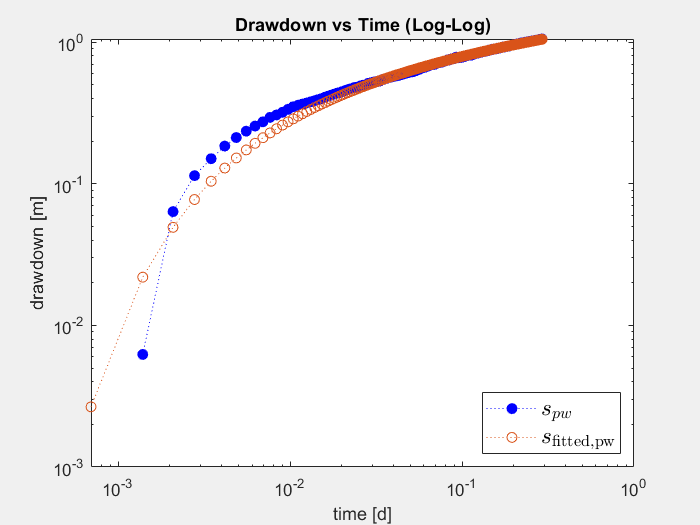

figure('Visible','on');
loglog(t_p_pw,s_p_pw,':ob','MarkerFaceColor','b');
hold on
loglog(t_p_pw, theis_model(best_params_pw,t_p_pw,Q,r_pw),':o')
xlabel('time [d]');
ylabel('drawdown [m]');
title('Drawdown vs Time (Log-Log)');
legend({'$s_{pw}$', '$s_{\mathrm{fitted, pw}}$'},'Interpreter', 'latex', 'FontSize', 14,'Location','southeast');

We obtaint $T=666.0007 m^3/d, S=5.8343\times10^{-4}[-]$ for the observation well and $T=632.3027m^2/d, S=532.7351[-]$  for the pumping well, that is consistent with the CJ values, of course we are not considering the value of storativity coming from the pumping well fitting for the above mentioned reasons. Now we move to dimensionsless analysis.

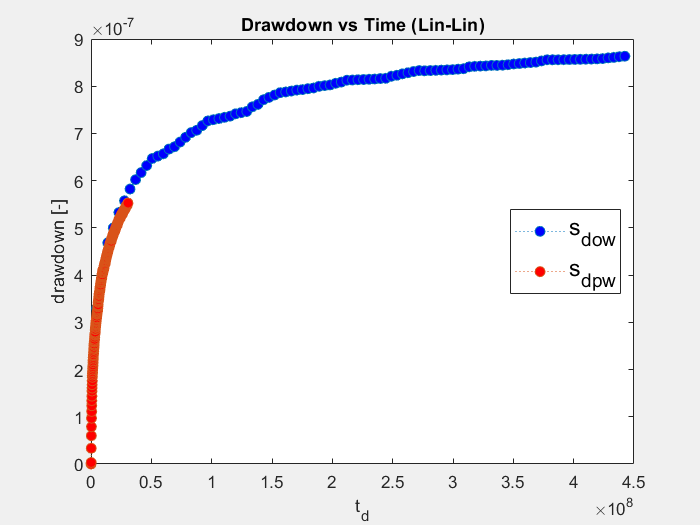

s_c_ow=Q/2*pi*best_params_ow(1);
r_c_ow=r_pw;
t_c_ow=r_c_ow^2*best_params_ow(2)/best_params_ow(1);
s_c_pw=Q/2*pi*best_params_pw(1);
r_c_pw=r_pw;
t_c_pw=r_c_pw^2*best_params_ow(2)/best_params_pw(1); %here we use the storativity from the ow
s_d_ow=s_p_ow/s_c_ow;
r_d_ow=r_ow/r_c_ow;
t_d_ow=t_p_ow/t_c_ow;
s_d_pw=s_p_pw/s_c_pw;
r_d_pw=r_pw/r_c_pw;
t_d_pw=t_p_pw/t_c_pw;

figure('Visible','on');
plot(t_d_ow,s_d_ow,':o','MarkerFaceColor','b');
hold on
plot(t_d_pw,s_d_pw,':o','MarkerFaceColor','r');
xlabel('t_d');
ylabel('drawdown [-]');
title('Drawdown vs Time (Lin-Lin)');
legend('s_d_{ow}','s_d_{pw}','FontSize', 14, 'Location', 'east');

drawnow;

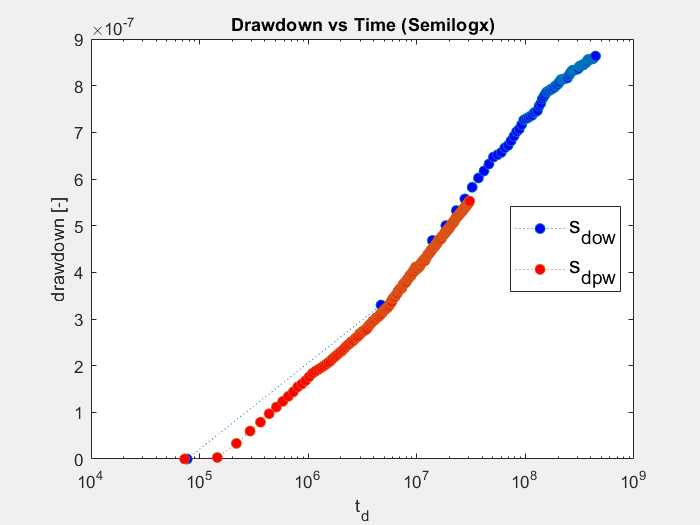


figure('Visible','on');
semilogx(t_d_ow,s_d_ow,':o','MarkerFaceColor','b');
hold on
semilogx(t_d_pw,s_d_pw,':o','MarkerFaceColor','r');
xlabel('t_d');
ylabel('drawdown [-]');
title('Drawdown vs Time (Semilogx)');
legend('s_d_{ow}','s_d_{pw}','FontSize', 14, 'Location', 'east');

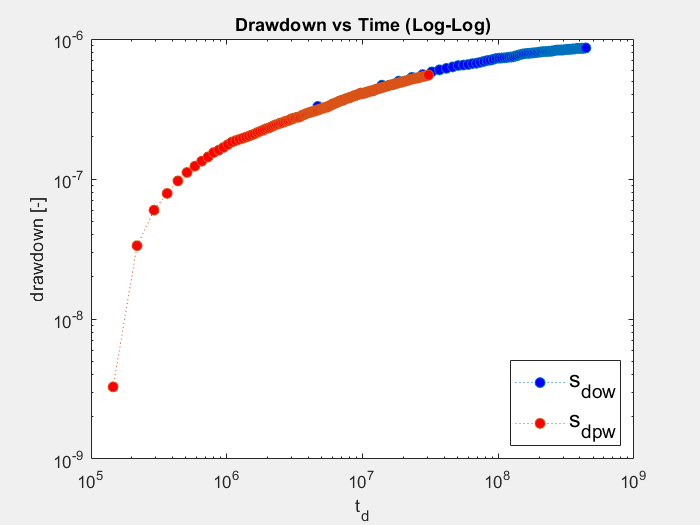

drawnow;

figure('Visible','on');
loglog(t_d_ow,s_d_ow,':o','MarkerFaceColor','b');
hold on
loglog(t_d_pw,s_d_pw,':o','MarkerFaceColor','r');
xlabel('t_d');
ylabel('drawdown [-]');
title('Drawdown vs Time (Log-Log)');
legend('s_d_{ow}','s_d_{pw}','FontSize', 14, 'Location', 'southeast');

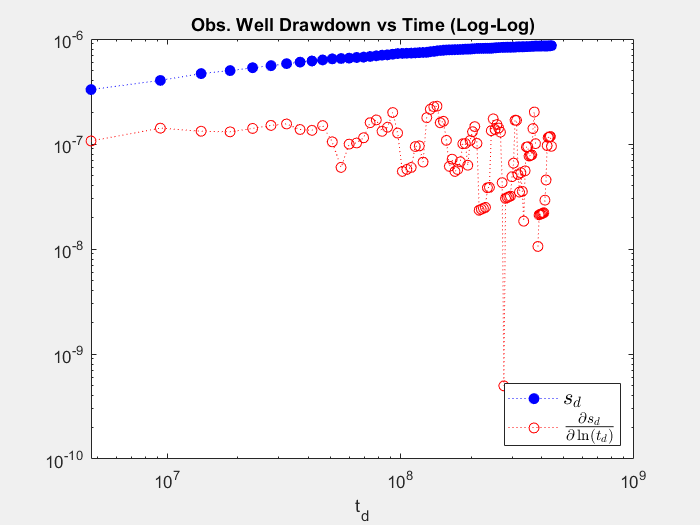

drawnow;
figure('Visible','on');
loglog(t_d_ow,s_d_ow,':ob','MarkerFaceColor','b');
hold on 
loglog(t_d_ow(2:end),num_der(t_d_ow(2:end),s_d_ow(2:end)),':or')
xlabel('t_d');
title('Obs. Well Drawdown vs Time (Log-Log)');
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

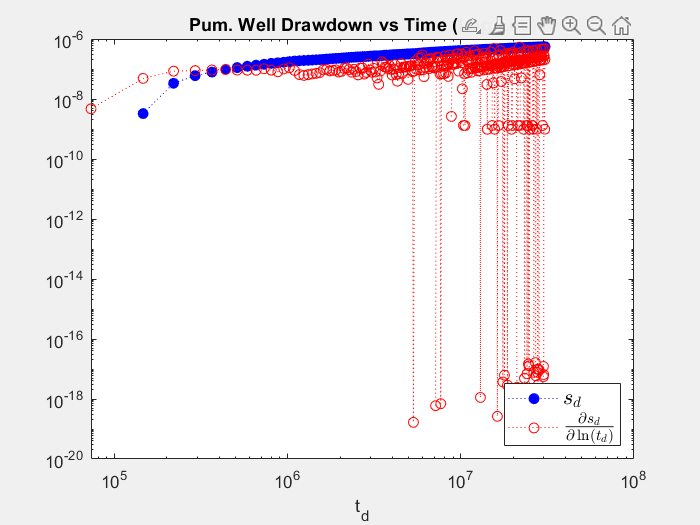


figure('Visible','on');
loglog(t_d_pw,s_d_pw,':ob','MarkerFaceColor','b');
hold on 
loglog(t_d_pw,num_der(t_d_pw,s_d_pw),':or')
xlabel('t_d');
title('Pum. Well Drawdown vs Time (Log-Log)');
legend({'$s_d$', '$\frac{\partial s_d}{\partial \ln(t_d)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

In the observation well, the log-derivative does not display the ideal constant plateau expected in a perfect Theis solution, suggesting that the radial flow regime is not fully established or is influenced by boundary conditions or heterogeneity. In contrast, the pumping well shows an initial  increase in the log-derivative, that could indicate wellbore storage effects before transitioning to radial flow. Despite these diagnostic deviations, both wells clearly represent the same aquifer response and follow the theoretical Theis behavior overall. Let's now move to the recovery test.

figure('Visible','on');

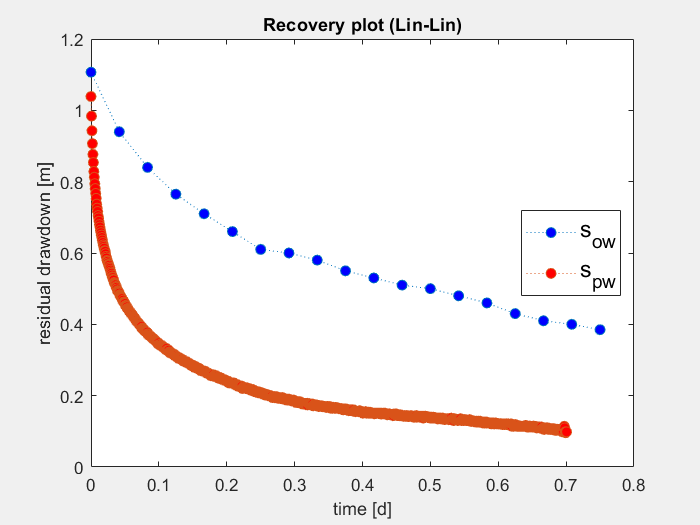

t_p_ow_r=t_p_ow_r-t_p_ow_r(1);
t_p_pw_r=t_p_pw_r-t_p_pw_r(1);
plot(t_p_ow_r,s_p_ow_r,':o','MarkerFaceColor','b');
hold on
plot(t_p_pw_r,s_p_pw_r,':o','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('residual drawdown [m]');
title('Recovery plot (Lin-Lin)');
legend('s_{ow}','s_{pw}','FontSize', 14, 'Location', 'east');

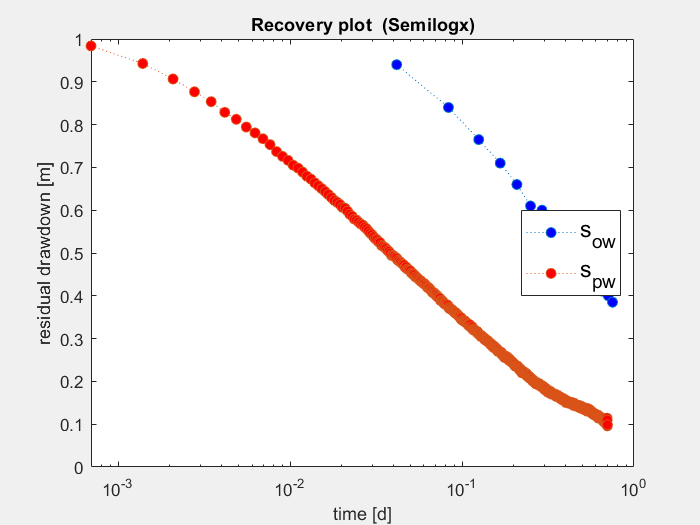

drawnow;

figure('Visible','on');
semilogx(t_p_ow_r,s_p_ow_r,':o','MarkerFaceColor','b');
hold on
semilogx(t_p_pw_r,s_p_pw_r,':o','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('residual drawdown [m]');
title('Recovery plot  (Semilogx)');
legend('s_{ow}','s_{pw}','FontSize', 14, 'Location', 'east');

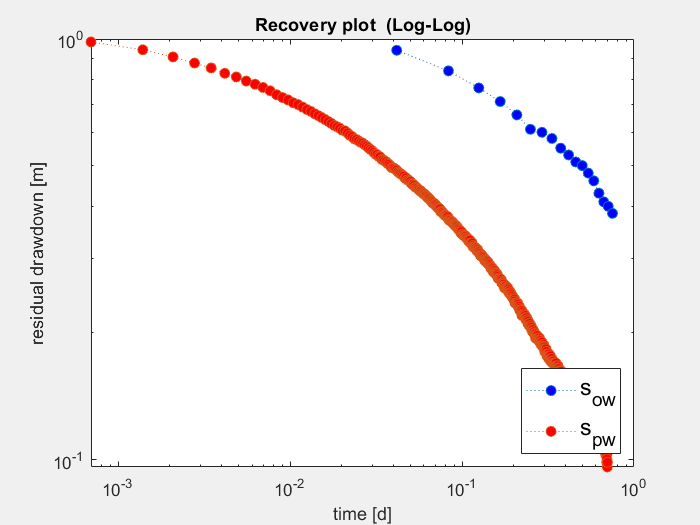

drawnow;

figure('Visible','on');
loglog(t_p_ow_r,s_p_ow_r,':o','MarkerFaceColor','b');
hold on
loglog(t_p_pw_r,s_p_pw_r,':o','MarkerFaceColor','r');
xlabel('time [d]');
ylabel('residual drawdown [m]');
title('Recovery plot  (Log-Log)');
legend('s_{ow}','s_{pw}','FontSize', 14, 'Location', 'southeast');

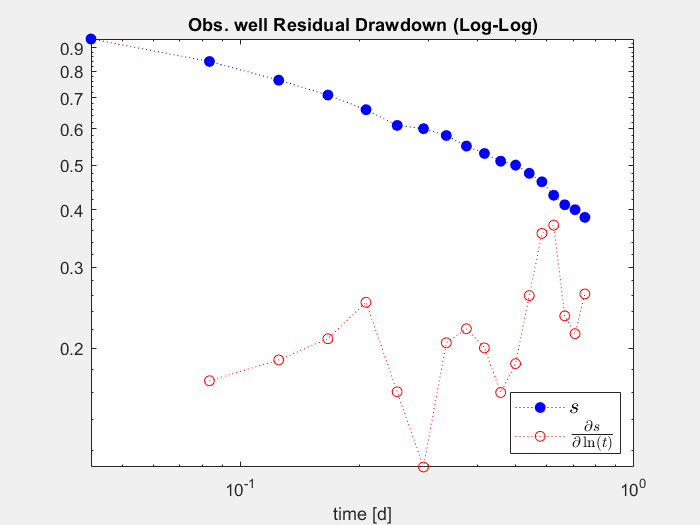

figure('Visible','on');
loglog(t_p_ow_r,s_p_ow_r,':ob','MarkerFaceColor','b');
hold on 
loglog(t_p_ow_r,abs(num_der(t_p_ow_r,s_p_ow_r)),':or'); %abs because is decreasing and we are in loglog scale
xlabel('time [d]');
title('Obs. well Residual Drawdown (Log-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

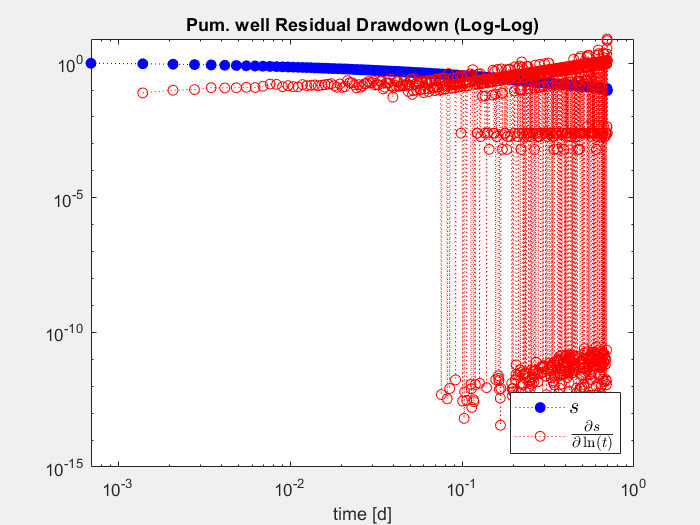

figure('Visible','on');
loglog(t_p_pw_r,s_p_pw_r,':ob','MarkerFaceColor','b');
hold on 
loglog(t_p_pw_r,abs(num_der(t_p_pw_r,s_p_pw_r)),':or'); %abs because is decreasing and we are in loglog scale
xlabel('time [d]');
title('Pum. well Residual Drawdown (Log-Log)');
legend({'$s$', '$\frac{\partial s}{\partial \ln(t)}$'},'Interpreter', 'latex', 'FontSize', 13,'Location','southeast');

The residual drawdown curves (blue) in both pumping and observation wells show the expected decreasing trend over time on a log-log scale. The diagnostic derivative (red) was plotted using its absolute value to avoid issues with negative signs in logarithmic representation. However, the derivative appears noisy at late times, likely due to very small residual drawdown values approaching zero, which amplifies numerical instability.We notice that we have very few data for the observation well and thederivative is more stable but because the drawdown is not approaching zero. Let's try to fit with the proposed solution;

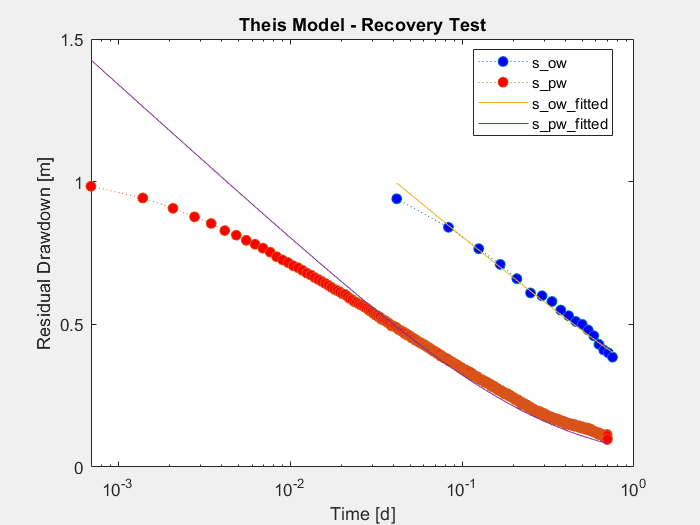

t_end=length(t_p_ow_r);
tpw=t_p_pw(end);
tow=t_p_ow(end);
t=2;
G_ow_rec = [log10((tow+t_p_ow_r(t:t_end))./t_p_ow_r(t:t_end))];
p_ow_rec = (G_ow_rec'*G_ow_rec)\(G_ow_rec'*s_p_ow_r(t:t_end));
CJ_param_ow_rec = 2.3 * Q/(4*pi*p_ow_rec);

t=2;
t_end=length(t_p_pw_r);

G_pw_rec = [log10((tpw+t_p_pw_r(t:t_end))./t_p_pw_r(t:t_end))];
p_pw_rec = (G_pw_rec'*G_pw_rec)\(G_pw_rec'*s_p_pw_r(t:t_end));
CJ_param_pw_rec = 2.3 * Q/(4*pi*p_pw_rec);

figure('Visible','on');
semilogx(t_p_ow_r,s_p_ow_r,':o','MarkerFaceColor','b');
hold on
semilogx(t_p_pw_r,s_p_pw_r,':o','MarkerFaceColor','r');


semilogx(t_p_ow_r,(2.3*Q)./(4*pi*CJ_param_ow_rec).*log10((tow+t_p_ow_r)./t_p_ow_r))
semilogx(t_p_pw_r,(2.3*Q)./(4*pi*CJ_param_pw_rec).*log10((tpw+t_p_pw_r)./t_p_pw_r))

title('Theis Model - Recovery Test');
xlabel('Time [d]');
ylabel('Residual Drawdown [m]');
legend({'s\_ow', 's\_pw', 's\_ow\_fitted', 's\_pw\_fitted'}, ...
       'Location', 'best');

The fit for the observation and pumping well works this time and provide a transmissivity value consistent with previous pumping analysis: $T=647.0466m^2/d $ for the pumping well and  $T=701.9274m^2/d $ for the observation well, both conisten with the previous one, the increase is of the order of 5% for the pumping well.

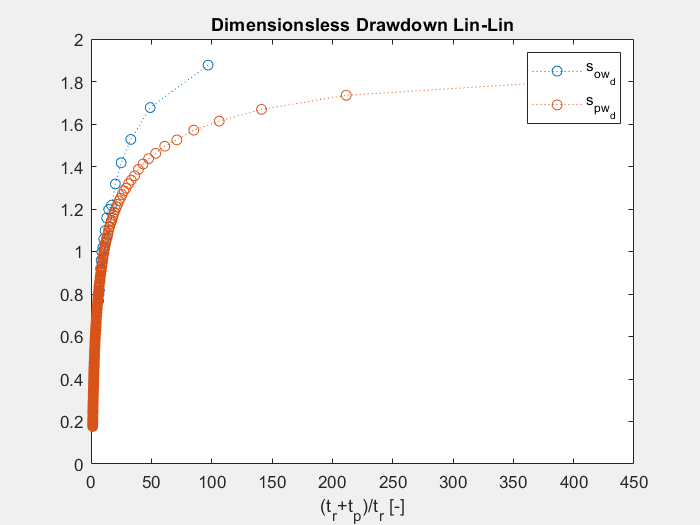

s_ow_rec_dless=s_p_ow_r./(2.3*Q/(4*pi*CJ_param_ow_rec));
s_pw_rec_dless=s_p_pw_r./(2.3*Q/(4*pi*CJ_param_pw_rec));
figure('Visible','on');
plot((t_p_ow_r(2:end)+tow)./t_p_ow_r(2:end),s_ow_rec_dless(2:end),':o')
hold on
plot((t_p_pw_r(2:end)+tpw)./t_p_pw_r(2:end),s_pw_rec_dless(2:end),':o')
xlabel("(t_r+t_p)/t_r [-]")
legend('s_{ow_d}','s_{pw_d}')
title("Dimensionsless Drawdown Lin-Lin")

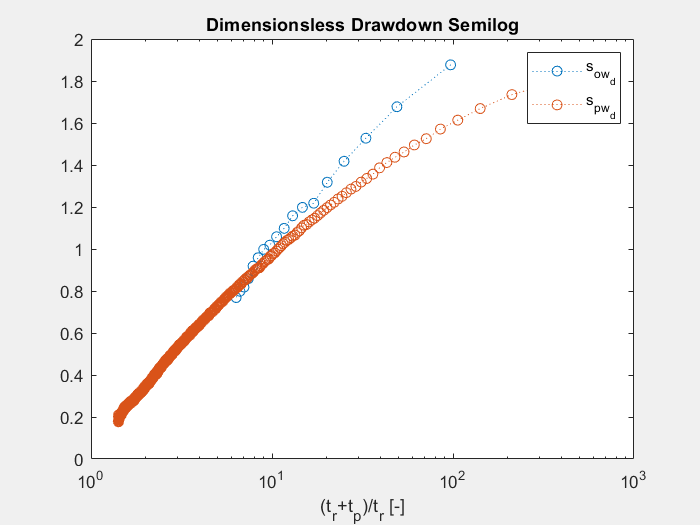


figure('Visible','on');
semilogx((t_p_ow_r(2:end)+tow)./t_p_ow_r(2:end),s_ow_rec_dless(2:end),':o')
hold on
semilogx((t_p_pw_r(2:end)+tpw)./t_p_pw_r(2:end),s_pw_rec_dless(2:end),':o')
xlabel("(t_r+t_p)/t_r [-]")
legend('s_{ow_d}','s_{pw_d}')
title("Dimensionsless Drawdown Semilog")


figure('Visible','on');
loglog((t_p_ow_r(2:end)+tow)./t_p_ow_r(2:end),s_ow_rec_dless(2:end),':o')
hold on
loglog((t_p_pw_r(2:end)+tpw)./t_p_pw_r(2:end),s_pw_rec_dless(2:end),':o')
xlabel("(t_r+t_p)/t_r [-]")
legend('s_{ow_d}','ds_ow_{dln_{t_d}}','s_{pw_d}','ds_pw_{dln_{t_d}}')

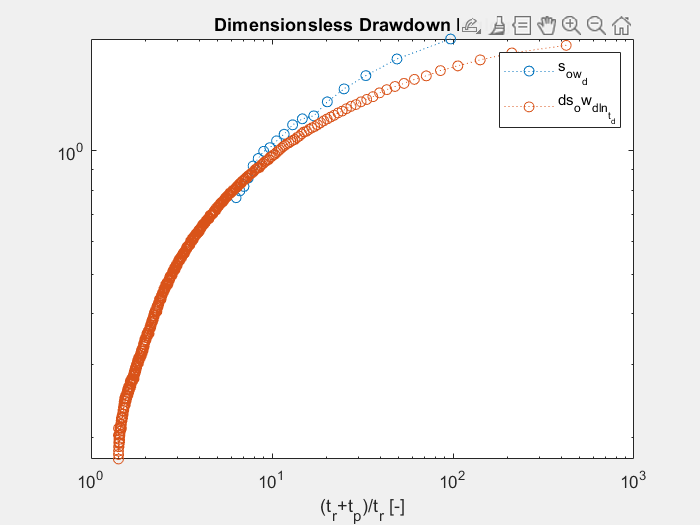

title("Dimensionsless Drawdown loglog")

Dimensionless analysis shows that pumping and observation wells behave similarly, confirming consistent aquifer response. However, the transmissivity estimated at the observation well is higher than at the pumping well because observation data are less affected by wellbore storage and skin effects, providing a clearer representation of radial flow conditions. Another simple reason could be the fact that we have very few data and that we don't arrive to drawdown zero in the observation well so maybe the slope could have decreased by letting the test continue. Finally we analize well performance and evaluate efficiency with the step drawdown test.

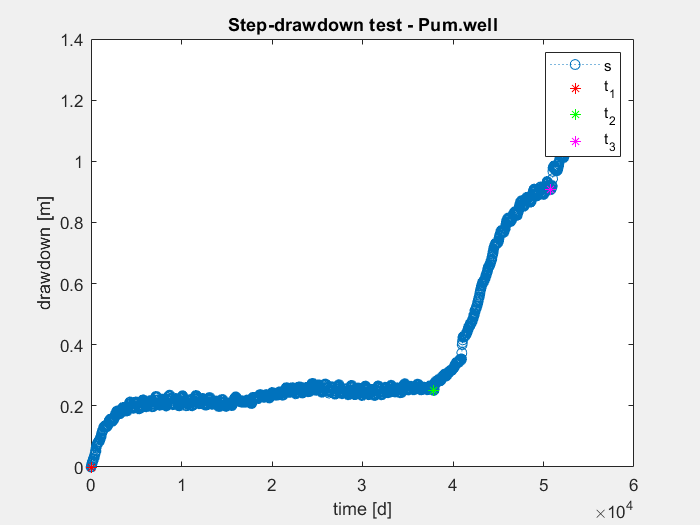

s_escalonada_pw=data_1.mH20_F__m_(1)-data_1.mH20_F__m_;
t_escalonada_pw=1:30:(1+30*1854);
t_1 = t_escalonada_pw(1);   
t_2 = 37890;  
t_3 = 50820; 
t_1_idx=1;
t_2_idx=1264;
t_3_idx=1695;

figure('Visible','on');
plot(t_escalonada_pw,s_escalonada_pw,':o')
hold on
plot(t_1,s_escalonada_pw(t_1_idx),'r*')
plot(t_2,s_escalonada_pw(t_2_idx),'g*')
plot(t_3,s_escalonada_pw(t_3_idx),'m*')
xlabel('time [d]')
ylabel('drawdown [m]')
title('Step-drawdown test - Pum.well')
legend('s','t_1','t_2','t_3')

So let's see what happens using the Hantush-Bierschenk's method.First we plot the observed drawdown in the well versus the time in semilog scale and fit the curves.

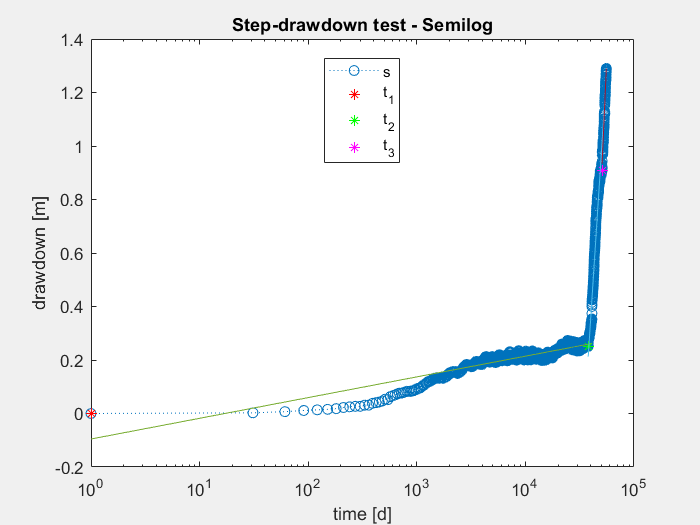

figure('Visible','on');
semilogx(t_escalonada_pw,s_escalonada_pw,':o')
hold on
semilogx(1  ,s_escalonada_pw(t_1_idx),'r*')
semilogx(t_2,s_escalonada_pw(t_2_idx),'g*')
semilogx(t_3,s_escalonada_pw(t_3_idx),'m*')
xlabel('time [d]')
ylabel('drawdown [m]')
title('Step-drawdown test - Semilog')
legend('s','t_1','t_2','t_3','Location','best')
step1 = polyfit(log10(t_escalonada_pw(50:(t_2_idx-1))), s_escalonada_pw(50:(t_2_idx-1)), 1);
step2 = polyfit(log10(t_escalonada_pw((t_2_idx+50):(t_3_idx-1))), s_escalonada_pw((t_2_idx+50):(t_3_idx-1)), 1);
step3 = polyfit(log10(t_escalonada_pw((t_3_idx+100):end)), s_escalonada_pw((t_3_idx+100):end), 1);
hold on
semilogx(t_escalonada_pw(1:(t_2_idx+100)),step1(1)*log10(t_escalonada_pw(1:(t_2_idx+100)))+step1(2),'HandleVisibility', 'off')
semilogx(t_escalonada_pw(t_2_idx:(t_3_idx+100)),step2(1)*log10(t_escalonada_pw(t_2_idx:(t_3_idx+100)))+step2(2),'HandleVisibility', 'off')
semilogx(t_escalonada_pw(t_3_idx:end),step3(1)*log10(t_escalonada_pw(t_3_idx:end))+step3(2),'HandleVisibility', 'off')

Now we compute the Δsw(i) for each step by taking the difference between the observed drawdown at a fixed time interval Δt, taken from the beginning of each step, and the corresponding drawdown on the extrapolated curve of the preceding step.

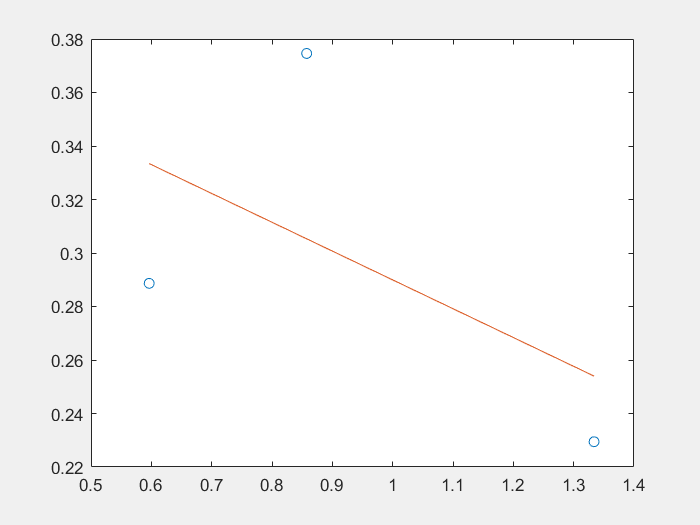

t=95; %min
ds1=step1(1)*log10(t_escalonada_pw(t+t_1_idx))+step1(2);
ds2=step2(1)*log10(t_escalonada_pw(t+t_2_idx))+step2(2) - step1(1)*log10(t_escalonada_pw(t+t_2_idx)) - step1(2);
ds3=step3(1)*log10(t_escalonada_pw(t+t_3_idx))+step3(2) - step2(1)*log10(t_escalonada_pw(t+t_3_idx)) - step2(2);

s_w_1 = ds1;
s_w_2 = ds1 + ds2;
s_w_3 = ds1 + ds2 + ds3;

y = [s_w_1 s_w_2 s_w_3];
Q = [9.94/1000*60,14.29/1000*60,22.23/1000*60];

fit = polyfit(Q,y./Q,1);

figure('Visible','on');
plot(Q,y./Q,'o')
hold on
plot(Q,fit(1)*Q+fit(2))

The third step is too small, let's try with the first two only:

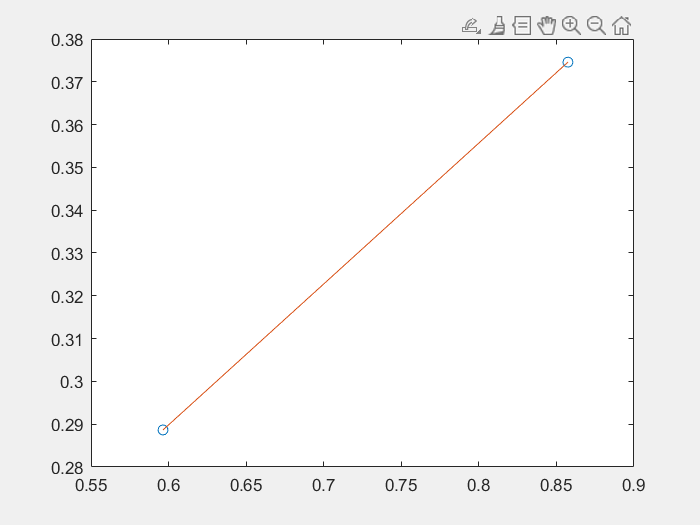

fit = polyfit(Q(1:2),y(1:2)./Q(1:2),1);

figure('Visible','on');
plot(Q(1:2),y(1:2)./Q(1:2),'o')
hold on
plot(Q(1:2),fit(1)*Q(1:2)+fit(2))

C_new=fit(1);
B_new=fit(2);
eff = B_new./(B_new+C_new*Q(1:2))*100;

The three-point Hantush-Bierschenk plot does not align on a straight line, indicating significant non-linearities and suggesting that well losses are not constant across pumping steps. Using two points, the calculated coefficients (B = 0.09, C = 0.329) and low efficiencies (≈32% and 25%) confirm substantial well losses, likely due to variable turbulence and skin effects.

#### Conclusion

The pumping and recovery tests at Puerto Wilches indicate that the aquifer behaves predominantly as a confined to semi-confined system following Theis-type radial flow. Transmissivity obtained from the observation well ranges between **800 and 900 m²/d**, while the pumping well yields slightly lower values, around **700–850 m²/d**, due to wellbore storage and skin effects that bias early-time data; recovery tests provide transmissivities approximately **5% higher**, confirming the robustness of the estimates. Storativity derived from the observation well is consistent with confined conditions, approximately 5**×10⁻⁴**, whereas the pumping-well storativity is unreliable because the very small effective radius causes Cooper–Jacob estimates to diverge. Diagnostic plots show that the pumping well probably experiences early-time wellbore storage and skin, while the observation well presents a clearer radial-flow regime, with only minor oscillations in the log-derivative that suggest moderate heterogeneity but no significant boundary effects. Step-drawdown analysis yields a linear well-loss coefficient **B ≈ 0.09 ** and a non-linear coefficient **C ≈ 0.33**, resulting in well efficiencies of only **25–32%**, which reflects substantial turbulent and skin-related losses and indicates that the pumping well is hydraulically inefficient. Overall, the most reliable hydraulic parameters for the aquifer are a transmissivity of about **800 ± 80 m²/d** and a storativity of **~5×10⁻⁴**, while well performance is limited by significant non-linear losses.

# General Conclusions

The four pumping-test scenarios examined in this notebook collectively illustrate the progressive transition from theoretical textbook conditions to the much more complex hydraulic behavior encountered in real aquifer systems. In the first scenario, based on an ideal confined aquifer example, the estimates of transmissivity and storativity obtained through dimensional and dimensionless Theis fitting were nearly identical, and the Cooper–Jacob approximation produced values only marginally different, with transmissivity about seven percent higher and storativity about sixteen percent lower, fully consistent with its role as a late-time simplification. The diagnostic curves for this case showed an early stabilization of the derivative without any signature of wellbore storage, turbulence, or boundary effects, and the match with the classical confined-aquifer type curves was almost perfect. This initial case therefore served as a benchmark, demonstrating how a system behaves when all assumptions of the Theis model are satisfied and when field distortions are absent.

The second scenario already departs from this ideal behavior even though the differences are subtle. Here transmissivity remained remarkably stable across both piezometers and across Theis and Cooper–Jacob methods, with values between roughly 575 and 599 m²/d, suggesting that the aquifer is reasonably homogeneous. However, storativity varied substantially, with values on the order of 10⁻⁵ for the piezometer at 30 m and roughly five times higher at 90 m. This divergence reflects the increasing influence of near-well effects at the closer piezometer, where wellbore storage and potential skin distort the early-time response and suppress the accuracy of S. The diagnostic curves confirm this interpretation: at 30 m the derivative initially rises along the drawdown curve before settling, while at 90 m the transition to radial flow is much cleaner. When both datasets are merged into a dimensionless late-time interpretation, transmissivity decreases to approximately 426 m²/d, a value likely more representative of the bulk aquifer, while storativity increases to around 2.7×10⁻⁴, suggesting that the model compensates for the discrepancies between datasets. The slight downward deviation of the latest points in the dimensionless curve hints at leakage or weak boundaries not captured by the idealized assumptions. This second scenario thus demonstrates that even when data appear clean and transmissivity is well constrained, storativity is often sensitive to early-time distortions and that diagnostic curves are essential for distinguishing between aquifer properties and artifacts of the measurement environment.

The third scenario, based on the UNAL pumping test, shows an even stronger departure from theoretical behavior. Transmissivity is again more reliably constrained by the observation well, with values consistent between pumping and recovery phases, while the pumping well produces lower and more unstable estimates due to strong wellbore-storage and skin effects. Storativity converges in the order of $10^{-2$, a value more typical of unconfined or weakly semiconfined systems, which is also reflected in the slow stabilization of the diagnostic curves and the absence of a clean late-time radial flow regime. No clear evidence of boundaries emerges, but neither well reaches a stable derivative plateau, emphasizing how unconfined dynamics, delayed yield, and near-well distortions complicate traditional confined-aquifer analysis. The step-drawdown test with the Hantush–Bierschenk method further highlights the non-ideal behavior: the linear well-loss coefficient B and nonlinear coefficient C indicate significant turbulence and substantial energy dissipation near the well, which in turn reduce well efficiency from roughly 70% at low discharge to below 30% at higher rates. This scenario therefore demonstrates how real aquifers often exhibit mixed confined–unconfined behavior, delayed drainage, strong well effects, and nonlinear losses that fall outside the simplifying assumptions of both Theis and Cooper–Jacob.

The fourth scenario, corresponding to the Puerto Wilches field data, represents the culmination of this progression toward complexity. Transmissivity values from the observation well cluster around 800–900 m²/d, while the pumping-well estimates remain slightly lower, around 700–850 m²/d, again showing the influence of wellbore storage and skin. Recovery tests yield transmissivities about five percent higher, consistent with the principle that recovery is less sensitive to wellbore distortion. Storativity from the observation well centers near 10⁻⁴, whereas the pumping-well storativity is unreliable for the same reasons observed previously. Diagnostic curves show pronounced early-time storage effects in the pumping well and a clearer radial regime in the observation well, yet with small oscillations that indicate moderate heterogeneity. No boundaries are identified, suggesting a laterally extensive aquifer, but the step-drawdown test reveals strong nonlinear losses with B≈0.09 and C≈0.33, leading to well efficiencies of only 25–32%, much lower than in the previous exercises. The combination of turbulence, clogging, partial penetration, and stratification typical of fluvial deposits results in responses far more irregular than those in the theoretical case.

Taken together, the four scenarios reveal the critical importance of recognizing that real aquifers rarely behave like the ideal systems described in textbooks. The progression from the perfectly confined, homogeneous system of Scenario 1 to the increasingly distorted, nonlinear, stratified, and unconfined systems of Scenarios 3 and 4 shows that transmissivity is usually the most robust parameter, remaining relatively stable across methods and distances, while storativity is highly sensitive to early-time distortions and may vary by orders of magnitude. Well efficiency and the well-loss parameters B and C become increasingly important in real settings: while negligible in theoretical cases, they dominate the response in field tests where turbulence, clogging, skin, and construction details cannot be ignored. Diagnostic curves thus prove indispensable throughout the analysis, allowing wellbore storage, turbulence, delayed yield, heterogeneity, and boundaries to be distinguished from true aquifer behavior. Finally, the suitability of the Theis model and the Cooper–Jacob approximation depends strongly on context: both perform excellently in the idealized first case, remain acceptable but imperfect in the moderate-quality second case, and become progressively inadequate in the unconfined and nonlinear scenarios, where deviations from their assumptions become too significant to ignore. This overall comparison underscores that groundwater interpretation is ultimately an exercise in identifying how far real data depart from theory, understanding the physical origin of those departures, and selecting analytical tools that remain valid under increasingly complex field conditions.